# Quadrupedal robot operating in level-2, no-slip, contact states

## Introduction and System Description

As shown in the previous paper, single disk-centered contact switching systems come with this inherent issue of inability to access the level-2, contact submanifolds where more than one feet is in contact and this is achieved by moving the legs to separate disks. We shall now consider one such system; a three-link system with the first and third link as pin-contacting legs, and the middle link is the body of the system. Consider the figure before for SE(2) frames and system description.

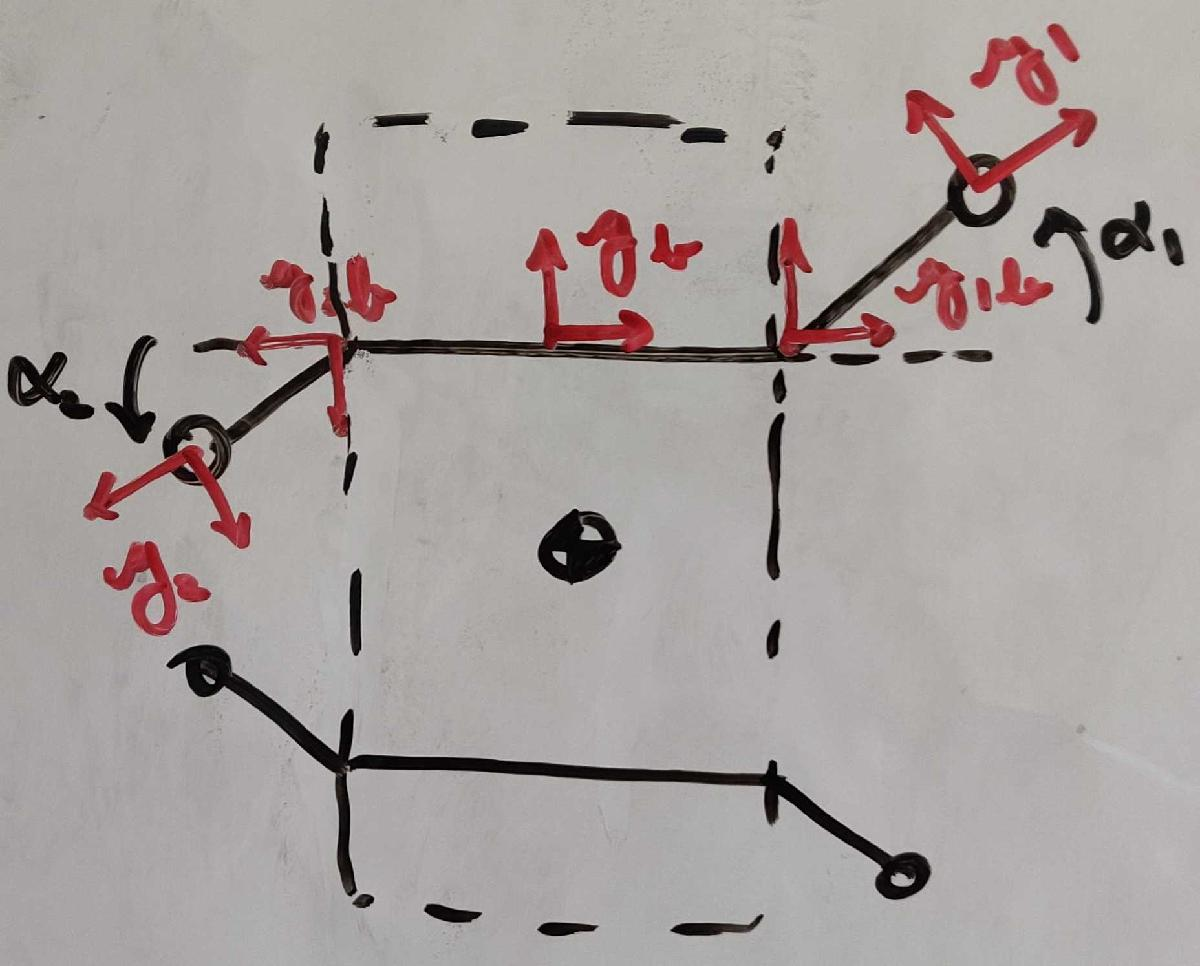

**EDIT 2023/05/02:**** Added a HAMR 6 flag and parameters to compute the 2D kinematics of HAMR 6. Also added a flag for CLARI robot.**

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = true;  %%%%% SET HERE                         % true  -- if you want to use the parameters of HAMR 6
                                                         % false -- if you want to use the standard symmetric quadruped parameters

addpath 'Utility Functions'\;
syms x y theta u v beta real
% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % %
% % % % % % % % % % now, we have a function under utilities that achieves the same thing
% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 
% % % % % v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
% % % % %                 sin(v(3)),  cos(v(3)), v(2);
% % % % %                         0,         0,    1];         %% fine to use symbolically or numerically

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);   % symbolically correct; don't use for numerics since it uses atan is restricted to -90 to +90
                                                      % USE "seqSE2transformation" function instead

L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); %%
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); %%

T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g); %%

g_vec = [x;
         y;
         theta]; %%
h_vec = [u;
         v;
         beta]; %%

g_mat = v2M_SE2(g_vec); %%

T_g_to_T_hg = T_gL_h(g_vec, h_vec); %%
T_g_to_T_gh = T_gR_h(g_vec, h_vec); %%

gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat); %%

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)])); %%
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta])); %%
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10); %%

theta_sel = [0,0,1]'; x_sel = [1,0,0]'; y_sel = [0,1,0]';

Now, let's make sure that the workspaces of the legs don't intersect each other. Make the lateral distance between the legs '2l', and the vertical distance between leg pairs 12 and 34 as also 2l; making the legs on the same side of the body not have intersecting workspaces and makes the body a square with the leg bases at each corner; note that the legs on the contra-lateral sides of the body have their workspaces mirrored like in any robotic system, **prioritizing forward motion**.

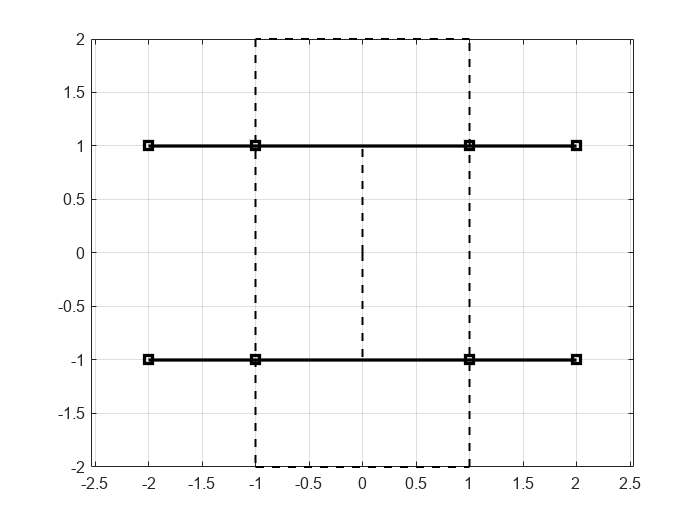

syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 real

% parameters for a symmetric quadruped
if hamr6_F % unpack measurements to obtain the kinematics of HAMR
        
    % CAD drawing measurements of the robot
    foot_bound = [[0, 34.74, 0]; [-35, 0, 0]; [0, -34.66, 0]; [35.626, 0, 0]]*rot_SE2(pi/2)'; % rotate by 90degs to make this inline with our 
    foot_bound = boundboxmean(foot_bound, true);
    hip_bound = [[0, 19.58, 0]; [-25.308, 0, 0]; [0, -19.58, 0]; [25.308, 0, 0]]*rot_SE2(pi/2)'; 
    hip_bound = boundboxmean(hip_bound, false);
    bodywoleg_bound = [[0, 19.58, 0]; [-45.37, 0, 0]; [0, -19.58, 0]; [45.37, 0, 0]]*rot_SE2(pi/2)'; 
    bodywoleg_bound = boundboxmean(bodywoleg_bound, false); bl = max(abs(bodywoleg_bound), [], 'all');
    hxy_b__ib = boundbox2ht3transform(hip_bound);
    hxy_b__i0 = boundbox2ht3transform(foot_bound); hxy_ib__i = hxy_b__i0 - hxy_b__ib; L = mean(vecnorm( hxy_ib__i, 2, 2)); % the length of the legs should be the same, and 'i0' stands for rest position of the i'th leg
    hxy_b__ic = boundbox2ht3transform(bodywoleg_bound);
    hxy_b__ib(1, 3) = 0; hxy_b__ib(2, 3) = pi; hxy_b__ib(3, 3) = pi; hxy_b__ib(4, 3) = 0;
    
    % obtain the constant that equals 'l' and 'a'
    hamr_l = min(abs(hxy_b__ib(:,1:2)), [], 'all'); % find the minimum length dimension in the hip bound box and make that 'l'
    hamr_a = L/hamr_l; % find the leg scaling factor 'a' that will give the correct leg length L and is in tune with the framework generated here

    % let's convert these measurments using l and a nomenclature used in this framework
    h_b__ib = [l*hxy_b__ib(:, 1:2)/hamr_l, hxy_b__ib(:, 3)];
    h_b__ic = [l*hxy_b__ic(:, 1:2)/hamr_l, hxy_b__ic(:, 3)];
    h_b__1c = h_b__ic(1, :)';
    h_b__2c = h_b__ic(2, :)';
    h_b__3c = h_b__ic(3, :)';
    h_b__4c = h_b__ic(4, :)';

    % other quantities we need for plotting etc
    h_b__12b = [0, h_b__ib(1, 2), 0]'; h_b__23b = [h_b__ib(2, 1), 0, 0]';
    h_b__34b = [0, h_b__ib(3, 2), 0]'; h_b__41b = [h_b__ib(1, 1), 0, 0]';

    h_12b__1b = h_b__ib(1,:)' - h_b__12b; % this kind of subtraction only works because ijb frames are only a translation away from body frame b
    h_12b__2b = h_b__ib(2,:)' - h_b__12b;
    h_23b__2b = h_b__ib(2,:)' - h_b__23b;
    h_23b__3b = h_b__ib(3,:)' - h_b__23b;
    h_34b__3b = h_b__ib(3,:)' - h_b__34b;
    h_34b__4b = h_b__ib(4,:)' - h_b__34b;
    h_41b__4b = h_b__ib(4,:)' - h_b__41b;
    h_41b__1b = h_b__ib(1,:)' - h_b__41b;
    
    % let's compute the foot related quantities
    syms alpha_i
    h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i]; % need to add the justification

else

    h_b__12b = [0, l, 0]';
    h_b__23b = [-l, 0, 0]';
    h_b__34b = [0, -l, 0]';
    h_b__41b = [l, 0, 0]';
    h_12b__1b = [l, 0, 0]';
    h_12b__2b = [-l, 0, pi]';
    h_23b__2b = [0, l, pi]';
    h_23b__3b = [0, -l, pi]';
    h_34b__3b = [-l, 0, pi]';
    h_34b__4b = [l, 0, 0]';
    h_41b__4b = [0, -l, 0]';
    h_41b__1b = [0, l, 0]';
    h_b__1c = [l,2*l,0]';
    h_b__2c = [-l,2*l,0]';
    h_b__3c = [-l,-2*l,0]';
    h_b__4c = [l,-2*l,0]';

    bl = 4*l;

    syms alpha_i
    h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i];
    % Jacobian to a leg from a different leg base will always be zero.

end

h_ib__i_func = matlabFunction(h_ib__i, 'Vars', [a, l, alpha_i]);
J_ib__i = AdjInvMap(h_ib__i);
J_ib__i_func = matlabFunction(J_ib__i, 'Vars', [a, l, alpha_i]);
J_ib__j_func = matlabFunction(zeros(3,3), 'Vars', [a, l, alpha_i]);

if hamr6_F
    datname = 'Data\HAMR6_SE2_kinematics.mat';
else
    datname = 'Data\case_1_kinematics.mat';
end
% if clari_F
%     datname = 'Data\CLARI_SE2_kinematics.mat';
% else
%     datname = 'Data\case_1_kinematics.mat';
% end

% Need to find a better, less repetitive way of doing this; the first
% thought would be to define loop iteration based strings and convert them
% to a variable name -- CHECK OUT "genvarname"
h_1b__1 = h_ib__i_func(a,l,alpha_1);
h_2b__2 = h_ib__i_func(a,l,alpha_2);
h_3b__3 = h_ib__i_func(a,l,alpha_3);
h_4b__4 = h_ib__i_func(a,l,alpha_4);

J_1b__1 = AdjInvMap(h_1b__1);
J_2b__2 = AdjInvMap(h_2b__2);
J_3b__3 = AdjInvMap(h_3b__3);
J_4b__4 = AdjInvMap(h_4b__4);

J_1b__2 = J_ib__j_func(a,l,alpha_1);
J_1b__3 = J_ib__j_func(a,l,alpha_1);
J_1b__4 = J_ib__j_func(a,l,alpha_1);

J_2b__1 = J_ib__j_func(a,l,alpha_2);
J_2b__3 = J_ib__j_func(a,l,alpha_2);
J_2b__4 = J_ib__j_func(a,l,alpha_2);

J_3b__1 = J_ib__j_func(a,l,alpha_3);
J_3b__2 = J_ib__j_func(a,l,alpha_3);
J_3b__4 = J_ib__j_func(a,l,alpha_3);

J_4b__1 = J_ib__j_func(a,l,alpha_4);
J_4b__2 = J_ib__j_func(a,l,alpha_4);
J_4b__3 = J_ib__j_func(a,l,alpha_4);

h_b__1b = seqSE2transformation([h_b__12b, h_12b__1b]);
h_b__2b = seqSE2transformation([h_b__12b, h_12b__2b]); 
h_b__3b = seqSE2transformation([h_b__34b, h_34b__3b]);
h_b__4b = seqSE2transformation([h_b__34b, h_34b__4b]);
h_b__1 = seqSE2transformation([h_b__12b, h_12b__1b, h_1b__1]);
h_b__2 = seqSE2transformation([h_b__12b, h_12b__2b, h_2b__2]); 
h_b__3 = seqSE2transformation([h_b__34b, h_34b__3b, h_3b__3]);
h_b__4 = seqSE2transformation([h_b__34b, h_34b__4b, h_4b__4]);

h_13b__1b = h_b__1b; h_13b__1b(3) = 0;
h_13b__3b = h_b__3b; h_13b__3b(3) = pi;
h_24b__2b = h_b__2b; h_24b__2b(3) = pi;
h_24b__4b = h_b__4b; h_24b__4b(3) = 0;

J_b__1 = AdjInvMap(h_b__1);
J_b__2 = AdjInvMap(h_b__2);
J_b__3 = AdjInvMap(h_b__3);
J_b__4 = AdjInvMap(h_b__4);

% Get the full Jacobian:
J_1_full = [J_b__1,...
    J_1b__1*theta_sel, J_2b__1*theta_sel, J_3b__1*theta_sel, J_4b__1*theta_sel];
J_2_full = [J_b__2,...
    J_1b__2*theta_sel, J_2b__2*theta_sel, J_3b__2*theta_sel, J_4b__2*theta_sel];
J_3_full = [J_b__3,...
    J_1b__3*theta_sel, J_2b__3*theta_sel, J_3b__3*theta_sel, J_4b__3*theta_sel];
J_4_full = [J_b__4,...
    J_1b__4*theta_sel, J_2b__4*theta_sel, J_3b__4*theta_sel, J_4b__4*theta_sel];

% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % TRANSFORM VALIDAITON COMPLETE
% Let's plot the robot and convince ourselves that the transforms are
% right.
if ~hamr6_F
    ll = 1; aa = 1;
else
    ll = hamr_l; aa = hamr_a;
end
topright2topleft_x = [h_b__1c(1) h_b__2c(1)]; topright2topleft_y = [h_b__1c(2) h_b__2c(2)];
topleft2botleft_x = [h_b__2c(1) h_b__3c(1)]; topleft2botleft_y = [h_b__2c(2) h_b__3c(2)];
botleft2botright_x = [h_b__3c(1) h_b__4c(1)]; botleft2botright_y = [h_b__3c(2) h_b__4c(2)];
botright2topright_x = [h_b__4c(1) h_b__1c(1)]; botright2topright_y = [h_b__4c(2) h_b__1c(2)];

base_topbase_x = [0 h_b__12b(1)]; base_topbase_y = [0 h_b__12b(2)];
base_botbase_x = [0 h_b__34b(1)]; base_botbase_y = [0 h_b__34b(2)];

topbase_leg1base_x = [h_b__12b(1) h_b__1b(1)]; topbase_leg1base_y = [h_b__12b(2) h_b__1b(2)];
topbase_leg2base_x = [h_b__12b(1) h_b__2b(1)]; topbase_leg2base_y = [h_b__12b(2) h_b__2b(2)];

botbase_leg3base_x = [h_b__34b(1) h_b__3b(1)]; botbase_leg3base_y = [h_b__34b(2) h_b__3b(2)];
botbase_leg4base_x = [h_b__34b(1) h_b__4b(1)]; botbase_leg4base_y = [h_b__34b(2) h_b__4b(2)];

legbase1_leg1_x =  [h_b__1b(1) h_b__1(1)]; legbase1_leg1_y =  [h_b__1b(2) h_b__1(2)];
legbase2_leg2_x =  [h_b__2b(1) h_b__2(1)]; legbase2_leg2_y =  [h_b__2b(2) h_b__2(2)];
legbase3_leg3_x =  [h_b__3b(1) h_b__3(1)]; legbase3_leg3_y =  [h_b__3b(2) h_b__3(2)];
legbase4_leg4_x =  [h_b__4b(1) h_b__4(1)]; legbase4_leg4_y =  [h_b__4b(2) h_b__4(2)];

base_topbase_x = double(subs(base_topbase_x,l,ll)); base_topbase_y = double(subs(base_topbase_y,l,ll));
base_botbase_x = double(subs(base_botbase_x,l,ll)); base_botbase_y = double(subs(base_botbase_y,l,ll));

topright2topleft_x = double(subs(topright2topleft_x,l,ll)); topright2topleft_y = double(subs(topright2topleft_y,l,ll));
topleft2botleft_x = double(subs(topleft2botleft_x,l,ll)); topleft2botleft_y = double(subs(topleft2botleft_y,l,ll));
botleft2botright_x = double(subs(botleft2botright_x,l,ll)); botleft2botright_y = double(subs(botleft2botright_y,l,ll));
botright2topright_x = double(subs(botright2topright_x,l,ll)); botright2topright_y = double(subs(botright2topright_y,l,ll));

topbase_leg1base_x = double(subs(topbase_leg1base_x,l,ll)); topbase_leg1base_y = double(subs(topbase_leg1base_y,l,ll));
topbase_leg2base_x = double(subs(topbase_leg2base_x,l,ll)); topbase_leg2base_y = double(subs(topbase_leg2base_y,l,ll));

botbase_leg3base_x = double(subs(botbase_leg3base_x,l,ll)); botbase_leg3base_y = double(subs(botbase_leg3base_y,l,ll));
botbase_leg4base_x = double(subs(botbase_leg4base_x,l,ll)); botbase_leg4base_y = double(subs(botbase_leg4base_y,l,ll));

legbase1_leg1_x =  double(subs(legbase1_leg1_x,[a,l,alpha_1],[aa,ll,0])); legbase1_leg1_y = double(subs(legbase1_leg1_y,[a,l,alpha_1],[aa,ll,0]));
legbase2_leg2_x =  double(subs(legbase2_leg2_x,[a,l,alpha_2],[aa,ll,0])); legbase2_leg2_y = double(subs(legbase2_leg2_y,[a,l,alpha_2],[aa,ll,0]));
legbase3_leg3_x =  double(subs(legbase3_leg3_x,[a,l,alpha_3],[aa,ll,0])); legbase3_leg3_y = double(subs(legbase3_leg3_y,[a,l,alpha_3],[aa,ll,0]));
legbase4_leg4_x =  double(subs(legbase4_leg4_x,[a,l,alpha_4],[aa,ll,0])); legbase4_leg4_y = double(subs(legbase4_leg4_y,[a,l,alpha_4],[aa,ll,0]));

figure()

plot(base_topbase_x,base_topbase_y,'k--','LineWidth',1.2);
hold on; grid on;  axis equal;
plot(base_botbase_x,base_botbase_y,'k--','LineWidth',1.2);
plot(topbase_leg1base_x,topbase_leg1base_y,'k','LineWidth',2.0);
plot(topbase_leg2base_x,topbase_leg2base_y,'k','LineWidth',2.0);
plot(botbase_leg3base_x,botbase_leg3base_y,'k','LineWidth',2.0);
plot(botbase_leg4base_x,botbase_leg4base_y,'k','LineWidth',2.0);
plot(topright2topleft_x,topright2topleft_y,'k--','LineWidth',1.2);
plot(topleft2botleft_x,topleft2botleft_y,'k--','LineWidth',1.2);
plot(botleft2botright_x,botleft2botright_y,'k--','LineWidth',1.2);
plot(botright2topright_x,botright2topright_y,'k--','LineWidth',1.2);
plot(legbase1_leg1_x,legbase1_leg1_y,'ks-','LineWidth',2.0);
plot(legbase2_leg2_x,legbase2_leg2_y,'ks-','LineWidth',2.0);
plot(legbase3_leg3_x,legbase3_leg3_y,'ks-','LineWidth',2.0);
plot(legbase4_leg4_x,legbase4_leg4_y,'ks-','LineWidth',2.0);

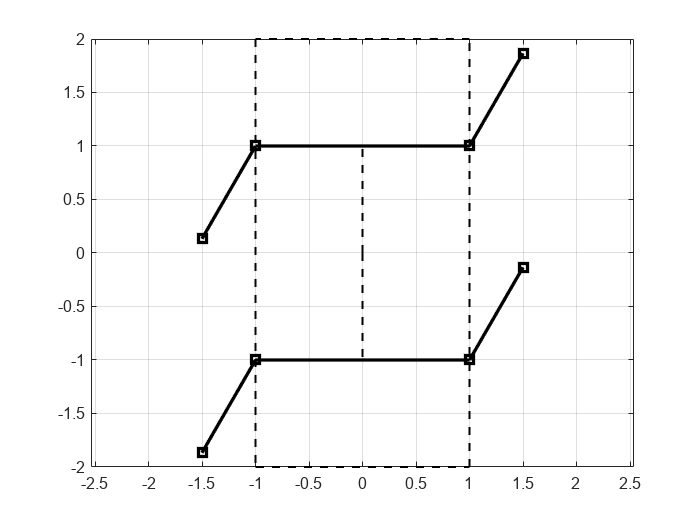

drawnow();

legbase1_leg1_x =  [h_b__1b(1) h_b__1(1)]; legbase1_leg1_y =  [h_b__1b(2) h_b__1(2)];
legbase2_leg2_x =  [h_b__2b(1) h_b__2(1)]; legbase2_leg2_y =  [h_b__2b(2) h_b__2(2)];
legbase3_leg3_x =  [h_b__3b(1) h_b__3(1)]; legbase3_leg3_y =  [h_b__3b(2) h_b__3(2)];
legbase4_leg4_x =  [h_b__4b(1) h_b__4(1)]; legbase4_leg4_y =  [h_b__4b(2) h_b__4(2)];
legbase1_leg1_x =  double(subs(legbase1_leg1_x,[a,l,alpha_1],[aa,ll,pi/3])); legbase1_leg1_y = double(subs(legbase1_leg1_y,[a,l,alpha_1],[aa,ll,pi/3]));
legbase2_leg2_x =  double(subs(legbase2_leg2_x,[a,l,alpha_2],[aa,ll,pi/3])); legbase2_leg2_y = double(subs(legbase2_leg2_y,[a,l,alpha_2],[aa,ll,pi/3]));
legbase3_leg3_x =  double(subs(legbase3_leg3_x,[a,l,alpha_3],[aa,ll,pi/3])); legbase3_leg3_y = double(subs(legbase3_leg3_y,[a,l,alpha_3],[aa,ll,pi/3]));
legbase4_leg4_x =  double(subs(legbase4_leg4_x,[a,l,alpha_4],[aa,ll,pi/3])); legbase4_leg4_y = double(subs(legbase4_leg4_y,[a,l,alpha_4],[aa,ll,pi/3]));
figure()
plot(base_topbase_x,base_topbase_y,'k--','LineWidth',1.2);
hold on; grid on; axis equal;
plot(base_botbase_x,base_botbase_y,'k--','LineWidth',1.2);
plot(topbase_leg1base_x,topbase_leg1base_y,'k','LineWidth',2.0);
plot(topbase_leg2base_x,topbase_leg2base_y,'k','LineWidth',2.0);
plot(botbase_leg3base_x,botbase_leg3base_y,'k','LineWidth',2.0);
plot(botbase_leg4base_x,botbase_leg4base_y,'k','LineWidth',2.0);
plot(topright2topleft_x,topright2topleft_y,'k--','LineWidth',1.2);
plot(topleft2botleft_x,topleft2botleft_y,'k--','LineWidth',1.2);
plot(botleft2botright_x,botleft2botright_y,'k--','LineWidth',1.2);
plot(botright2topright_x,botright2topright_y,'k--','LineWidth',1.2);
plot(topright2topleft_x,topright2topleft_y,'k--','LineWidth',1.2);
plot(topleft2botleft_x,topleft2botleft_y,'k--','LineWidth',1.2);
plot(botleft2botright_x,botleft2botright_y,'k--','LineWidth',1.2);
plot(botright2topright_x,botright2topright_y,'k--','LineWidth',1.2);
plot(legbase1_leg1_x,legbase1_leg1_y,'ks-','LineWidth',2.0);
plot(legbase2_leg2_x,legbase2_leg2_y,'ks-','LineWidth',2.0);
plot(legbase3_leg3_x,legbase3_leg3_y,'ks-','LineWidth',2.0);
plot(legbase4_leg4_x,legbase4_leg4_y,'ks-','LineWidth',2.0);

drawnow();

Let's check the connections now.

C = [eye(2,2),zeros(2,1)];

J_1 = C*J_1_full;
J_2 = C*J_2_full;
J_3 = C*J_3_full;
J_4 = C*J_4_full;

pfaff_12 = [C*J_1_full;
            C*J_2_full];
pfaff_23 = [C*J_2_full;
            C*J_3_full];
pfaff_34 = [C*J_3_full;
            C*J_4_full];
pfaff_41 = [C*J_4_full;
            C*J_1_full];
pfaff_13 = [C*J_1_full;
            C*J_3_full];
pfaff_24 = [C*J_2_full;
            C*J_4_full];

% Compute the local connection for the 12 submanifold -- just gives inf
% % simplify(pfaff_12(:,1:3)\pfaff_12(:,4:end),'Steps',10)
% % simplify(pfaff_23(:,1:3)\pfaff_23(:,4:end),'Steps',10)
% % simplify(pfaff_34(:,1:3)\pfaff_34(:,4:end),'Steps',10)
% % simplify(pfaff_41(:,1:3)\pfaff_41(:,4:end),'Steps',10)
% % simplify(pfaff_13(:,1:3)\pfaff_13(:,4:end),'Steps',10)
% % simplify(pfaff_24(:,1:3)\pfaff_24(:,4:end),'Steps',10)

Since, no connection exists, let us look at the formulation for squared inter-leg distance to glean some insight into why this is the case.

ksq_12 = simplify((C*(h_b__2 - h_b__1))'*C*(h_b__2 - h_b__1),'Steps',10)

$$ksq\_12 = l^{2}\,{\left(a\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{2}\right)+2\right)}^{2}+a^{2}\,l^{2}\,{\left(\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{2}\right)\right)}^{2}$$

dksq_12_i = simplify(diff(ksq_12, alpha_1), 'Steps', 10)

$$dksq\_12\_i = -2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)$$

dksq_12_j = simplify(diff(ksq_12, alpha_2), 'Steps', 10)

$$dksq\_12\_j = -2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{2}\right)-a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)$$

ksq_23 = simplify((C*(h_b__3 - h_b__2))'*C*(h_b__3 - h_b__2),'Steps',10)

$$ksq\_23 = l^{2}\,{\left(a\,\sin\left(\alpha_{3}\right)-a\,\sin\left(\alpha_{2}\right)+2\right)}^{2}+a^{2}\,l^{2}\,{\left(\cos\left(\alpha_{2}\right)-\cos\left(\alpha_{3}\right)\right)}^{2}$$

dksq_23_i = simplify(diff(ksq_23, alpha_2), 'Steps', 10)

$$dksq\_23\_i = -2\,a\,l^{2}\,\left(2\,\cos\left(\alpha_{2}\right)-a\,\sin\left(\alpha_{2}-\alpha_{3}\right)\right)$$

dksq_23_j = simplify(diff(ksq_23, alpha_3), 'Steps', 10)

$$dksq\_23\_j = 2\,a\,l^{2}\,\left(2\,\cos\left(\alpha_{3}\right)-a\,\sin\left(\alpha_{2}-\alpha_{3}\right)\right)$$

ksq_34 = simplify((C*(h_b__4 - h_b__3))'*C*(h_b__4 - h_b__3),'Steps',10)

$$ksq\_34 = l^{2}\,{\left(a\,\cos\left(\alpha_{3}\right)+a\,\cos\left(\alpha_{4}\right)+2\right)}^{2}+a^{2}\,l^{2}\,{\left(\sin\left(\alpha_{3}\right)+\sin\left(\alpha_{4}\right)\right)}^{2}$$

dksq_34_i = simplify(diff(ksq_34, alpha_3), 'Steps', 10)

$$dksq\_34\_i = -2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{3}\right)+a\,\sin\left(\alpha_{3}-\alpha_{4}\right)\right)$$

dksq_34_j = simplify(diff(ksq_34, alpha_4), 'Steps', 10)

$$dksq\_34\_j = -2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{4}\right)-a\,\sin\left(\alpha_{3}-\alpha_{4}\right)\right)$$

ksq_41 = simplify((C*(h_b__1 - h_b__4))'*C*(h_b__1 - h_b__4),'Steps',10)

$$ksq\_41 = l^{2}\,{\left(a\,\sin\left(\alpha_{1}\right)-a\,\sin\left(\alpha_{4}\right)+2\right)}^{2}+a^{2}\,l^{2}\,{\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{4}\right)\right)}^{2}$$

dksq_41_i = simplify(diff(ksq_41, alpha_4), 'Steps', 10)

$$dksq\_41\_i = -2\,a\,l^{2}\,\left(2\,\cos\left(\alpha_{4}\right)+a\,\sin\left(\alpha_{1}-\alpha_{4}\right)\right)$$

dksq_41_j = simplify(diff(ksq_41, alpha_1), 'Steps', 10)

$$dksq\_41\_j = 2\,a\,l^{2}\,\left(2\,\cos\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{4}\right)\right)$$

ksq_13 = simplify((C*(h_b__3 - h_b__1))'*C*(h_b__3 - h_b__1),'Steps',10)

$$ksq\_13 = l^{2}\,{\left(a\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{3}\right)+2\right)}^{2}+l^{2}\,{\left(a\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{3}\right)+2\right)}^{2}$$

dksq_13_i = simplify(diff(ksq_13, alpha_1), 'Steps', 10)

$$dksq\_13\_i = 2\,a\,l^{2}\,\left(2\,\sqrt{2}\,\cos\left(\alpha_{1}+\frac{\pi }{4}\right)-a\,\sin\left(\alpha_{1}-\alpha_{3}\right)\right)$$

dksq_13_j = simplify(diff(ksq_13, alpha_3), 'Steps', 10)

$$dksq\_13\_j = 2\,a\,l^{2}\,\left(2\,\sqrt{2}\,\cos\left(\alpha_{3}+\frac{\pi }{4}\right)+a\,\sin\left(\alpha_{1}-\alpha_{3}\right)\right)$$

ksq_24 = simplify((C*(h_b__4 - h_b__2))'*C*(h_b__4 - h_b__2),'Steps',10)

$$ksq\_24 = l^{2}\,{\left(a\,\sin\left(\alpha_{2}\right)+a\,\sin\left(\alpha_{4}\right)-2\right)}^{2}+l^{2}\,{\left(a\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{4}\right)+2\right)}^{2}$$

dksq_24_i = simplify(diff(ksq_24, alpha_2), 'Steps', 10)

$$dksq\_24\_i = -2\,a\,l^{2}\,\left(2\,\sqrt{2}\,\sin\left(\alpha_{2}+\frac{\pi }{4}\right)+a\,\sin\left(\alpha_{2}-\alpha_{4}\right)\right)$$

dksq_24_j = simplify(diff(ksq_24, alpha_4), 'Steps', 10)

$$dksq\_24\_j = -2\,a\,l^{2}\,\left(2\,\sqrt{2}\,\sin\left(\alpha_{4}+\frac{\pi }{4}\right)-a\,\sin\left(\alpha_{2}-\alpha_{4}\right)\right)$$

ksq_12_func = matlabFunction(ksq_12,'Vars',[a, l, alpha_1, alpha_2]);

Let's just plot this as a function of the shape space in the form of a heat-map to see if there are tractable connection regions.

dnum = 100;

aa = 1;                                 
ll = 1;                                 

ank = pi/4;                    

xx = linspace(-ank,ank,dnum);          
yy = xx;

[a1,a2] = meshgrid(xx,yy);

ksq_sweep = ksq_12_func(aa, ll, a1, a2);
ksq_M = ksq_12_func(aa, ll, xx, yy);
ksq_m = ksq_12_func(aa, ll, xx, -yy);
ksq_x = ksq_12_func(aa, ll, xx, 0*yy);
ksq_y = ksq_12_func(aa, ll, 0*xx, yy);

% Plot the inter-leg distance landscape
figure('units','pixels','position',[0 0 1920 1080],'Color','w')
surf(a1,a2,ksq_sweep,'EdgeColor','none'); % ,'EdgeColor','none'
axis equal tight; hold on; view(2);
colormap(turbo); % use this colormap
colorbar(); % show the colorbar
line(xx,yy,ksq_M,'Color','k','LineStyle','-'); % major axis % ,'LineWidth',1.2
line(xx,-yy,ksq_m,'Color','k','LineStyle','--');% minor axis % ,'LineWidth',1.2
line(0*xx,yy,ksq_y,'Color','k','LineStyle',':');% alpha_j axis % ,'LineWidth',1.2
line(xx,0*yy,ksq_x,'Color','k','LineStyle',':');% alpha_i-axis % ,'LineWidth',1.2
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
title('$k^2_{12}$','Interpreter','latex',FontSize=20);

Seems like the inter-leg distance is definitely changing as we move along any direction, but there are level-set contours that from a loop in the shape space. This should be the same for all leg pairs. Hence, to expand our shape-space, let's try adding compliance through a contra-laterally symmetric, closed kinematic chain -- half a sarrus linkage! **Disclaimer: **You also need to add an out of plane chain to constrain the robot shape...

Also, the pseudo-inverse should work, let's do some additional digging.

### Overconstrained, inconsistent 4x3 subblock

Adding some analysis on the pseudoinverse of the overconstrained 4x3 sub-block (from the left) which happens to be inconsistent.

s_12 = pfaff_12(:,1:3) 

$$s\_12 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & -\sqrt{2}\,l\,\cos\left(\alpha_{1}+\frac{\pi }{4}\right)\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right)\\ -\cos\left(\alpha_{2}\right) & -\sin\left(\alpha_{2}\right) & \sqrt{2}\,l\,\sin\left(\alpha_{2}+\frac{\pi }{4}\right)\\ \sin\left(\alpha_{2}\right) & -\cos\left(\alpha_{2}\right) & l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)\right) \end{array}\right)$$

s_23 = pfaff_23(:,1:3)

$$s\_23 = \left(\begin{array}{ccc} -\cos\left(\alpha_{2}\right) & -\sin\left(\alpha_{2}\right) & \sqrt{2}\,l\,\sin\left(\alpha_{2}+\frac{\pi }{4}\right)\\ \sin\left(\alpha_{2}\right) & -\cos\left(\alpha_{2}\right) & l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)\right)\\ -\cos\left(\alpha_{3}\right) & -\sin\left(\alpha_{3}\right) & -\sqrt{2}\,l\,\cos\left(\alpha_{3}+\frac{\pi }{4}\right)\\ \sin\left(\alpha_{3}\right) & -\cos\left(\alpha_{3}\right) & l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{3}+\frac{\pi }{4}\right)\right) \end{array}\right)$$

s_34 = pfaff_34(:,1:3) 

$$s\_34 = \left(\begin{array}{ccc} -\cos\left(\alpha_{3}\right) & -\sin\left(\alpha_{3}\right) & -\sqrt{2}\,l\,\cos\left(\alpha_{3}+\frac{\pi }{4}\right)\\ \sin\left(\alpha_{3}\right) & -\cos\left(\alpha_{3}\right) & l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{3}+\frac{\pi }{4}\right)\right)\\ \cos\left(\alpha_{4}\right) & \sin\left(\alpha_{4}\right) & \sqrt{2}\,l\,\sin\left(\alpha_{4}+\frac{\pi }{4}\right)\\ -\sin\left(\alpha_{4}\right) & \cos\left(\alpha_{4}\right) & l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{4}+\frac{\pi }{4}\right)\right) \end{array}\right)$$

s_41 = pfaff_41(:,1:3) % adjacent legs

$$s\_41 = \left(\begin{array}{ccc} \cos\left(\alpha_{4}\right) & \sin\left(\alpha_{4}\right) & \sqrt{2}\,l\,\sin\left(\alpha_{4}+\frac{\pi }{4}\right)\\ -\sin\left(\alpha_{4}\right) & \cos\left(\alpha_{4}\right) & l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{4}+\frac{\pi }{4}\right)\right)\\ \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & -\sqrt{2}\,l\,\cos\left(\alpha_{1}+\frac{\pi }{4}\right)\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right) \end{array}\right)$$

s_13 = pfaff_13(:,1:3) 

$$s\_13 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & -\sqrt{2}\,l\,\cos\left(\alpha_{1}+\frac{\pi }{4}\right)\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right)\\ -\cos\left(\alpha_{3}\right) & -\sin\left(\alpha_{3}\right) & -\sqrt{2}\,l\,\cos\left(\alpha_{3}+\frac{\pi }{4}\right)\\ \sin\left(\alpha_{3}\right) & -\cos\left(\alpha_{3}\right) & l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{3}+\frac{\pi }{4}\right)\right) \end{array}\right)$$

s_24 = pfaff_24(:,1:3) % diagonally opposite legs

$$s\_24 = \left(\begin{array}{ccc} -\cos\left(\alpha_{2}\right) & -\sin\left(\alpha_{2}\right) & \sqrt{2}\,l\,\sin\left(\alpha_{2}+\frac{\pi }{4}\right)\\ \sin\left(\alpha_{2}\right) & -\cos\left(\alpha_{2}\right) & l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)\right)\\ \cos\left(\alpha_{4}\right) & \sin\left(\alpha_{4}\right) & \sqrt{2}\,l\,\sin\left(\alpha_{4}+\frac{\pi }{4}\right)\\ -\sin\left(\alpha_{4}\right) & \cos\left(\alpha_{4}\right) & l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{4}+\frac{\pi }{4}\right)\right) \end{array}\right)$$

As checked in the previous section, both '\' and pinv has failed us due to some symbolic engine issues; hence, we shall check if the sub-blocks are full column rank (needed to implement the inverse) and then implement a pseudoinverse (Moore-Penrose Inverse) manually.

% Let's check the column rank with rank command and also check the row
% reduced echelon form as proof:
rank(s_12)

ans = 3

rref(s_12)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ 0 & 0 & 0 \end{array}\right)$$

% Uncomment the functions below to obtain the approximated, least squares
% minimum local connection for this system.

The rank and echelon form reveal that the sub-block is full rank, but still the pinv and backlash command are causing issues for us. Let's make sure this is the case for all other contact submanifolds as well!

% rank(s_23)
% rref(s_23)
% rank(s_34)
% rref(s_34)
% rank(s_41)
% rref(s_41)
% rank(s_13)
% rref(s_13)
% rank(s_24)
% rref(s_24)
% % Uncomment above to verify the full column rank requirement to take the
% pseudoinverse.

They too work out! Now, we are good to take the pseudoinverse (and simplify the result)!

% s_12p = simplify(transpose(s_12)*s_12*transpose(s_12));
% s_23p = simplify(transpose(s_23)*s_23*transpose(s_23));
% s_34p = simplify(transpose(s_34)*s_34*transpose(s_34));
% s_41p = simplify(transpose(s_41)*s_41*transpose(s_41));
% s_13p = simplify(transpose(s_13)*s_13*transpose(s_13));
% s_24p = simplify(transpose(s_24)*s_24*transpose(s_24));

Get the approximate, least squares, local connection ${}^+\!\! A$ for each two-foot contact submanifold.

A_1_12 = simplify((transpose(s_12)*s_12)\transpose(s_12)*pfaff_12(:,4:end), 'Steps', 10)

A_1_23 = simplify((transpose(s_23)*s_23)\transpose(s_23)*pfaff_23(:,4:end), 'Steps', 10)

A_1_34 = simplify((transpose(s_34)*s_34)\transpose(s_34)*pfaff_34(:,4:end), 'Steps', 10)

A_1_41 = simplify((transpose(s_41)*s_41)\transpose(s_41)*pfaff_41(:,4:end), 'Steps', 10)

A_1_13 = simplify((transpose(s_13)*s_13)\transpose(s_13)*pfaff_13(:,4:end), 'Steps', 10)

A_1_24 = simplify((transpose(s_24)*s_24)\transpose(s_24)*pfaff_24(:,4:end), 'Steps', 10)

% UNCOMMENT BELOW IF YOU"VE MADE CHANGES to the the squared inter-leg
% distance or anything else.
% Save the data needed for the next section

if exist(datname,'file') == 2 % if the file already exists, just append

    if hamr6_F
        save(datname, 'C', 'hamr6_F', 'h_b__1b', 'h_b__2b', 'h_b__3b', 'h_b__4b',...
                        'h_b__12b','h_b__23b','h_b__34b','h_b__41b',...
                        'h_1b__1', 'h_2b__2', 'h_3b__3', 'h_4b__4', ...
                        'h_12b__1b', 'h_12b__2b', 'h_23b__2b', 'h_23b__3b',...
                        'h_34b__3b', 'h_34b__4b', 'h_41b__4b', 'h_41b__1b',...
                        'h_13b__1b', 'h_13b__3b', 'h_24b__2b', 'h_24b__4b',...
                        'h_b__1', 'h_b__2', 'h_b__3', 'h_b__4', ...
                        'h_b__1c','h_b__2c','h_b__3c','h_b__4c',...
                        'J_1_full', 'J_2_full', 'J_3_full', 'J_4_full',...
                        'J_1', 'J_2', 'J_3', 'J_4',...
                        'ksq_12','ksq_23','ksq_34','ksq_41','ksq_13','ksq_24',...
                        'dksq_12_i','dksq_12_j','dksq_23_i','dksq_23_j',...
                        'dksq_34_i','dksq_34_j','dksq_41_i','dksq_41_j',...
                        'dksq_13_i','dksq_13_j','dksq_24_i','dksq_24_j',...
                        'pfaff_12','pfaff_23','pfaff_34','pfaff_41','pfaff_13','pfaff_24',...
                        'A_1_12','A_1_23','A_1_34','A_1_41','A_1_13','A_1_24', 'hamr_l', 'hamr_a', 'bl',...
                        '-append');
    else
        save(datname, 'C', 'hamr6_F', 'h_b__1b', 'h_b__2b', 'h_b__3b', 'h_b__4b',...
                        'h_b__12b','h_b__23b','h_b__34b','h_b__41b',...
                        'h_1b__1', 'h_2b__2', 'h_3b__3', 'h_4b__4', ...
                        'h_12b__1b', 'h_12b__2b', 'h_23b__2b', 'h_23b__3b',...
                        'h_34b__3b', 'h_34b__4b', 'h_41b__4b', 'h_41b__1b',...
                        'h_13b__1b', 'h_13b__3b', 'h_24b__2b', 'h_24b__4b',...
                        'h_b__1', 'h_b__2', 'h_b__3', 'h_b__4', ...
                        'h_b__1c','h_b__2c','h_b__3c','h_b__4c',...
                        'J_1_full', 'J_2_full', 'J_3_full', 'J_4_full',...
                        'J_1', 'J_2', 'J_3', 'J_4',...
                        'ksq_12','ksq_23','ksq_34','ksq_41','ksq_13','ksq_24',...
                        'dksq_12_i','dksq_12_j','dksq_23_i','dksq_23_j',...
                        'dksq_34_i','dksq_34_j','dksq_41_i','dksq_41_j',...
                        'dksq_13_i','dksq_13_j','dksq_24_i','dksq_24_j',...
                        'pfaff_12','pfaff_23','pfaff_34','pfaff_41','pfaff_13','pfaff_24',...
                        'A_1_12','A_1_23','A_1_34','A_1_41','A_1_13','A_1_24', 'bl',...
                        '-append');
    end

else

    if hamr6_F
        save(datname, 'C', 'hamr6_F', 'h_b__1b', 'h_b__2b', 'h_b__3b', 'h_b__4b',...
                        'h_b__12b','h_b__23b','h_b__34b','h_b__41b',...
                        'h_1b__1', 'h_2b__2', 'h_3b__3', 'h_4b__4', ...
                        'h_12b__1b', 'h_12b__2b', 'h_23b__2b', 'h_23b__3b',...
                        'h_34b__3b', 'h_34b__4b', 'h_41b__4b', 'h_41b__1b',...
                        'h_13b__1b', 'h_13b__3b', 'h_24b__2b', 'h_24b__4b',...
                        'h_b__1', 'h_b__2', 'h_b__3', 'h_b__4', ...
                        'h_b__1c','h_b__2c','h_b__3c','h_b__4c',...
                        'J_1_full', 'J_2_full', 'J_3_full', 'J_4_full',...
                        'J_1', 'J_2', 'J_3', 'J_4',...
                        'ksq_12','ksq_23','ksq_34','ksq_41','ksq_13','ksq_24',...
                        'dksq_12_i','dksq_12_j','dksq_23_i','dksq_23_j',...
                        'dksq_34_i','dksq_34_j','dksq_41_i','dksq_41_j',...
                        'dksq_13_i','dksq_13_j','dksq_24_i','dksq_24_j',...
                        'pfaff_12','pfaff_23','pfaff_34','pfaff_41','pfaff_13','pfaff_24',...
                        'A_1_12','A_1_23','A_1_34','A_1_41','A_1_13','A_1_24', 'hamr_l', 'hamr_a', 'bl');
    else
        save(datname, 'C', 'hamr6_F', 'h_b__1b', 'h_b__2b', 'h_b__3b', 'h_b__4b',...
                        'h_b__12b','h_b__23b','h_b__34b','h_b__41b',...
                        'h_1b__1', 'h_2b__2', 'h_3b__3', 'h_4b__4', ...
                        'h_12b__1b', 'h_12b__2b', 'h_23b__2b', 'h_23b__3b',...
                        'h_34b__3b', 'h_34b__4b', 'h_41b__4b', 'h_41b__1b',...
                        'h_13b__1b', 'h_13b__3b', 'h_24b__2b', 'h_24b__4b',...
                        'h_b__1', 'h_b__2', 'h_b__3', 'h_b__4', ...
                        'h_b__1c','h_b__2c','h_b__3c','h_b__4c',...
                        'J_1_full', 'J_2_full', 'J_3_full', 'J_4_full',... 
                        'J_1', 'J_2', 'J_3', 'J_4',...
                        'ksq_12','ksq_23','ksq_34','ksq_41','ksq_13','ksq_24',...
                        'dksq_12_i','dksq_12_j','dksq_23_i','dksq_23_j',...
                        'dksq_34_i','dksq_34_j','dksq_41_i','dksq_41_j',...
                        'dksq_13_i','dksq_13_j','dksq_24_i','dksq_24_j',...
                        'pfaff_12','pfaff_23','pfaff_34','pfaff_41','pfaff_13','pfaff_24',...
                        'A_1_12','A_1_23','A_1_34','A_1_41','A_1_13','A_1_24', 'bl');
    end

end

% Clear everything after writing information
clear all; close all; clc;

Save the above SE(2) kinematics data into HAMR robot data file.

% check if we are doing the HAMR case
hamr6_F = true;
if hamr6_F
    datname = 'Data\HAMR6_SE2_kinematics.mat';
else
    datname = 'Data\case_1_kinematics.mat';
end

% Load the data from the previous section:
addpath 'Live Scripts'\ Data\ 'Utility Functions'\;
load(datname);
if exist('Data\HAMR6_SE3_kinematics.mat','file') == 2
    load('Data\HAMR6_SE3_kinematics.mat');
end
syms a l x y theta alpha_1 alpha_2 alpha_3 alpha_4 real
fh2_e__b = matlabFunction([x, y, theta]', 'Vars', [x, y, theta]); %
fh2_b__1b = matlabFunction(h_b__1b, 'Vars', l);
fh2_b__2b = matlabFunction(h_b__2b, 'Vars', l);
fh2_b__3b = matlabFunction(h_b__3b, 'Vars', l);
fh2_b__4b = matlabFunction(h_b__4b, 'Vars', l);
fh2_b__ib = {fh2_b__1b, fh2_b__2b, fh2_b__3b, fh2_b__4b}; %
fh2_b__1c = matlabFunction(h_b__1c, 'Vars', l);
fh2_b__2c = matlabFunction(h_b__2c, 'Vars', l);
fh2_b__3c = matlabFunction(h_b__3c, 'Vars', l);
fh2_b__4c = matlabFunction(h_b__4c, 'Vars', l);
fh2_b__ic = {fh2_b__1c, fh2_b__2c, fh2_b__3c, fh2_b__4c}; %
fh2_1b__1 = matlabFunction(h_1b__1, 'Vars', [a l alpha_1]);
fh2_2b__2 = matlabFunction(h_2b__2, 'Vars', [a l alpha_2]);
fh2_3b__3 = matlabFunction(h_3b__3, 'Vars', [a l alpha_3]);
fh2_4b__4 = matlabFunction(h_4b__4, 'Vars', [a l alpha_4]);
fh2_ib__i = {fh2_1b__1, fh2_2b__2, fh2_3b__3, fh2_4b__4}; %
fh2_b__1 = matlabFunction(h_b__1, 'Vars', [a l alpha_1]);
fh2_b__2 = matlabFunction(h_b__2, 'Vars', [a l alpha_2]);
fh2_b__3 = matlabFunction(h_b__3, 'Vars', [a l alpha_3]);
fh2_b__4 = matlabFunction(h_b__4, 'Vars', [a l alpha_4]);
fh2_b__i = {fh2_b__1, fh2_b__2, fh2_b__3, fh2_b__4}; %
HAMR_6.SE2.transforms.fun.fh2_e__b = fh2_e__b;
HAMR_6.SE2.transforms.fun.fh2_b__ib = fh2_b__ib;
HAMR_6.SE2.transforms.fun.fh2_b__ic = fh2_b__ic;
HAMR_6.SE2.transforms.fun.fh2_ib__i = fh2_ib__i;
HAMR_6.SE2.transforms.fun.fh2_b__i = fh2_b__i;
HAMR_6.SE2.params.bl = HAMR_6.SE3.params.bl; % copy-over bodylength value
HAMR_6.SE2.params.aa = hamr_a;
HAMR_6.SE2.params.ll = hamr_l;
save('Data\HAMR6_SE3_kinematics.mat','HAMR_6','-append');
save(datname, 'fh2_e__b', 'fh2_b__ib', 'fh2_b__ic', 'fh2_ib__i', 'fh2_b__i', '-append');

## Motion Planning

### Designing gaits based on the inter-leg distance constraints (for legs 1 and 2)

Recall that two legs are pinned and hence, the distance between them is conserved (doesn't change with time) - check the $k^2$ plot above. In order to remain in the level-sets of $k^2$, we need to obtain this relationship between the two legs pinned to the ground. On a quick look, the major and minor axis of the ellipsoidal gait that satisfies the $k^2$ level set conditions are $\alpha_i =\alpha_j$ and $\alpha_i =-\alpha_j$. Let's obtain the exact relationship below by taking the gradient of $k^2$.


$$\frac{d k^2 (\alpha_i, \alpha_j)}{dt} = \frac{\partial k^2}{\partial \alpha_i} \dot{\alpha_i} + \frac{\partial k^2}{\partial \alpha_j} \dot{\alpha_j} = 0, \\
\dot{\alpha_j} = -  \frac{\partial k^2}{\partial \alpha_i}  \biggl( \frac{\partial k^2}{\partial \alpha_j} \biggr)^{-1} \dot{\alpha_i}$$


We can simplify this further by removing the time-dependence,


$$\frac{\partial{\alpha_j}}{\partial{\alpha_i}} = -  \frac{\partial k^2}{\partial \alpha_i}  \biggl( \frac{\partial k^2}{\partial \alpha_j} \biggr)^{-1}$$


But, since we have ellipsoidal level-sets (need to find a way to prove this later!), we can rotate the gradient by $\pm90^{\circ}$ to get a CCW or CW gait. This is the gradient for $k^2$ surface,


$$$\nabla k^2 = \left(\begin{array}{c}
\frac{\partial k^2}{\partial \alpha_i} \\
\frac{\partial k^2}{\partial \alpha_j}
\end{array}\right)$$$


The derivative in the shape-space for the iso-$k^2$ surface with a CCW gait is given by,


$$d\hat{\psi}_{ij} = R{\left(\frac{\pi}{2}\right)} . \nabla k^2 \,\,\, \\
\Rightarrow d\hat{\psi}_{ij} = \left(\begin{array}{c c}
0 & 1 \\
-1 & 0
\end{array}\right) 
\left(\begin{array}{c}
\frac{\partial k^2}{\partial \alpha_i} \\
\frac{\partial k^2}{\partial \alpha_j}
\end{array}\right)$$


Let's compute these CCW +ve and CW -ve gait derivates, and plot some on the iso-$k^2$ surface for $S_{12}$,

hamr6_F = true;
if hamr6_F
    datname = 'Data\HAMR6_SE2_kinematics.mat';
else
    datname = 'Data\case_1_kinematics.mat';
end
addpath 'Live Scripts'\ Data\ 'Utility Functions'\;
load(datname);

% Reinitialize some symbols
syms a l real positive
assume(a<=1);
syms tau real
syms alpha_1 alpha_2 theta real % alpha_3 alpha_4

% Define a rotation matrix for the two dimensional shape-space slice
% rotations
rot_in_ij = [cos(theta), -sin(theta);
            sin(theta), cos(theta)];
rot_in_ij = matlabFunction(rot_in_ij, 'Vars', theta);
% MAKE SURE TO ROUND THE RESULTS

% Gradient for 12 contact state Ksq
dpsi_12 = simplify(round(rot_in_ij(pi/2))*[diff(ksq_12,alpha_1) diff(ksq_12,alpha_2)]','Steps',10)

$$dpsi\_12 = \left(\begin{array}{c} 2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{2}\right)-a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)\\ -2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right) \end{array}\right)$$

Next, we need to know if we are coming back to the starting position in our gait, and this can be defined based on the phase between our starting point and the origin. Hence, based on this phase, we can define our gait constraints.

% Let's consider the S12 contact state and obtain the gait constraints for
% the same----------------------------------------------------------------
% Squared inter-leg distance function
ksq_12_func = matlabFunction(ksq_12,'Vars',[tau, a, l, alpha_1, alpha_2]);
% 2-element shape slice derivatives for the iso-k^2 level-sets
dpsi_12_func = matlabFunction(dpsi_12,'Vars',[tau, a, l, alpha_1, alpha_2]);

% Initialize standard parameters
if hamr6_F
    aa = hamr_a;                                 
    ll = hamr_l;  
else
    aa = 1;                                 
    ll = 1;
end
ank = pi/4;

% Define the initial conditions for the gait, since we are using atan2, we
% should start from -pi to pi. Hence, the initial condition for the ode
% integration is chosen such that the phase is 0 at the beginning => a1
% is positive and a2 = 0.
a1_0 = 0.1*2*ank; % 20% of the allowble swing range of leg 1
a2_0 = 0; % to make the phase -pi

% ode45 options
options = odeset('Events',@PhaseSijTrigger);
% Let's compute this constrained gait using ode45 -------------------------
% the time span is set between 0 and 5 since we don't know when it is going
% to end.
[t,y,te,ye,ie] = ode45( @(t,y) dpsi_12_func(t, aa, ll, y(1), y(2)), [0 5], [a1_0; a2_0], options );

Alright! Now, that we have computed this, let's plot this to see who it looks.

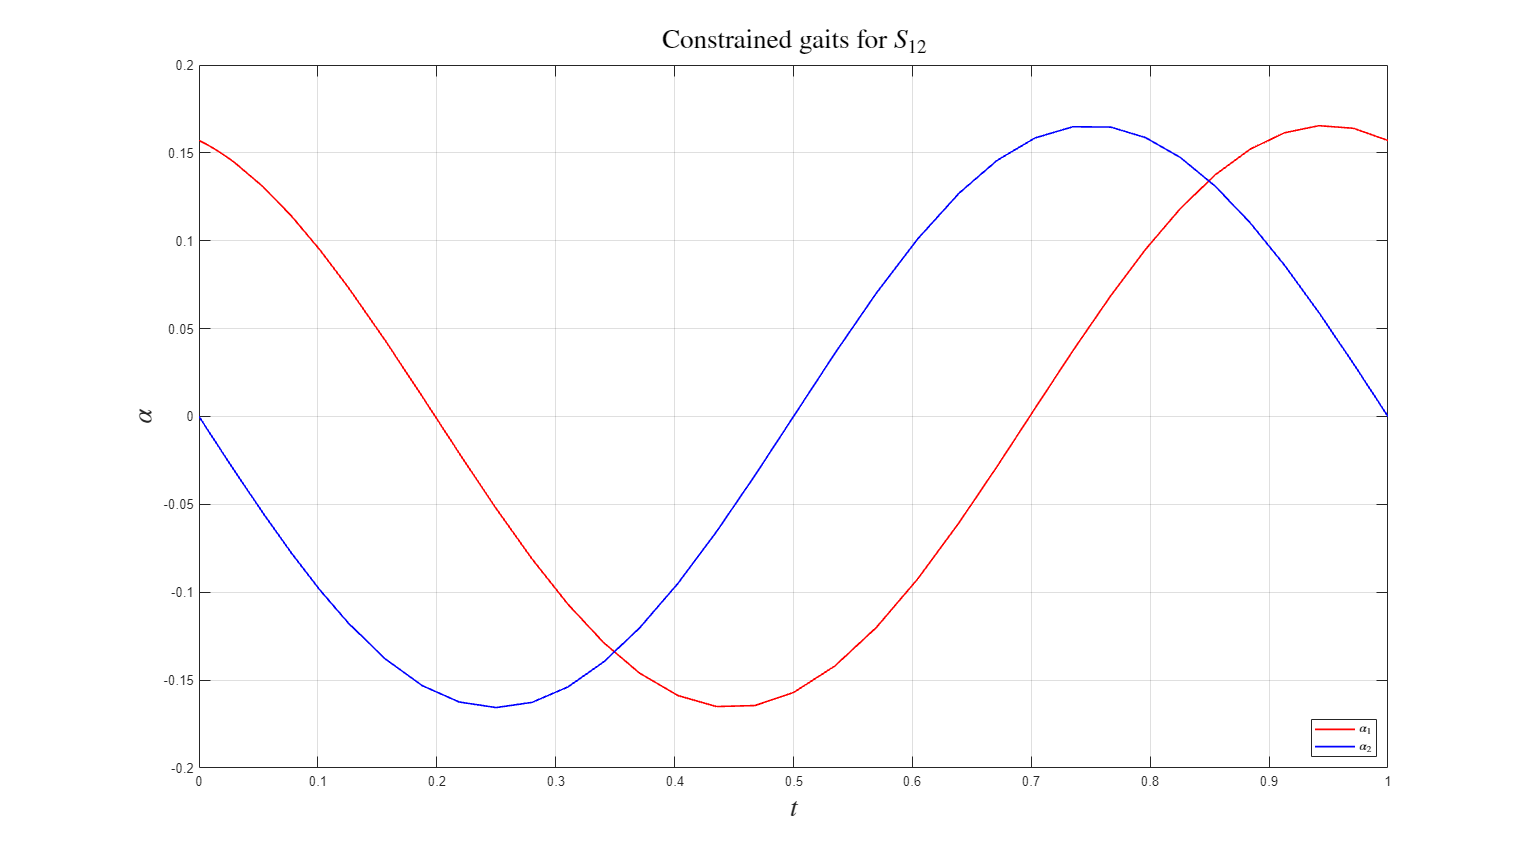

% Rescale the time vectors to end at 1 for the cycle
t = t/t(end); te = te/t(end);
% Plot the computed leg swings
figure('units','pixels','position',[0 0 1920 1080],'Color','w')
plot(t, y(:,1), 'r', 'linewidth', 1.2,'DisplayName','$\alpha_1$'); % alpha_1
hold on; grid on;
plot(t, y(:,2), 'b', 'linewidth', 1.2,'DisplayName','$\alpha_2$'); % alpha_2
% plot(te,ye,'ko','DisplayName','event trigger'); % plot the event trigger point
xlabel('$t$','Interpreter','latex',FontSize=20);
ylabel('$\alpha$','Interpreter','latex',FontSize=20);
title('Constrained gaits for $S_{12}$','Interpreter','latex',FontSize=20);
legend('location','southeast','Interpreter','latex',FontSize=10);

This is great! But, note that this is a numerical approximation and in order to find the **fixed phase between the shape elements**, let's do a sinusoidal fit as shown below,


$$s_1\sin{\left(2 \pi \left(t + \frac{1}{s_2} \right) \right)} + s_3 \\
s_1: \text{amplitude} \\
\frac{2 \pi}{s_2}: \text{phase offset} \\
s_3: \text{DC offset}$$


Each of the parameters above will be estimated for each shape-slice. Note, $s_3$ should be close to 0 in the estimation process (at least for the $S_{12}$ case).

s1 = sinefit(t,y(:,1))

s1 =     0.1656
   -1.4312
    0.0000


s2 = sinefit(t,y(:,2))

s2 =    -0.1651
   -0.9960
   -0.0077


Before we move on to the next, step; let's overlay the fits and see how the compare,

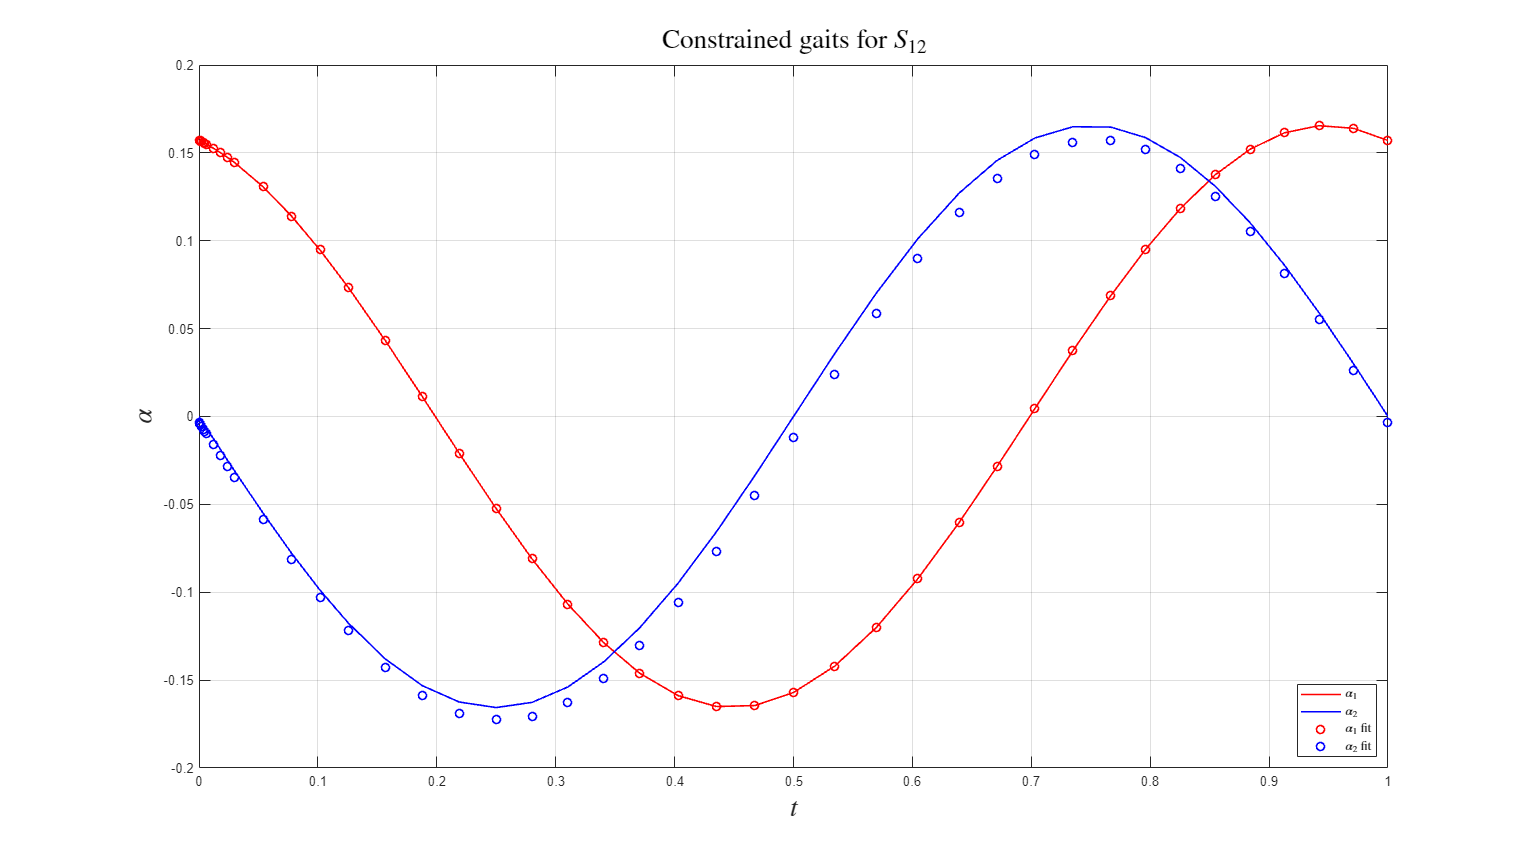

% Let's recreate the fit function
sfit = @(b,x)  b(1).*(sin(2*pi*x + 2*pi/b(2))) + b(3);
% Compute the fit with the time vector
y1 = sfit(s1,t); y2 = sfit(s2,t);
% Recreate the plot
figure('units','pixels','position',[0 0 1920 1080],'Color','w')
plot(t, y(:,1), 'r', 'linewidth', 1.2,'DisplayName','$\alpha_1$'); % alpha_1
hold on; grid on;
plot(t, y(:,2), 'b', 'linewidth', 1.2,'DisplayName','$\alpha_2$'); % alpha_2
plot(t, y1, 'ro', 'linewidth', 1.2,'DisplayName','$\alpha_1$ fit'); % alpha_1
plot(t, y2, 'bo', 'linewidth', 1.2,'DisplayName','$\alpha_2$ fit'); % alpha_2
xlabel('$t$','Interpreter','latex',FontSize=20);
ylabel('$\alpha$','Interpreter','latex',FontSize=20);
title('Constrained gaits for $S_{12}$','Interpreter','latex',FontSize=20);
legend('location','southeast','Interpreter','latex',FontSize=10);

The fit is perfect! Now, we just have to remove the time-dependence and plot it in the corresponding 2-element shape slice. Let's overlay this on top of the iso-$k^2$ surface plot that we did in the last section.

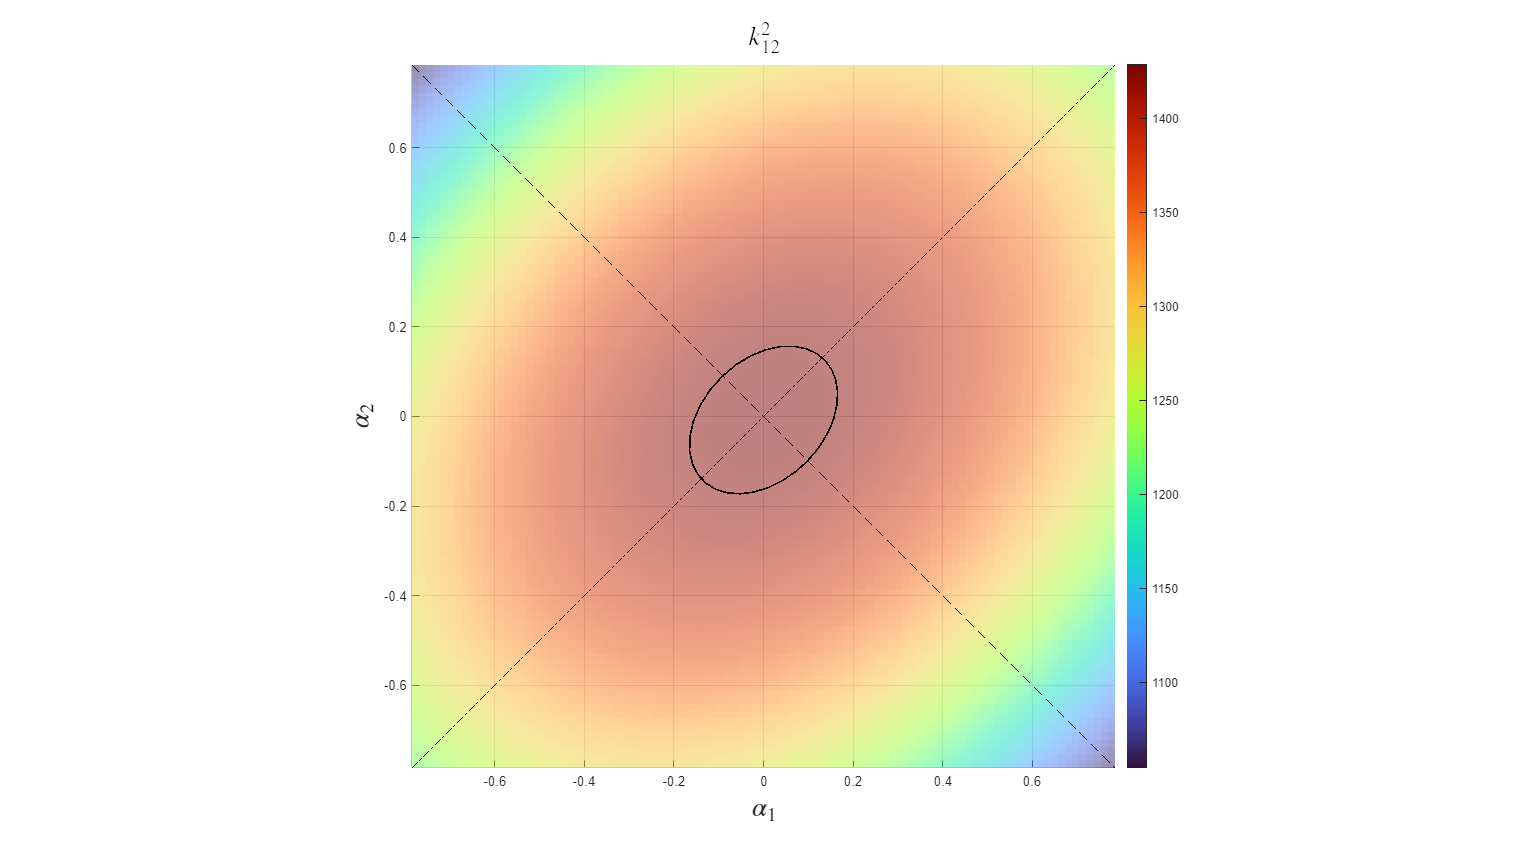

dnum = 100;                
xx = linspace(-ank,ank,dnum);          
yy = xx;
[a1,a2] = meshgrid(xx,yy);
ksq_sweep = ksq_12_func(0, aa, ll, a1, a2);
ksq_M = ksq_12_func(0, aa, ll, xx, yy);
ksq_m = ksq_12_func(0, aa, ll, xx, -yy);
% ksq_x = ksq_12_func(0, aa, ll, xx, 0*yy);
% ksq_y = ksq_12_func(0, aa, ll, 0*xx, yy);
ksq_psi = ksq_12_func(0, aa, ll, y1, y2);
figure('units','pixels','position',[0 0 1920 1080],'Color','w')
surf(a1,a2,ksq_sweep,'EdgeColor','none','FaceAlpha',0.5); % 50% transparency
axis equal tight tight; hold on; view(2);
colormap(turbo);
colorbar();
line(xx,yy,ksq_M,'Color','k','LineStyle','-.');
line(xx,-yy,ksq_m,'Color','k','LineStyle','--');
% line(0*xx,yy,ksq_y,'Color','k','LineStyle',':');
% line(xx,0*yy,ksq_x,'Color','k','LineStyle',':');
line(y1,y2,ksq_psi,'Color', 'k','LineStyle','-', 'LineWidth', 1.2); % constrained gait trajectory
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
title('$k^2_{12}$','Interpreter','latex',FontSize=20);

With further investgation, we can see that the iso-lines are not always sinusoidal as we move farther away from the singularity-- this is can be observed clearly in the next section.

### Iso-$k^2$ contours and flow

The goal here is to take a vector field based approach to modeling the $k^2$ level-sets and analyze the saddle and center behavior exhibited by our fitted curve.

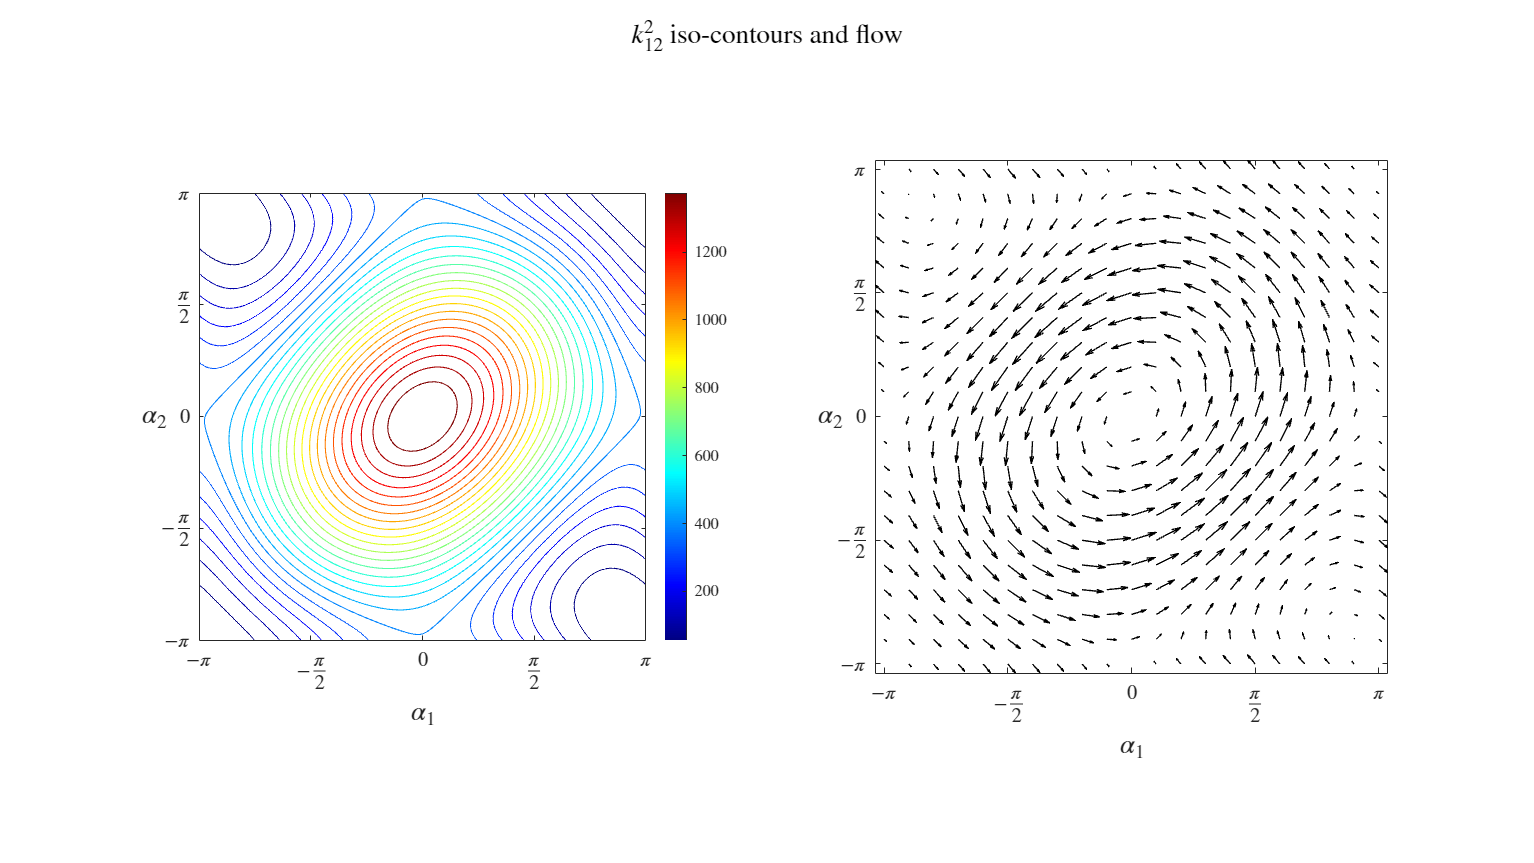

% check if we are doing the HAMR case -- 2023/05/03 working on the HAMR case right now
hamr6_F = true;
if hamr6_F
    datname = 'Data\HAMR6_SE2_kinematics.mat';
else
    datname = 'Data\case_1_kinematics.mat';
end
% Load the data from the previous section:
addpath 'Live Scripts'\ Data\ 'Utility Functions'\;
load(datname);
syms a l real positive % syms tau real
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 theta real
rot_in_ij = [cos(theta), -sin(theta);
            sin(theta), cos(theta)];
rot_in_ij = matlabFunction(rot_in_ij, 'Vars', theta);

if hamr6_F
    aa = hamr_a;                                 
    ll = hamr_l;  
else
    aa = 1;                                 
    ll = 1;
end
ank = pi/4;

% Conside the S12 submanifold info
ksq = matlabFunction(ksq_12,'Vars',[a, l, alpha_1, alpha_2]);
dpsi_12 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_12,alpha_1) diff(ksq_12,alpha_2)]','Steps',10);
dpsi_x_magscaled = [1,0]*dpsi_12; dpsi_y_magscaled = [0,1]*dpsi_12;
dpsi_x_magscaled = matlabFunction(dpsi_x_magscaled,'Vars',[a, l, alpha_1, alpha_2]);
dpsi_y_magscaled = matlabFunction(dpsi_y_magscaled,'Vars',[a, l, alpha_1, alpha_2]);

% Plotting function
plot_ksq_isocontflow(ksq,dpsi_x_magscaled,dpsi_y_magscaled,1,2,aa,ll);

This is great! Let's abandon the gait constraint and switching line approaches. Instead we shall choose to remain on the level-sets using the local flow information and then define that an infinitesimal $\phi_{ij}$-slice is obtained by flowing along $-d\phi_{ij}$ in swing phase and $+d\phi_{ij}$ (showing in the iso-$k^2$ flow plot above) in the stance phase. But, there is one more change to make-- the flow vector fields seem to be scaled by the gradient magnitude, but we only need(/care about) the direction for generating infinitesimal disps. Let's also look at this stuff for an ispi-lateral submanifold (say $S_{23}$) and alternating submanifold (say $S_{24}$).

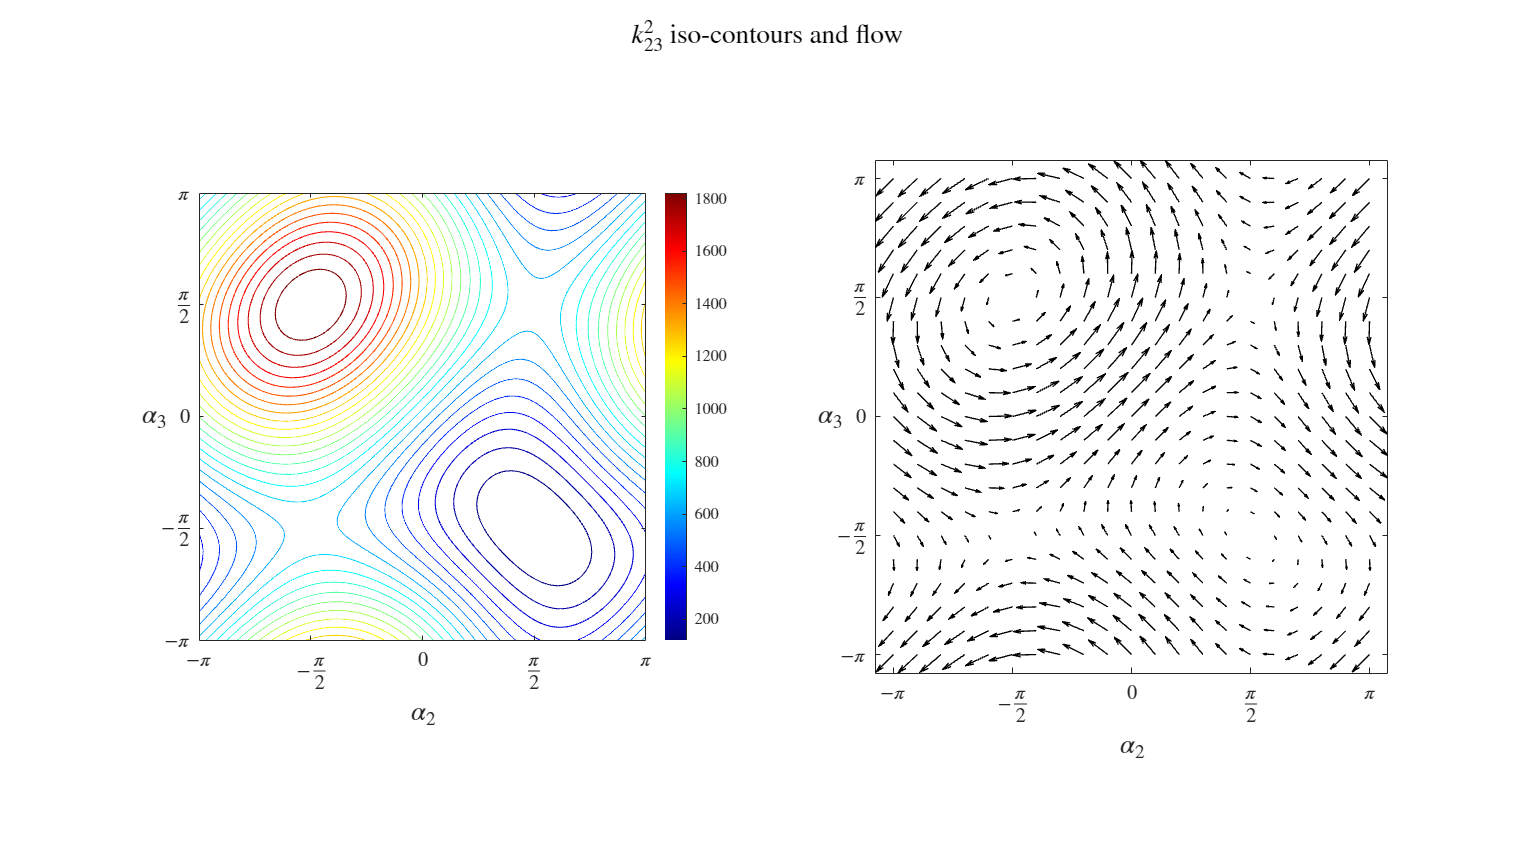

%---------------------------------------------------------------------------------------------------
ksq = matlabFunction(ksq_23,'Vars',[a, l, alpha_2, alpha_3]);
dpsi_23 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_23,alpha_2) diff(ksq_23,alpha_3)]','Steps',10);
dpsi_x_magscaled = [1,0]*dpsi_23; dpsi_y_magscaled = [0,1]*dpsi_23;
dpsi_x_magscaled = matlabFunction(dpsi_x_magscaled,'Vars',[a, l, alpha_2, alpha_3]); 
dpsi_y_magscaled = matlabFunction(dpsi_y_magscaled,'Vars',[a, l, alpha_2, alpha_3]);
plot_ksq_isocontflow(ksq,dpsi_x_magscaled,dpsi_y_magscaled,2,3,aa,ll);

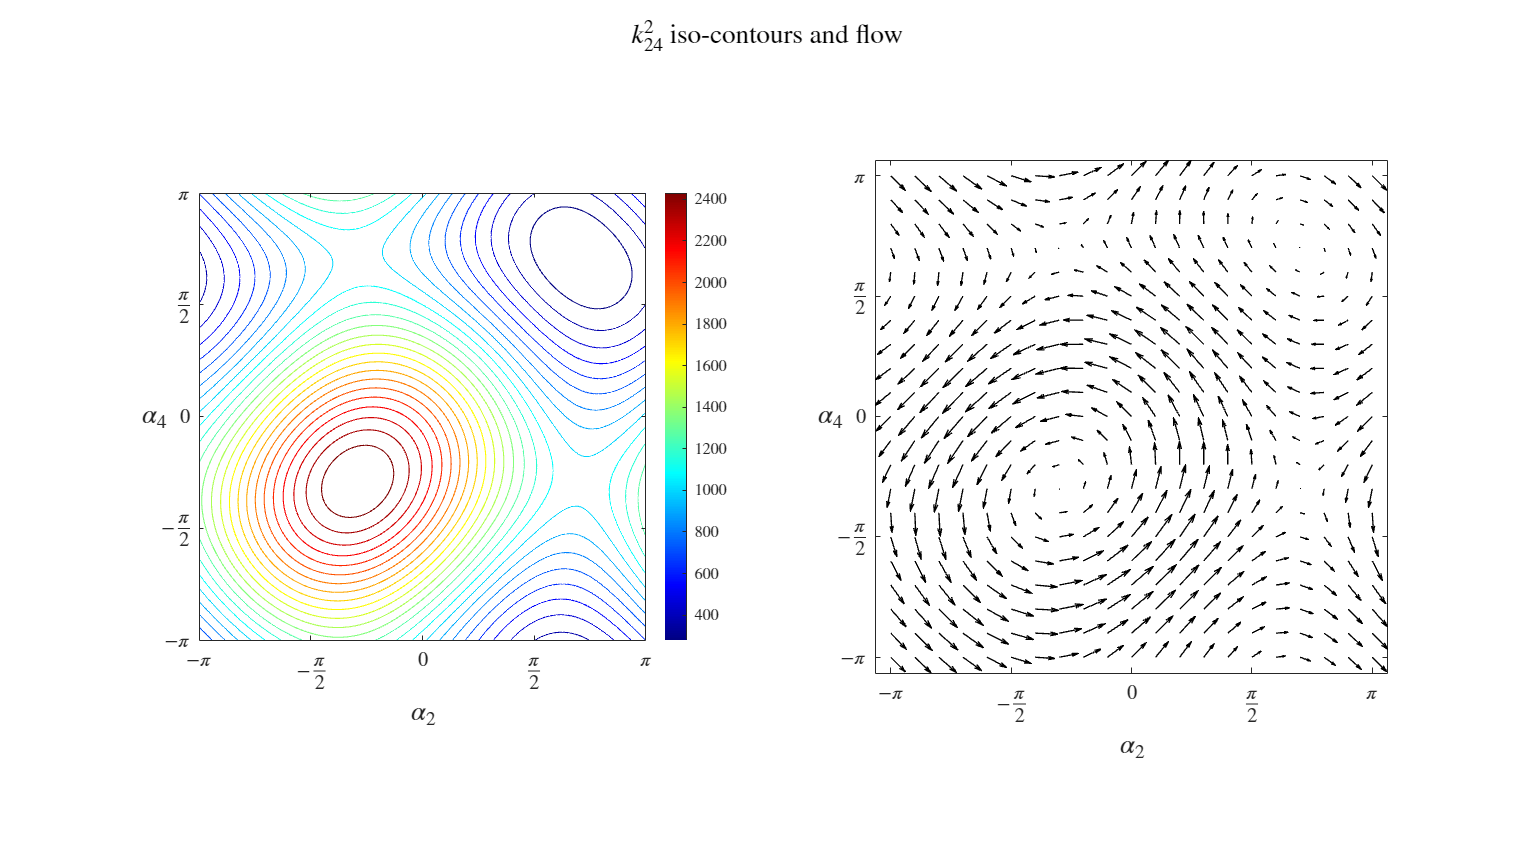

%---------------------------------------------------------------------------------------------------
ksq = matlabFunction(ksq_24,'Vars',[a, l, alpha_2, alpha_4]);
dpsi_24 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_24,alpha_2) diff(ksq_24,alpha_4)]','Steps',10);
dpsi_x_magscaled = [1,0]*dpsi_24; dpsi_y_magscaled = [0,1]*dpsi_24;
dpsi_x_magscaled = matlabFunction(dpsi_x_magscaled,'Vars',[a, l, alpha_2, alpha_4]); 
dpsi_y_magscaled = matlabFunction(dpsi_y_magscaled,'Vars',[a, l, alpha_2, alpha_4]);
plot_ksq_isocontflow(ksq,dpsi_x_magscaled,dpsi_y_magscaled,2,4,aa,ll);

### Kinematics Structure -- Path constraints

Now, we have everything to proceed towards the analysis of connection vector fields for the case 1 system. As a final step, let's pack all of these results in the kinematic structure.

% check if we are doing the HAMR case -- 2023/05/03 working on the HAMR case right now
hamr6_F = true;
if hamr6_F
    datname = 'Data\HAMR6_SE2_kinematics.mat';
else
    datname = 'Data\case_1_kinematics.mat';
end
% Load the data from the previous section:
addpath 'Live Scripts'\ Data\ 'Utility Functions'\;
load(datname);
syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 theta real
rot_in_ij = [cos(theta), -sin(theta);
            sin(theta), cos(theta)];
rot_in_ij = matlabFunction(rot_in_ij, 'Vars', theta);

% Pack the information into a kinematic strcture and save it in the
% case_1_kinematics.mat file ----------------------------------------------
%------------------------------------ ksq scalar field
kin = [];
kin.ksq_ij{1} = matlabFunction(ksq_12,'Vars',[a, l, alpha_1, alpha_2]);
kin.ksq_ij{2} = matlabFunction(ksq_23,'Vars',[a, l, alpha_2, alpha_3]);
kin.ksq_ij{3} = matlabFunction(ksq_34,'Vars',[a, l, alpha_3, alpha_4]);
kin.ksq_ij{4} = matlabFunction(ksq_41,'Vars',[a, l, alpha_4, alpha_1]);
kin.ksq_ij{5} = matlabFunction(ksq_13,'Vars',[a, l, alpha_1, alpha_3]);
kin.ksq_ij{6} = matlabFunction(ksq_24,'Vars',[a, l, alpha_2, alpha_4]);

%------------------------------------ gradient of ksq
% kin.dksq_ij{1, 1} = matlabFunction(dksq_12_i,'Vars',[a, l, alpha_1, alpha_2]); kin.dksq_ij{1, 2} = matlabFunction(dksq_12_j,'Vars',[a, l, alpha_1, alpha_2]);
% kin.dksq_ij{2, 1} = matlabFunction(dksq_23_i,'Vars',[a, l, alpha_2, alpha_3]); kin.dksq_ij{2, 2} = matlabFunction(dksq_23_j,'Vars',[a, l, alpha_2, alpha_3]);
% kin.dksq_ij{3, 1} = matlabFunction(dksq_34_i,'Vars',[a, l, alpha_3, alpha_4]); kin.dksq_ij{3, 2} = matlabFunction(dksq_34_j,'Vars',[a, l, alpha_3, alpha_4]);
% kin.dksq_ij{4, 1} = matlabFunction(dksq_41_i,'Vars',[a, l, alpha_4, alpha_1]); kin.dksq_ij{4, 2} = matlabFunction(dksq_41_j,'Vars',[a, l, alpha_4, alpha_1]);
% kin.dksq_ij{5, 1} = matlabFunction(dksq_13_i,'Vars',[a, l, alpha_1, alpha_3]); kin.dksq_ij{5, 2} = matlabFunction(dksq_13_j,'Vars',[a, l, alpha_1, alpha_3]);
% kin.dksq_ij{6, 1} = matlabFunction(dksq_24_i,'Vars',[a, l, alpha_2, alpha_4]); kin.dksq_ij{6, 2} = matlabFunction(dksq_24_j,'Vars',[a, l, alpha_2, alpha_4]);
kin.dksq_ij{1} = matlabFunction([dksq_12_i; dksq_12_j],'Vars',[a, l, alpha_1, alpha_2]);
kin.dksq_ij{2} = matlabFunction([dksq_23_i; dksq_23_j],'Vars',[a, l, alpha_2, alpha_3]);
kin.dksq_ij{3} = matlabFunction([dksq_34_i; dksq_34_j],'Vars',[a, l, alpha_3, alpha_4]);
kin.dksq_ij{4} = matlabFunction([dksq_41_i; dksq_41_j],'Vars',[a, l, alpha_4, alpha_1]);
kin.dksq_ij{5} = matlabFunction([dksq_13_i; dksq_13_j],'Vars',[a, l, alpha_1, alpha_3]);
kin.dksq_ij{6} = matlabFunction([dksq_24_i; dksq_24_j],'Vars',[a, l, alpha_2, alpha_4]);

%------------------------------------ gradient-scaled, iso-ksq flow vector
dpsi_12 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_12,alpha_1) diff(ksq_12,alpha_2)]','Steps',10); % S12
kin.dpsi_ij{1} = dpsi_12;
kin.dpsi_ij_s_vector{1} = matlabFunction(dpsi_12,'Vars',[a, l, alpha_1, alpha_2]); 
dpsi_23 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_23,alpha_2) diff(ksq_23,alpha_3)]','Steps',10); % S23
kin.dpsi_ij{2} = dpsi_23;
kin.dpsi_ij_s_vector{2} = matlabFunction(dpsi_23,'Vars',[a, l, alpha_2, alpha_3]); 
dpsi_34 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_34,alpha_3) diff(ksq_34,alpha_4)]','Steps',10); % S34
kin.dpsi_ij{3} = dpsi_34;
kin.dpsi_ij_s_vector{3} = matlabFunction(dpsi_34,'Vars',[a, l, alpha_3, alpha_4]); 
dpsi_41 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_41,alpha_4) diff(ksq_41,alpha_1)]','Steps',10); % S41
kin.dpsi_ij{4} = dpsi_41;
kin.dpsi_ij_s_vector{4} = matlabFunction(dpsi_41,'Vars',[a, l, alpha_4, alpha_1]); 
dpsi_13 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_13,alpha_1) diff(ksq_13,alpha_3)]','Steps',10); % S13
kin.dpsi_ij{5} = dpsi_13;
kin.dpsi_ij_s_vector{5} = matlabFunction(dpsi_13,'Vars',[a, l, alpha_1, alpha_3]); 
dpsi_24 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_24,alpha_2) diff(ksq_24,alpha_4)]','Steps',10); % S24
kin.dpsi_ij{6} = dpsi_24;
kin.dpsi_ij_s_vector{6} = matlabFunction(dpsi_24,'Vars',[a, l, alpha_2, alpha_4]);

%------------------------------------ gradient-scaled, iso-ksq flow elements (square-root for disps!)
dpsi_12 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_12,alpha_1) diff(ksq_12,alpha_2)]','Steps',10); % S12
dpsi_x = [1,0]*dpsi_12; dpsi_y = [0,1]*dpsi_12;
kin.dpsi_ij_s{1,1} = matlabFunction(dpsi_x,'Vars',[a, l, alpha_1, alpha_2]); 
kin.dpsi_ij_s{1,2} = matlabFunction(dpsi_y,'Vars',[a, l, alpha_1, alpha_2]);
dpsi_23 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_23,alpha_2) diff(ksq_23,alpha_3)]','Steps',10); % S23
dpsi_x = [1,0]*dpsi_23; dpsi_y = [0,1]*dpsi_23;
kin.dpsi_ij_s{2,1} = matlabFunction(dpsi_x,'Vars',[a, l, alpha_2, alpha_3]); 
kin.dpsi_ij_s{2,2} = matlabFunction(dpsi_y,'Vars',[a, l, alpha_2, alpha_3]);
dpsi_34 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_34,alpha_3) diff(ksq_34,alpha_4)]','Steps',10); % S34
dpsi_x = [1,0]*dpsi_34; dpsi_y = [0,1]*dpsi_34;
kin.dpsi_ij_s{3,1} = matlabFunction(dpsi_x,'Vars',[a, l, alpha_3, alpha_4]); 
kin.dpsi_ij_s{3,2} = matlabFunction(dpsi_y,'Vars',[a, l, alpha_3, alpha_4]);
dpsi_41 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_41,alpha_4) diff(ksq_41,alpha_1)]','Steps',10); % S41
dpsi_x = [1,0]*dpsi_41; dpsi_y = [0,1]*dpsi_41;
kin.dpsi_ij_s{4,1} = matlabFunction(dpsi_x,'Vars',[a, l, alpha_4, alpha_1]); 
kin.dpsi_ij_s{4,2} = matlabFunction(dpsi_y,'Vars',[a, l, alpha_4, alpha_1]);
dpsi_13 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_13,alpha_1) diff(ksq_13,alpha_3)]','Steps',10); % S13
dpsi_x = [1,0]*dpsi_13; dpsi_y = [0,1]*dpsi_13;
kin.dpsi_ij_s{5,1} = matlabFunction(dpsi_x,'Vars',[a, l, alpha_1, alpha_3]); 
kin.dpsi_ij_s{5,2} = matlabFunction(dpsi_y,'Vars',[a, l, alpha_1, alpha_3]);
dpsi_24 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_24,alpha_2) diff(ksq_24,alpha_4)]','Steps',10); % S24
dpsi_x = [1,0]*dpsi_24; dpsi_y = [0,1]*dpsi_24;
kin.dpsi_ij_s{6,1} = matlabFunction(dpsi_x,'Vars',[a, l, alpha_2, alpha_4]); 
kin.dpsi_ij_s{6,2} = matlabFunction(dpsi_y,'Vars',[a, l, alpha_2, alpha_4]);

%------------------------------------ connection vector fields, element-wise
Ax_1_12 = A_1_12(1,1); Ax_2_12 = A_1_12(1,2); % S12
Ay_1_12 = A_1_12(2,1); Ay_2_12 = A_1_12(2,2);
Atheta_1_12 = A_1_12(3,1); Atheta_2_12 = A_1_12(3,2);
kin.Ax_ij{1} = {Ax_1_12, Ax_2_12};
kin.Ay_ij{1} = {Ay_1_12, Ay_2_12};
kin.Atheta_ij{1} = {Atheta_1_12, Atheta_2_12};
Ax_1_23 = A_1_23(1,2); Ax_2_23 = A_1_23(1,3); % S23
Ay_1_23 = A_1_23(2,2); Ay_2_23 = A_1_23(2,3);
Atheta_1_23 = A_1_23(3,2); Atheta_2_23 = A_1_23(3,3);
kin.Ax_ij{2} = {Ax_1_23, Ax_2_23};
kin.Ay_ij{2} = {Ay_1_23, Ay_2_23};
kin.Atheta_ij{2} = {Atheta_1_23, Atheta_2_23};
Ax_1_34 = A_1_34(1,3); Ax_2_34 = A_1_34(1,4); % S34
Ay_1_34 = A_1_34(2,3); Ay_2_34 = A_1_34(2,4);
Atheta_1_34 = A_1_34(3,3); Atheta_2_34 = A_1_34(3,4);
kin.Ax_ij{3} = {Ax_1_34, Ax_2_34};
kin.Ay_ij{3} = {Ay_1_34, Ay_2_34};
kin.Atheta_ij{3} = {Atheta_1_34, Atheta_2_34};
Ax_1_41 = A_1_41(1,4); Ax_2_41 = A_1_41(1,1); % S41
Ay_1_41 = A_1_41(2,4); Ay_2_41 = A_1_41(2,1);
Atheta_1_41 = A_1_41(3,4); Atheta_2_41 = A_1_41(3,1);
kin.Ax_ij{4} = {Ax_1_41, Ax_2_41};
kin.Ay_ij{4} = {Ay_1_41, Ay_2_41};
kin.Atheta_ij{4} = {Atheta_1_41, Atheta_2_41};
Ax_1_13 = A_1_13(1,1); Ax_2_13 = A_1_13(1,3); % S13
Ay_1_13 = A_1_13(2,1); Ay_2_13 = A_1_13(2,3);
Atheta_1_13 = A_1_13(3,1); Atheta_2_13 = A_1_13(3,3);
kin.Ax_ij{5} = {Ax_1_13, Ax_2_13};
kin.Ay_ij{5} = {Ay_1_13, Ay_2_13};
kin.Atheta_ij{5} = {Atheta_1_13, Atheta_2_13};
Ax_1_24 = A_1_24(1,2); Ax_2_24 = A_1_24(1,4); % S24
Ay_1_24 = A_1_24(2,2); Ay_2_24 = A_1_24(2,4);
Atheta_1_24 = A_1_24(3,2); Atheta_2_24 = A_1_24(3,4);
kin.Ax_ij{6} = {Ax_1_24, Ax_2_24};
kin.Ay_ij{6} = {Ay_1_24, Ay_2_24};
kin.Atheta_ij{6} = {Atheta_1_24, Atheta_2_24};

% Save
save(datname,'kin','-append');

% Clear everything after writing information
clear all; close all; clc;

### Analytical Total lie-bracket or Generalized Curl

Before we move towards analysis of the connection vector field and the generation of infinitesimal disps, it is good to set up the symbolic machinery to compute those quantities. The following papers were referred to create the symbolic functions shown in this section,

1) [https://link.springer.com/article/10.1140/epjst/e2015-50085-y](https://link.springer.com/article/10.1140/epjst/e2015-50085-y) -- nonconservativity and noncommutativity in locomotion; **equation C.3 and C.4**

2) [https://ieeexplore.ieee.org/abstract/document/8758237](https://ieeexplore.ieee.org/abstract/document/8758237) -- geometry of optimal gaits for drag-dominated kinematic systems; **equation 12**

3) [https://ieeexplore.ieee.org/abstract/document/9774857](https://ieeexplore.ieee.org/abstract/document/9774857) -- geometry of optimal gaits for inertia-dominated kinematic systems; **equation 12**

**The total lie-bracket of the connection vector field is approximated linearly as the sum of the exterior derivative and first order lie bracket,**


$$D(-\mathbf{A}) = -d\mathbf{A} + [\mathbf{A}_1 \, , \, \mathbf{A}_2]$$


We shall compute the components and finally get the generalized curl.

% check if we are doing the HAMR case -- 2023/05/03 working on the HAMR case right now
hamr6_F = true;
if hamr6_F
    datname = 'Data\HAMR6_SE2_kinematics.mat';
else
    datname = 'Data\case_1_kinematics.mat';
end
% Load the data from the previous section:
addpath 'Live Scripts'\ Data\ 'Utility Functions'\;
load(datname);
syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 real

% Create the connection we shall analyze
A = A_1_12(:,1:2)

% Separate the connection into components
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
% Compute the exterior derivative, and separate into components
mdA = -simplify(diff(A(:,1),alpha_2) - diff(A(:,2),alpha_1), 'Steps', 50)

% Compute the first order lie-bracket, and separate into components
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',50)

$$lb\_A = \left(\begin{array}{c} \frac{a^{2}\,l\,\left(4\,\cos\left(\alpha_{1}+\alpha_{2}\right)+4\,\cos\left(\alpha_{1}-\alpha_{2}\right)+a\,\cos\left(2\,\alpha_{1}-\alpha_{2}\right)+3\,a\,\cos\left(\alpha_{1}\right)+3\,a\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{1}-2\,\alpha_{2}\right)\right)}{8\,\left(a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}\right)+2\,a\,\cos\left(\alpha_{2}\right)+a^{2}+2\right)}\\ \frac{a^{2}\,l\,\left(a+2\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)\,\left(392\,\sin\left(\alpha_{1}\right)-506\,\cos\left(\alpha_{1}\right)-253\,a-49\,a^{2}\,\sin\left(\alpha_{1}-2\,\alpha_{2}\right)+294\,a\,\sin\left(\alpha_{1}+\alpha_{2}\right)+49\,a^{2}\,\sin\left(2\,\alpha_{1}-\alpha_{2}\right)-253\,a\,\cos\left(\alpha_{1}-\alpha_{2}\right)+98\,a\,\sin\left(\alpha_{1}-\alpha_{2}\right)+98\,a\,\sin\left(2\,\alpha_{1}\right)+147\,a^{2}\,\sin\left(\alpha_{1}\right)+147\,a^{2}\,\sin\left(\alpha_{2}\right)\right)}{784\,{\left(a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}\right)+2\,a\,\cos\left(\alpha_{2}\right)+a^{2}+2\right)}^{2}}+\frac{a^{2}\,l\,\left(a+2\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)\,\left(253\,a+506\,\cos\left(\alpha_{2}\right)+392\,\sin\left(\alpha_{2}\right)-49\,a^{2}\,\sin\left(\alpha_{1}-2\,\alpha_{2}\right)+294\,a\,\sin\left(\alpha_{1}+\alpha_{2}\right)+49\,a^{2}\,\sin\left(2\,\alpha_{1}-\alpha_{2}\right)+253\,a\,\cos\left(\alpha_{1}-\alpha_{2}\right)-98\,a\,\sin\left(\alpha_{1}-\alpha_{2}\right)+98\,a\,\sin\left(2\,\alpha_{2}\right)+147\,a^{2}\,\sin\left(\alpha_{1}\right)+147\,a^{2}\,\sin\left(\alpha_{2}\right)\right)}{784\,{\left(a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}\right)+2\,a\,\cos\left(\alpha_{2}\right)+a^{2}+2\right)}^{2}}\\ 0 \end{array}\right)$$

% Finally add the exterior derivative and lie-bracket to obtain the
% generalized curl or total lie-bracket; split it component-wise.
simplify(mdA + lb_A,'Steps',50)

This is great! Now, let's compute this for each submanifold and store it in the kinematics structure.

### Kinematics Structure -- Total lie-bracket $D(-\mathbf{A})$

% check if we are doing the HAMR case -- 2023/05/03 working on the HAMR case right now
hamr6_F = true;
if hamr6_F
    datname = 'Data\HAMR6_SE2_kinematics.mat';
else
    datname = 'Data\case_1_kinematics.mat';
end
% Load the data from the previous section:
addpath 'Live Scripts'\ Data\ 'Utility Functions'\;
load(datname);
syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 real

% Simplification steps ---------------------------------------------
stp = 30;
%------------------------------------ Total lie-bracket element-wise
A = A_1_12(:,1:2); i = 1; % S12
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
mdA = -simplify(diff(A(:,1),alpha_2) - diff(A(:,2),alpha_1), 'Steps', stp);
mdA__x = mdA(1); mdA__y = mdA(2); mdA__theta = mdA(3);
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',stp);
lb_A__x = lb_A(1); lb_A__y = lb_A(2); lb_A__theta = lb_A(3);
D_mA = simplify(mdA + lb_A,'Steps',stp);
D_mA__x = D_mA(1); D_mA_y = D_mA(2); D_mA_theta = D_mA(3);
kin.mdA_x{i} = mdA__x; kin.mdA_y{i} = mdA__y; kin.mdA_theta{i} = mdA__theta; % save
kin.lb_A_x{i} = lb_A__x; kin.lb_A_y{i} = lb_A__y; kin.lb_A_theta{i} = lb_A__theta;
kin.D_mA_x{i} = D_mA__x; kin.D_mA_y{i} = D_mA_y; kin.D_mA_theta{i} = D_mA_theta;
A = A_1_23(:,2:3); i = 2; % S23
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
mdA = -simplify(diff(A(:,1),alpha_3) - diff(A(:,2),alpha_2), 'Steps', stp);
mdA__x = mdA(1); mdA__y = mdA(2); mdA__theta = mdA(3);
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',stp);
lb_A__x = lb_A(1); lb_A__y = lb_A(2); lb_A__theta = lb_A(3);
D_mA = simplify(mdA + lb_A,'Steps',stp);
D_mA__x = D_mA(1); D_mA_y = D_mA(2); D_mA_theta = D_mA(3);
kin.mdA_x{i} = mdA__x; kin.mdA_y{i} = mdA__y; kin.mdA_theta{i} = mdA__theta;
kin.lb_A_x{i} = lb_A__x; kin.lb_A_y{i} = lb_A__y; kin.lb_A_theta{i} = lb_A__theta;
kin.D_mA_x{i} = D_mA__x; kin.D_mA_y{i} = D_mA_y; kin.D_mA_theta{i} = D_mA_theta;
A = A_1_34(:,3:4); i = 3; % S34
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
mdA = -simplify(diff(A(:,1),alpha_4) - diff(A(:,2),alpha_3), 'Steps', stp);
mdA__x = mdA(1); mdA__y = mdA(2); mdA__theta = mdA(3);
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',stp);
lb_A__x = lb_A(1); lb_A__y = lb_A(2); lb_A__theta = lb_A(3);
D_mA = simplify(mdA + lb_A,'Steps',stp);
D_mA__x = D_mA(1); D_mA_y = D_mA(2); D_mA_theta = D_mA(3);
kin.mdA_x{i} = mdA__x; kin.mdA_y{i} = mdA__y; kin.mdA_theta{i} = mdA__theta;
kin.lb_A_x{i} = lb_A__x; kin.lb_A_y{i} = lb_A__y; kin.lb_A_theta{i} = lb_A__theta;
kin.D_mA_x{i} = D_mA__x; kin.D_mA_y{i} = D_mA_y; kin.D_mA_theta{i} = D_mA_theta;
A = [A_1_41(:,4),A_1_41(:,1)]; i = 4; % S41
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
mdA = -simplify(diff(A(:,1),alpha_1) - diff(A(:,2),alpha_4), 'Steps', stp);
mdA__x = mdA(1); mdA__y = mdA(2); mdA__theta = mdA(3);
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',stp);
lb_A__x = lb_A(1); lb_A__y = lb_A(2); lb_A__theta = lb_A(3);
D_mA = simplify(mdA + lb_A,'Steps',stp);
D_mA__x = D_mA(1); D_mA_y = D_mA(2); D_mA_theta = D_mA(3);
kin.mdA_x{i} = mdA__x; kin.mdA_y{i} = mdA__y; kin.mdA_theta{i} = mdA__theta;
kin.lb_A_x{i} = lb_A__x; kin.lb_A_y{i} = lb_A__y; kin.lb_A_theta{i} = lb_A__theta;
kin.D_mA_x{i} = D_mA__x; kin.D_mA_y{i} = D_mA_y; kin.D_mA_theta{i} = D_mA_theta;
A = [A_1_13(:,1),A_1_13(:,3)]; i = 5; % S13
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
mdA = -simplify(diff(A(:,1),alpha_3) - diff(A(:,2),alpha_1), 'Steps', stp);
mdA__x = mdA(1); mdA__y = mdA(2); mdA__theta = mdA(3);
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',stp);
lb_A__x = lb_A(1); lb_A__y = lb_A(2); lb_A__theta = lb_A(3);
D_mA = simplify(mdA + lb_A,'Steps',stp);
D_mA__x = D_mA(1); D_mA_y = D_mA(2); D_mA_theta = D_mA(3);
kin.mdA_x{i} = mdA__x; kin.mdA_y{i} = mdA__y; kin.mdA_theta{i} = mdA__theta;
kin.lb_A_x{i} = lb_A__x; kin.lb_A_y{i} = lb_A__y; kin.lb_A_theta{i} = lb_A__theta;
kin.D_mA_x{i} = D_mA__x; kin.D_mA_y{i} = D_mA_y; kin.D_mA_theta{i} = D_mA_theta;
A = [A_1_24(:,2),A_1_24(:,4)]; i = 6; % S24
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
mdA = -simplify(diff(A(:,1),alpha_4) - diff(A(:,2),alpha_2), 'Steps', stp);
mdA__x = mdA(1); mdA__y = mdA(2); mdA__theta = mdA(3);
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',stp);
lb_A__x = lb_A(1); lb_A__y = lb_A(2); lb_A__theta = lb_A(3);
D_mA = simplify(mdA + lb_A,'Steps',stp);
D_mA__x = D_mA(1); D_mA_y = D_mA(2); D_mA_theta = D_mA(3);
kin.mdA_x{i} = mdA__x; kin.mdA_y{i} = mdA__y; kin.mdA_theta{i} = mdA__theta;
kin.lb_A_x{i} = lb_A__x; kin.lb_A_y{i} = lb_A__y; kin.lb_A_theta{i} = lb_A__theta;
kin.D_mA_x{i} = D_mA__x; kin.D_mA_y{i} = D_mA_y; kin.D_mA_theta{i} = D_mA_theta;

% Save
save(datname,'kin','-append');

% Clear everything after writing information
clear all; close all; clc;

### Analytical Stratified Panels

Here, we compute the analytical version of the infinitesimal disps. An infinitesimal gait in the $ij^{th}$ shape-space slice is defined as swinging along $-d\phi_{ij}$ and stancing along $+d\phi_{ij}$. Hence, we simply compute this multiplying the connection dual with the shape-space velocity (is independent of time for a connection based model).

% check if we are doing the HAMR case -- 2023/05/03 working on the HAMR case right now
hamr6_F = true;
if hamr6_F
    datname = 'Data\HAMR6_SE2_kinematics.mat';
else
    datname = 'Data\case_1_kinematics.mat';
end
% Load the data from the previous section:
addpath 'Live Scripts'\ Data\ 'Utility Functions'\;
load(datname);
syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 real

% Get the connection and gait constraint
A = A_1_12(:,1:2)

dpsi_unit = kin.dpsi_ij{1}/norm(kin.dpsi_ij{1})

$$dpsi\_unit = \left(\begin{array}{c} -\frac{2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{2}\right)-a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)}{\sqrt{4\,l^{4}\,{\left|a\,\left(2\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)\right|}^{2}+4\,l^{4}\,{\left|a\,\left(2\,\sin\left(\alpha_{2}\right)-a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)\right|}^{2}}}\\ \frac{2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)}{\sqrt{4\,l^{4}\,{\left|a\,\left(2\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)\right|}^{2}+4\,l^{4}\,{\left|a\,\left(2\,\sin\left(\alpha_{2}\right)-a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)\right|}^{2}}} \end{array}\right)$$

% Compute the infinitesimal disp (just multiply them)
simplify(A*dpsi_unit,'Steps',50)

Alright, let's compute this and package it for each submanifold.

### Kinematics Structure -- Infinitesimal Displacements $dz_\psi$

% check if we are doing the HAMR case -- 2023/05/03 working on the HAMR case right now
hamr6_F = true;
if hamr6_F
    datname = 'Data\HAMR6_SE2_kinematics.mat';
else
    datname = 'Data\case_1_kinematics.mat';
end
% Load the data from the previous section:
addpath 'Live Scripts'\ Data\ 'Utility Functions'\;
load(datname);
syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 real

stp = 50;
%------------------------------------ Stratified disps element-wise
i = 1;
A = A_1_12(:,1:2);                     % S12
dpsi = kin.dpsi_ij{i}/norm(kin.dpsi_ij{i});
dz_psi = -simplify(A*dpsi,'Steps',stp);
kin.dz_psi{i} = dz_psi;
kin.dz_psi_x{i} = matlabFunction(dz_psi(1),'Vars',[a, l, alpha_1, alpha_2]);
kin.dz_psi_y{i} = matlabFunction(dz_psi(2),'Vars',[a, l, alpha_1, alpha_2]);
kin.dz_psi_theta{i} = matlabFunction(dz_psi(3),'Vars',[a, l, alpha_1, alpha_2]);
kin.dpsi_12n = dpsi;
i = 2;
A = A_1_23(:,2:3);                     % S23
dpsi = kin.dpsi_ij{i}/norm(kin.dpsi_ij{i});
dz_psi = -simplify(A*dpsi,'Steps',stp);
kin.dz_psi{i} = dz_psi;
kin.dz_psi_x{i} = matlabFunction(dz_psi(1),'Vars',[a, l, alpha_2, alpha_3]);
kin.dz_psi_y{i} = matlabFunction(dz_psi(2),'Vars',[a, l, alpha_2, alpha_3]);
kin.dz_psi_theta{i} = matlabFunction(dz_psi(3),'Vars',[a, l, alpha_2, alpha_3]);
kin.dpsi_23n = dpsi;
i = 3;
A = A_1_34(:,3:4);                     % S34
dpsi = kin.dpsi_ij{i}/norm(kin.dpsi_ij{i});
dz_psi = -simplify(A*dpsi,'Steps',stp);
kin.dz_psi{i} = dz_psi;
kin.dz_psi_x{i} = matlabFunction(dz_psi(1),'Vars',[a, l, alpha_3, alpha_4]);
kin.dz_psi_y{i} = matlabFunction(dz_psi(2),'Vars',[a, l, alpha_3, alpha_4]);
kin.dz_psi_theta{i} = matlabFunction(dz_psi(3),'Vars',[a, l, alpha_3, alpha_4]);
kin.dpsi_34n = dpsi;
i = 4;
A = [A_1_41(:,4) A_1_41(:,1)];                     % S41
dpsi = kin.dpsi_ij{i}/norm(kin.dpsi_ij{i});
dz_psi = -simplify(A*dpsi,'Steps',stp);
kin.dz_psi{i} = dz_psi;
kin.dz_psi_x{i} = matlabFunction(dz_psi(1),'Vars',[a, l, alpha_4, alpha_1]);
kin.dz_psi_y{i} = matlabFunction(dz_psi(2),'Vars',[a, l, alpha_4, alpha_1]);
kin.dz_psi_theta{i} = matlabFunction(dz_psi(3),'Vars',[a, l, alpha_4, alpha_1]);
kin.dpsi_41n = dpsi;
i = 5;
A = [A_1_13(:,1) A_1_13(:,3)];                     % S13
dpsi = kin.dpsi_ij{i}/norm(kin.dpsi_ij{i});
dz_psi = -simplify(A*dpsi,'Steps',stp);
kin.dz_psi{i} = dz_psi;
kin.dz_psi_x{i} = matlabFunction(dz_psi(1),'Vars',[a, l, alpha_1, alpha_3]);
kin.dz_psi_y{i} = matlabFunction(dz_psi(2),'Vars',[a, l, alpha_1, alpha_3]);
kin.dz_psi_theta{i} = matlabFunction(dz_psi(3),'Vars',[a, l, alpha_1, alpha_3]);
kin.dpsi_13n = dpsi;
i = 6;
A = [A_1_24(:,2) A_1_24(:,4)];                     % S24
dpsi = kin.dpsi_ij{i}/norm(kin.dpsi_ij{i});
dz_psi = -simplify(A*dpsi,'Steps',stp);
kin.dz_psi{i} = dz_psi;
kin.dz_psi_x{i} = matlabFunction(dz_psi(1),'Vars',[a, l, alpha_2, alpha_4]);
kin.dz_psi_y{i} = matlabFunction(dz_psi(2),'Vars',[a, l, alpha_2, alpha_4]);
kin.dz_psi_theta{i} = matlabFunction(dz_psi(3),'Vars',[a, l, alpha_2, alpha_4]);
kin.dpsi_24n = dpsi;

% Save
save(datname,'kin','-append');

% Clear everything after writing information
clear all; close all; clc;

### Robot configuration space

The goal of this section is to plot the configuration space of the robot for simulation purposes later-- the containers

addpath 'Live Scripts'\ Data\ 'Utility Functions'\;
% check if we are doing the HAMR case -- 2023/05/03 working on the HAMR case right now
hamr6_F = true;
if hamr6_F
    datname = 'Data\HAMR6_SE2_kinematics.mat';
else
    datname = 'Data\case_1_kinematics.mat';
end
% Load the data from the previous section:
load(datname);

% Setting up the symbolic framework
syms x y theta u v beta real
v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];
M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);
L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);
g_vec = [x;
         y;
         theta];
h_vec = [u;
         v;
         beta];

g_mat = v2M_SE2(g_vec);
T_g_to_T_hg = T_gL_h(g_vec, h_vec);
T_g_to_T_gh = T_gR_h(g_vec, h_vec);
gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat);
TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]));
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]));
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);
theta_sel = [0,0,1]'; x_sel = [1,0,0]'; y_sel = [0,1,0]';

% -----------------------------------------------------------------
% Define the SE(2) frames symbolically
syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 real
h_e__b = [x, y, theta]';
% %  LEGACY CODE
% h_b__12b = [0, l, 0]';
% h_b__34b = [0, -l, 0]';
% h_12b__1b = [l, 0, 0]';
% h_12b__2b = [-l, 0, pi]';
% h_34b__3b = [-l, 0, pi]';
% h_34b__4b = [l, 0, 0]';
% h_b__1c = [l,2*l,0]';
% h_b__2c = [-l,2*l,0]';
% h_b__3c = [-l,-2*l,0]';
% h_b__4c = [l,-2*l,0]';
% syms alpha_i
% h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i];
% h_ib__i_func = matlabFunction(h_ib__i, 'Vars', [a, l, alpha_i]);
% h_1b__1 = h_ib__i_func(a,l,alpha_1);
% h_2b__2 = h_ib__i_func(a,l,alpha_2);
% h_3b__3 = h_ib__i_func(a,l,alpha_3);
% h_4b__4 = h_ib__i_func(a,l,alpha_4);

h_e__1b  = seqSE2transformation([h_e__b, h_b__12b, h_12b__1b]);                          %
h_e__2b  = seqSE2transformation([h_e__b, h_b__12b, h_12b__2b]);                          %
h_e__3b  = seqSE2transformation([h_e__b, h_b__34b, h_34b__3b]);                          %
h_e__4b  = seqSE2transformation([h_e__b, h_b__34b, h_34b__4b]);                          %
h_e__12b = seqSE2transformation([h_e__b, h_b__12b]);                                     %
h_e__34b = seqSE2transformation([h_e__b, h_b__34b]);                                     %
h_e__1   = seqSE2transformation([h_e__b, h_b__12b, h_12b__1b, h_1b__1]);                 %
h_e__2   = seqSE2transformation([h_e__b, h_b__12b, h_12b__2b, h_2b__2]);                 %
h_e__3   = seqSE2transformation([h_e__b, h_b__34b, h_34b__3b, h_3b__3]);                 %
h_e__4   = seqSE2transformation([h_e__b, h_b__34b, h_34b__4b, h_4b__4]);                 %
h_e__1c  = seqSE2transformation([h_e__b, h_b__1c]);                                      %
h_e__2c  = seqSE2transformation([h_e__b, h_b__2c]);                                      %
h_e__3c  = seqSE2transformation([h_e__b, h_b__3c]);                                      %
h_e__4c  = seqSE2transformation([h_e__b, h_b__4c]);                                      %


% System plotting points -- body, legs, k-vec, and frames (using quiver)
body_x = h_e__b(1); body_y = h_e__b(2);
bodyf_x = [eye(2),zeros(2,1)]*v2M_SE2(h_e__b)*[1,0,0]'; bodyf_y = [eye(2),zeros(2,1)]*v2M_SE2(h_e__b)*[0,1,0]';
topright2topleft_x = [h_e__1c(1) h_e__2c(1)]; topright2topleft_y = [h_e__1c(2) h_e__2c(2)];
topleft2botleft_x = [h_e__2c(1) h_e__3c(1)]; topleft2botleft_y = [h_e__2c(2) h_e__3c(2)];
botleft2botright_x = [h_e__3c(1) h_e__4c(1)]; botleft2botright_y = [h_e__3c(2) h_e__4c(2)];
botright2topright_x = [h_e__4c(1) h_e__1c(1)]; botright2topright_y = [h_e__4c(2) h_e__1c(2)];
base_topbase_x = [h_e__b(1) h_e__12b(1)]; base_topbase_y = [h_e__b(2) h_e__12b(2)];
base_botbase_x = [h_e__b(2) h_e__34b(1)]; base_botbase_y = [h_e__b(2) h_e__34b(2)];
topbase_leg1base_x = [h_e__12b(1) h_e__1b(1)]; topbase_leg1base_y = [h_e__12b(2) h_e__1b(2)];
topbase_leg2base_x = [h_e__12b(1) h_e__2b(1)]; topbase_leg2base_y = [h_e__12b(2) h_e__2b(2)];
botbase_leg3base_x = [h_e__34b(1) h_e__3b(1)]; botbase_leg3base_y = [h_e__34b(2) h_e__3b(2)];
botbase_leg4base_x = [h_e__34b(1) h_e__4b(1)]; botbase_leg4base_y = [h_e__34b(2) h_e__4b(2)];
leg1_x = h_e__1(1); leg1_y = h_e__1(2);
leg2_x = h_e__2(1); leg2_y = h_e__2(2);
leg3_x = h_e__3(1); leg3_y = h_e__3(2);
leg4_x = h_e__4(1); leg4_y = h_e__4(2);
legbase1_leg1_x =  [h_e__1b(1) h_e__1(1)]; legbase1_leg1_y =  [h_e__1b(2) h_e__1(2)];
legbase2_leg2_x =  [h_e__2b(1) h_e__2(1)]; legbase2_leg2_y =  [h_e__2b(2) h_e__2(2)];
legbase3_leg3_x =  [h_e__3b(1) h_e__3(1)]; legbase3_leg3_y =  [h_e__3b(2) h_e__3(2)];
legbase4_leg4_x =  [h_e__4b(1) h_e__4(1)]; legbase4_leg4_y =  [h_e__4b(2) h_e__4(2)];
k_leg1_leg2_x = [h_e__1(1) h_e__2(1)]; k_leg1_leg2_y = [h_e__1(2) h_e__2(2)]; k_leg1_leg2_u = k_leg1_leg2_x(2)-k_leg1_leg2_x(1); k_leg1_leg2_v = k_leg1_leg2_y(2)-k_leg1_leg2_y(1);
k_leg2_leg3_x = [h_e__2(1) h_e__3(1)]; k_leg2_leg3_y = [h_e__2(2) h_e__3(2)]; k_leg2_leg3_u = k_leg2_leg3_x(2)-k_leg2_leg3_x(1); k_leg2_leg3_v = k_leg2_leg3_y(2)-k_leg2_leg3_y(1);
k_leg3_leg4_x = [h_e__3(1) h_e__4(1)]; k_leg3_leg4_y = [h_e__3(2) h_e__4(2)]; k_leg3_leg4_u = k_leg3_leg4_x(2)-k_leg3_leg4_x(1); k_leg3_leg4_v = k_leg3_leg4_y(2)-k_leg3_leg4_y(1);
k_leg4_leg1_x = [h_e__4(1) h_e__1(1)]; k_leg4_leg1_y = [h_e__4(2) h_e__1(2)]; k_leg4_leg1_u = k_leg4_leg1_x(2)-k_leg4_leg1_x(1); k_leg4_leg1_v = k_leg4_leg1_y(2)-k_leg4_leg1_y(1);
k_leg1_leg3_x = [h_e__1(1) h_e__3(1)]; k_leg1_leg3_y = [h_e__1(2) h_e__3(2)]; k_leg1_leg3_u = k_leg1_leg3_x(2)-k_leg1_leg3_x(1); k_leg1_leg3_v = k_leg1_leg3_y(2)-k_leg1_leg3_y(1);
k_leg2_leg4_x = [h_e__2(1) h_e__4(1)]; k_leg2_leg4_y = [h_e__2(2) h_e__4(2)]; k_leg2_leg4_u = k_leg2_leg4_x(2)-k_leg2_leg4_x(1); k_leg2_leg4_v = k_leg2_leg4_y(2)-k_leg2_leg4_y(1);
legbase1_legbase2_x = [h_e__1b(1) h_e__2b(1)]; legbase1_legbase2_y = [h_e__1b(2) h_e__2b(2)];
legbase2_legbase3_x = [h_e__2b(1) h_e__3b(1)]; legbase2_legbase3_y = [h_e__2b(2) h_e__3b(2)];
legbase3_legbase4_x = [h_e__3b(1) h_e__4b(1)]; legbase3_legbase4_y = [h_e__3b(2) h_e__4b(2)];
legbase4_legbase1_x = [h_e__4b(1) h_e__1b(1)]; legbase4_legbase1_y = [h_e__4b(2) h_e__1b(2)];
legbase1_legbase3_x = [h_e__1b(1) h_e__3b(1)]; legbase1_legbase3_y = [h_e__1b(2) h_e__3b(2)];
legbase2_legbase4_x = [h_e__2b(1) h_e__4b(1)]; legbase2_legbase4_y = [h_e__2b(2) h_e__4b(2)];

% Convert to matlab function-- easier to create a time-series and store it
% to the plot structure
pltkin = [];
pltkin.bodyf_x = matlabFunction(bodyf_x,'Vars',[x, y, theta]); pltkin.bodyf_y = matlabFunction(bodyf_y,'Vars',[x, y, theta]);
pltkin.body_x = matlabFunction(body_x,'Vars',[x, y, theta]); pltkin.body_y = matlabFunction(body_y,'Vars',[x, y, theta]);
pltkin.base_topbase_x = matlabFunction(base_topbase_x,'Vars',[l, x, y, theta]); pltkin.base_topbase_y = matlabFunction(base_topbase_y,'Vars',[l, x, y, theta]);
pltkin.base_botbase_x = matlabFunction(base_botbase_x,'Vars',[l, x, y, theta]); pltkin.base_botbase_y = matlabFunction(base_botbase_y,'Vars',[l, x, y, theta]);
pltkin.topright2topleft_x = matlabFunction(topright2topleft_x,'Vars',[l, x, y, theta]); pltkin.topright2topleft_y = matlabFunction(topright2topleft_y,'Vars',[l, x, y, theta]);
pltkin.topleft2botleft_x = matlabFunction(topleft2botleft_x,'Vars',[l, x, y, theta]); pltkin.topleft2botleft_y = matlabFunction(topleft2botleft_y,'Vars',[l, x, y, theta]);
pltkin.botleft2botright_x = matlabFunction(botleft2botright_x,'Vars',[l, x, y, theta]); pltkin.botleft2botright_y = matlabFunction(botleft2botright_y,'Vars',[l, x, y, theta]);
pltkin.botright2topright_x = matlabFunction(botright2topright_x,'Vars',[l, x, y, theta]); pltkin.botright2topright_y = matlabFunction(botright2topright_y,'Vars',[l, x, y, theta]);
pltkin.topbase_leg1base_x = matlabFunction(topbase_leg1base_x,'Vars',[l, x, y, theta]); pltkin.topbase_leg1base_y = matlabFunction(topbase_leg1base_y,'Vars',[l, x, y, theta]);
pltkin.topbase_leg2base_x = matlabFunction(topbase_leg2base_x,'Vars',[l, x, y, theta]); pltkin.topbase_leg2base_y = matlabFunction(topbase_leg2base_y,'Vars',[l, x, y, theta]);
pltkin.botbase_leg3base_x = matlabFunction(botbase_leg3base_x,'Vars',[l, x, y, theta]); pltkin.botbase_leg3base_y = matlabFunction(botbase_leg3base_y,'Vars',[l, x, y, theta]);
pltkin.botbase_leg4base_x = matlabFunction(botbase_leg4base_x,'Vars',[l, x, y, theta]); pltkin.botbase_leg4base_y = matlabFunction(botbase_leg4base_y,'Vars',[l, x, y, theta]);
pltkin.leg1_x = matlabFunction(leg1_x,'Vars',[a, l, alpha_1, x, y, theta]); pltkin.leg1_y = matlabFunction(leg1_y,'Vars',[a, l, alpha_1, x, y, theta]);
pltkin.leg2_x = matlabFunction(leg2_x,'Vars',[a, l, alpha_2, x, y, theta]); pltkin.leg2_y = matlabFunction(leg2_y,'Vars',[a, l, alpha_2, x, y, theta]);
pltkin.leg3_x = matlabFunction(leg3_x,'Vars',[a, l, alpha_3, x, y, theta]); pltkin.leg3_y = matlabFunction(leg3_y,'Vars',[a, l, alpha_3, x, y, theta]);
pltkin.leg4_x = matlabFunction(leg4_x,'Vars',[a, l, alpha_4, x, y, theta]); pltkin.leg4_y = matlabFunction(leg4_y,'Vars',[a, l, alpha_4, x, y, theta]);
pltkin.legbase1_leg1_x = matlabFunction(legbase1_leg1_x,'Vars',[a, l, alpha_1, x, y, theta]); pltkin.legbase1_leg1_y = matlabFunction(legbase1_leg1_y,'Vars',[a, l, alpha_1, x, y, theta]);
pltkin.legbase2_leg2_x = matlabFunction(legbase2_leg2_x,'Vars',[a, l, alpha_2, x, y, theta]); pltkin.legbase2_leg2_y = matlabFunction(legbase2_leg2_y,'Vars',[a, l, alpha_2, x, y, theta]);
pltkin.legbase3_leg3_x = matlabFunction(legbase3_leg3_x,'Vars',[a, l, alpha_3, x, y, theta]); pltkin.legbase3_leg3_y = matlabFunction(legbase3_leg3_y,'Vars',[a, l, alpha_3, x, y, theta]);
pltkin.legbase4_leg4_x = matlabFunction(legbase4_leg4_x,'Vars',[a, l, alpha_4, x, y, theta]); pltkin.legbase4_leg4_y = matlabFunction(legbase4_leg4_y,'Vars',[a, l, alpha_4, x, y, theta]);
pltkin.k_leg1_leg2_x = matlabFunction(k_leg1_leg2_x,'Vars',[a, l, alpha_1, alpha_2, x, y, theta]); pltkin.k_leg1_leg2_y = matlabFunction(k_leg1_leg2_y,'Vars',[a, l, alpha_1, alpha_2, x, y, theta]);
pltkin.k_leg2_leg3_x = matlabFunction(k_leg2_leg3_x,'Vars',[a, l, alpha_2, alpha_3, x, y, theta]); pltkin.k_leg2_leg3_y = matlabFunction(k_leg2_leg3_y,'Vars',[a, l, alpha_2, alpha_3, x, y, theta]);
pltkin.k_leg3_leg4_x = matlabFunction(k_leg3_leg4_x,'Vars',[a, l, alpha_3, alpha_4, x, y, theta]); pltkin.k_leg3_leg4_y = matlabFunction(k_leg3_leg4_y,'Vars',[a, l, alpha_3, alpha_4, x, y, theta]);
pltkin.k_leg4_leg1_x = matlabFunction(k_leg4_leg1_x,'Vars',[a, l, alpha_4, alpha_1, x, y, theta]); pltkin.k_leg4_leg1_y = matlabFunction(k_leg4_leg1_y,'Vars',[a, l, alpha_4, alpha_1, x, y, theta]);
pltkin.k_leg1_leg3_x = matlabFunction(k_leg1_leg3_x,'Vars',[a, l, alpha_1, alpha_3, x, y, theta]); pltkin.k_leg1_leg3_y = matlabFunction(k_leg1_leg3_y,'Vars',[a, l, alpha_1, alpha_3, x, y, theta]);
pltkin.k_leg2_leg4_x = matlabFunction(k_leg2_leg4_x,'Vars',[a, l, alpha_2, alpha_4, x, y, theta]); pltkin.k_leg2_leg4_y = matlabFunction(k_leg2_leg4_y,'Vars',[a, l, alpha_2, alpha_4, x, y, theta]);
pltkin.k_leg1_leg2_u = matlabFunction(k_leg1_leg2_u,'Vars',[a, l, alpha_1, alpha_2, x, y, theta]); pltkin.k_leg1_leg2_v = matlabFunction(k_leg1_leg2_v,'Vars',[a, l, alpha_1, alpha_2, x, y, theta]);
pltkin.k_leg2_leg3_u = matlabFunction(k_leg2_leg3_u,'Vars',[a, l, alpha_2, alpha_3, x, y, theta]); pltkin.k_leg2_leg3_v = matlabFunction(k_leg2_leg3_v,'Vars',[a, l, alpha_2, alpha_3, x, y, theta]);
pltkin.k_leg3_leg4_u = matlabFunction(k_leg3_leg4_u,'Vars',[a, l, alpha_3, alpha_4, x, y, theta]); pltkin.k_leg3_leg4_v = matlabFunction(k_leg3_leg4_v,'Vars',[a, l, alpha_3, alpha_4, x, y, theta]);
pltkin.k_leg4_leg1_u = matlabFunction(k_leg4_leg1_u,'Vars',[a, l, alpha_4, alpha_1, x, y, theta]); pltkin.k_leg4_leg1_v = matlabFunction(k_leg4_leg1_v,'Vars',[a, l, alpha_4, alpha_1, x, y, theta]);
pltkin.k_leg1_leg3_u = matlabFunction(k_leg1_leg3_u,'Vars',[a, l, alpha_1, alpha_3, x, y, theta]); pltkin.k_leg1_leg3_v = matlabFunction(k_leg1_leg3_v,'Vars',[a, l, alpha_1, alpha_3, x, y, theta]);
pltkin.k_leg2_leg4_u = matlabFunction(k_leg2_leg4_u,'Vars',[a, l, alpha_2, alpha_4, x, y, theta]); pltkin.k_leg2_leg4_v = matlabFunction(k_leg2_leg4_v,'Vars',[a, l, alpha_2, alpha_4, x, y, theta]);
pltkin.legbase1_legbase2_x = matlabFunction(legbase1_legbase2_x,'Vars',[a, l, alpha_1, alpha_2, x, y, theta]); pltkin.legbase1_legbase2_y = matlabFunction(legbase1_legbase2_y,'Vars',[a, l, alpha_1, alpha_2, x, y, theta]);
pltkin.legbase2_legbase3_x = matlabFunction(legbase2_legbase3_x,'Vars',[a, l, alpha_2, alpha_3, x, y, theta]); pltkin.legbase2_legbase3_y = matlabFunction(legbase2_legbase3_y,'Vars',[a, l, alpha_2, alpha_3, x, y, theta]);
pltkin.legbase3_legbase4_x = matlabFunction(legbase3_legbase4_x,'Vars',[a, l, alpha_3, alpha_4, x, y, theta]); pltkin.legbase3_legbase4_y = matlabFunction(legbase3_legbase4_y,'Vars',[a, l, alpha_3, alpha_4, x, y, theta]);
pltkin.legbase4_legbase1_x = matlabFunction(legbase4_legbase1_x,'Vars',[a, l, alpha_4, alpha_1, x, y, theta]); pltkin.legbase4_legbase1_y = matlabFunction(legbase4_legbase1_y,'Vars',[a, l, alpha_4, alpha_1, x, y, theta]);
pltkin.legbase1_legbase3_x = matlabFunction(legbase1_legbase3_x,'Vars',[a, l, alpha_1, alpha_3, x, y, theta]); pltkin.legbase1_legbase3_y = matlabFunction(legbase1_legbase3_y,'Vars',[a, l, alpha_1, alpha_3, x, y, theta]);
pltkin.legbase2_legbase4_x = matlabFunction(legbase2_legbase4_x,'Vars',[a, l, alpha_2, alpha_4, x, y, theta]); pltkin.legbase2_legbase4_y = matlabFunction(legbase2_legbase4_y,'Vars',[a, l, alpha_2, alpha_4, x, y, theta]);

% Save all of this information %% uncomment if you have updates %%
save(datname,'pltkin','-append');

Now, let's choose a test configuration and plot it.

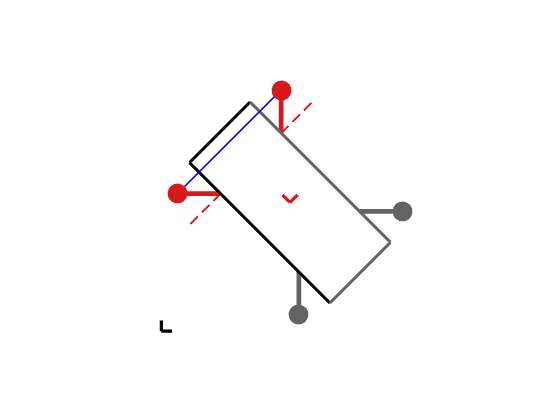

% States and body location (test)
a1 = pi/4; a2 = -pi/4;
a3 = pi/4; a4 = -pi/4;
xx = 3; yy = 3; th = pi/4;

% Plotting heursitics
limX = [-1, 7]; limY = [-1, 7];
scaleDraw = max([diff(limX),diff(limY)])/23.5;
lW = 1.2/scaleDraw; lW_r = 0.5/scaleDraw; lW_b = 0.8/scaleDraw;
lW_kq = 0.4/scaleDraw; lW_qf = 0.8/scaleDraw;
frame_scale = 0.25; % length of the frame arrows compared to body length
lW_O = 0.8; alp_O = 0.2; lW_traj = 2.4/scaleDraw;
circS = 75/scaleDraw;
col = (1/255)*[215,25,28;
            96,0,220;
            44,123,182;
            77,175,74;
            255,127,0;
            231,41,138];

% Figure-------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
figure()
% x and y lines at the origin
% xline(0,'k','LineWidth',lW_O,'Alpha',alp_O); % x and y lines
% yline(0,'k','LineWidth',lW_O,'Alpha',alp_O);
axis equal square; hold on; set(gca, 'visible', 'off');

% legs
plot(pltkin.legbase1_leg1_x(1, 1, a1, xx, yy, th), pltkin.legbase1_leg1_y(1, 1, a1, xx, yy, th), 'Color', col(1,:), 'LineWidth', lW);
plot(pltkin.legbase2_leg2_x(1, 1, a2, xx, yy, th), pltkin.legbase2_leg2_y(1, 1, a2, xx, yy, th), 'Color', col(1,:), 'LineWidth', lW);
plot(pltkin.legbase3_leg3_x(1, 1, a3, xx, yy, th), pltkin.legbase3_leg3_y(1, 1, a3, xx, yy, th), 'Color', [99,99,99]/255, 'LineWidth', lW);
plot(pltkin.legbase4_leg4_x(1, 1, a4, xx, yy, th), pltkin.legbase4_leg4_y(1, 1, a4, xx, yy, th), 'Color', [99,99,99]/255, 'LineWidth', lW);
% leg mean positions
plot(pltkin.legbase1_leg1_x(1, 1, 0, xx, yy, th), pltkin.legbase1_leg1_y(1, 1, 0, xx, yy, th), 'LineStyle', '--', 'Color', col(1,:), 'LineWidth', lW_r);
plot(pltkin.legbase2_leg2_x(1, 1, 0, xx, yy, th), pltkin.legbase2_leg2_y(1, 1, 0, xx, yy, th), 'LineStyle', '--', 'Color', col(1,:), 'LineWidth', lW_r);
% plot(pltkin.legbase3_leg3_x(1, 1, 0, xx, yy, th), pltkin.legbase3_leg3_y(1, 1, 0, xx, yy, th), 'LineStyle', '--', 'Color', [99,99,99]/255, 'LineWidth', lW_r);
% plot(pltkin.legbase4_leg4_x(1, 1, 0, xx, yy, th), pltkin.legbase4_leg4_y(1, 1, 0, xx, yy, th), 'LineStyle', '--', 'Color', [99,99,99]/255, 'LineWidth', lW_r);

% body
plot(pltkin.topright2topleft_x(1, xx, yy, th), pltkin.topright2topleft_y(1, xx, yy, th), 'Color', 'k', 'LineWidth', lW_b);
plot(pltkin.topleft2botleft_x(1, xx, yy, th), pltkin.topleft2botleft_y(1, xx, yy, th), 'Color', 'k', 'LineWidth', lW_b);
plot(pltkin.botleft2botright_x(1, xx, yy, th), pltkin.botleft2botright_y(1, xx, yy, th), 'Color', [99,99,99]/255, 'LineWidth', lW_b);
plot(pltkin.botright2topright_x(1, xx, yy, th), pltkin.botright2topright_y(1, xx, yy, th), 'Color', [99,99,99]/255, 'LineWidth', lW_b);

% k-vector, connecting leg tips (S_12 test)
quiver(sum([1,0].*pltkin.k_leg1_leg2_x(1,1,a1,a2,xx,yy,th)), sum([1,0].*pltkin.k_leg1_leg2_y(1,1,a1,a2,xx,yy,th)),...
    pltkin.k_leg1_leg2_u(1,1,a1,a2,xx,yy,th), pltkin.k_leg1_leg2_v(1,1,a1,a2,xx,yy,th),...
    'Color', 'b', 'LineWidth', lW_kq, 'AutoScale', 'off', 'ShowArrowHead', 'off'); % this needs to match with the color of the iso-contours

% Scatter circs to the active leg tips
scatter(pltkin.leg1_x(1, 1, a1, xx, yy, th), pltkin.leg1_y(1, 1, a1, xx, yy, th), circS, col(1,:), 'filled');
scatter(pltkin.leg2_x(1, 1, a2, xx, yy, th), pltkin.leg2_y(1, 1, a2, xx, yy, th), circS, col(1,:), 'filled');
scatter(pltkin.leg3_x(1, 1, a1, xx, yy, th), pltkin.leg3_y(1, 1, a1, xx, yy, th), circS, [99,99,99]/255, 'filled');
scatter(pltkin.leg4_x(1, 1, a2, xx, yy, th), pltkin.leg4_y(1, 1, a2, xx, yy, th), circS, [99,99,99]/255, 'filled');

% % plot the connecting line between the active leg bases with dashes
% plot(pltkin.legbase1_legbase2_x(1,1,a1,a2,xx,yy,th), pltkin.legbase1_legbase2_y(1,1,a1,a2,xx,yy,th), '--', 'Color', col(1,:), 'LineWidth', lW_r);

% % position vector to the body frame from the global origin
% quiver(0, 0, pltkin.body_x(xx, yy, th), pltkin.body_y(xx, yy, th), 'LineStyle', '-', 'LineWidth', lW_q, 'Color', 'k', 'AutoScale', 'off');

% body frame 'g_b' and global origin 'g_e'
quiver(pltkin.body_x(xx, yy, th), pltkin.body_y(xx, yy, th), frame_scale*sum([1,0]*pltkin.bodyf_x(xx, yy, th)),...
    frame_scale*sum([0,1]*pltkin.bodyf_x(xx, yy, th)),...
    'LineWidth', lW_qf, 'Color', col(1,:), 'AutoScale', 'off', 'ShowArrowHead', 'off'); % show the current contact state through color
quiver(pltkin.body_x(xx, yy, th), pltkin.body_y(xx, yy, th), frame_scale*sum([1,0]*pltkin.bodyf_y(xx, yy, th)), frame_scale*sum([0,1]*pltkin.bodyf_y(xx, yy, th)),...
    'LineWidth', lW_qf, 'Color', col(1,:), 'AutoScale', 'off', 'ShowArrowHead', 'off');
quiver(0, 0, frame_scale*1, 0, 'LineWidth', lW_qf, 'Color', 'k', 'AutoScale', 'off', 'ShowArrowHead', 'off'); % x-axis
quiver(0, 0, 0, frame_scale*1, 'LineWidth', lW_qf, 'Color', 'k', 'AutoScale', 'off', 'ShowArrowHead', 'off'); % y-axis

% Set the limits
axis([limX, limY]);

### Connection vector fields, Generalized curl, and Stratified disps of the level-2 submanifolds

Given the columns needed {'connection','exterior','lie','curl','disp'} (any combination of these), "plotcase1kinematics" function will plot the necessary figure encompassing the requested kinematics for the $S_{12}$ contact state.

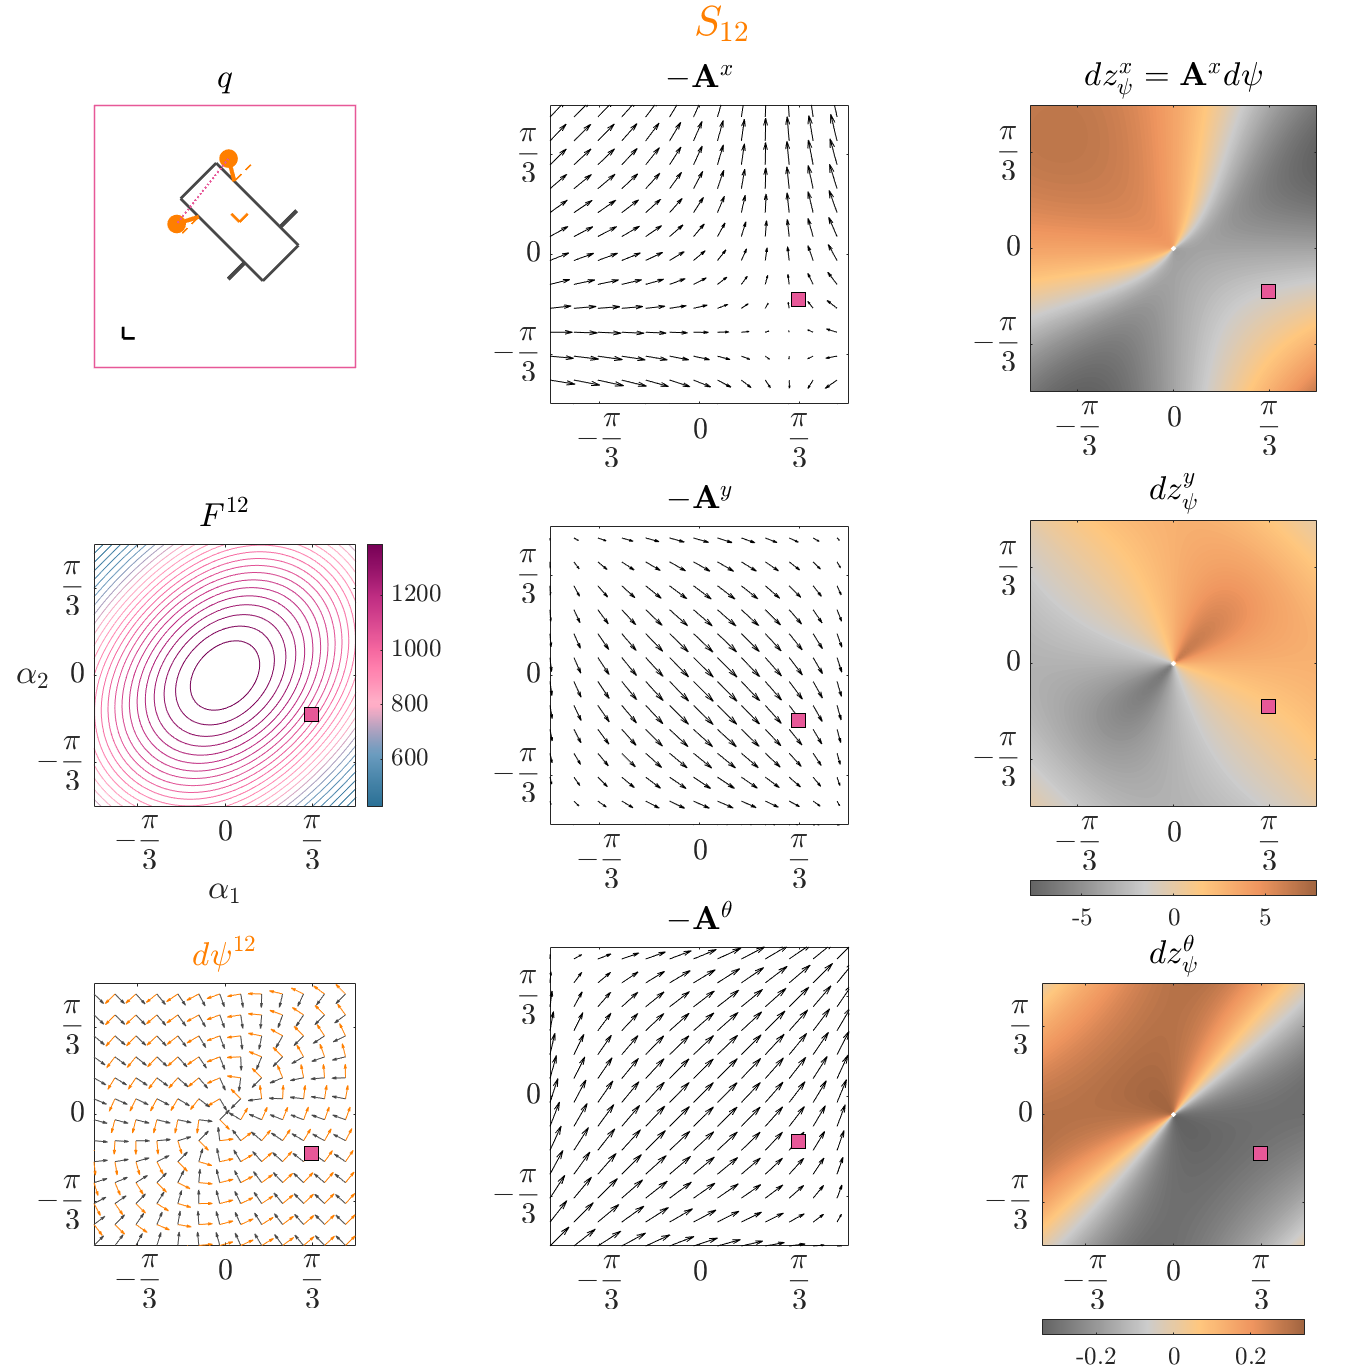

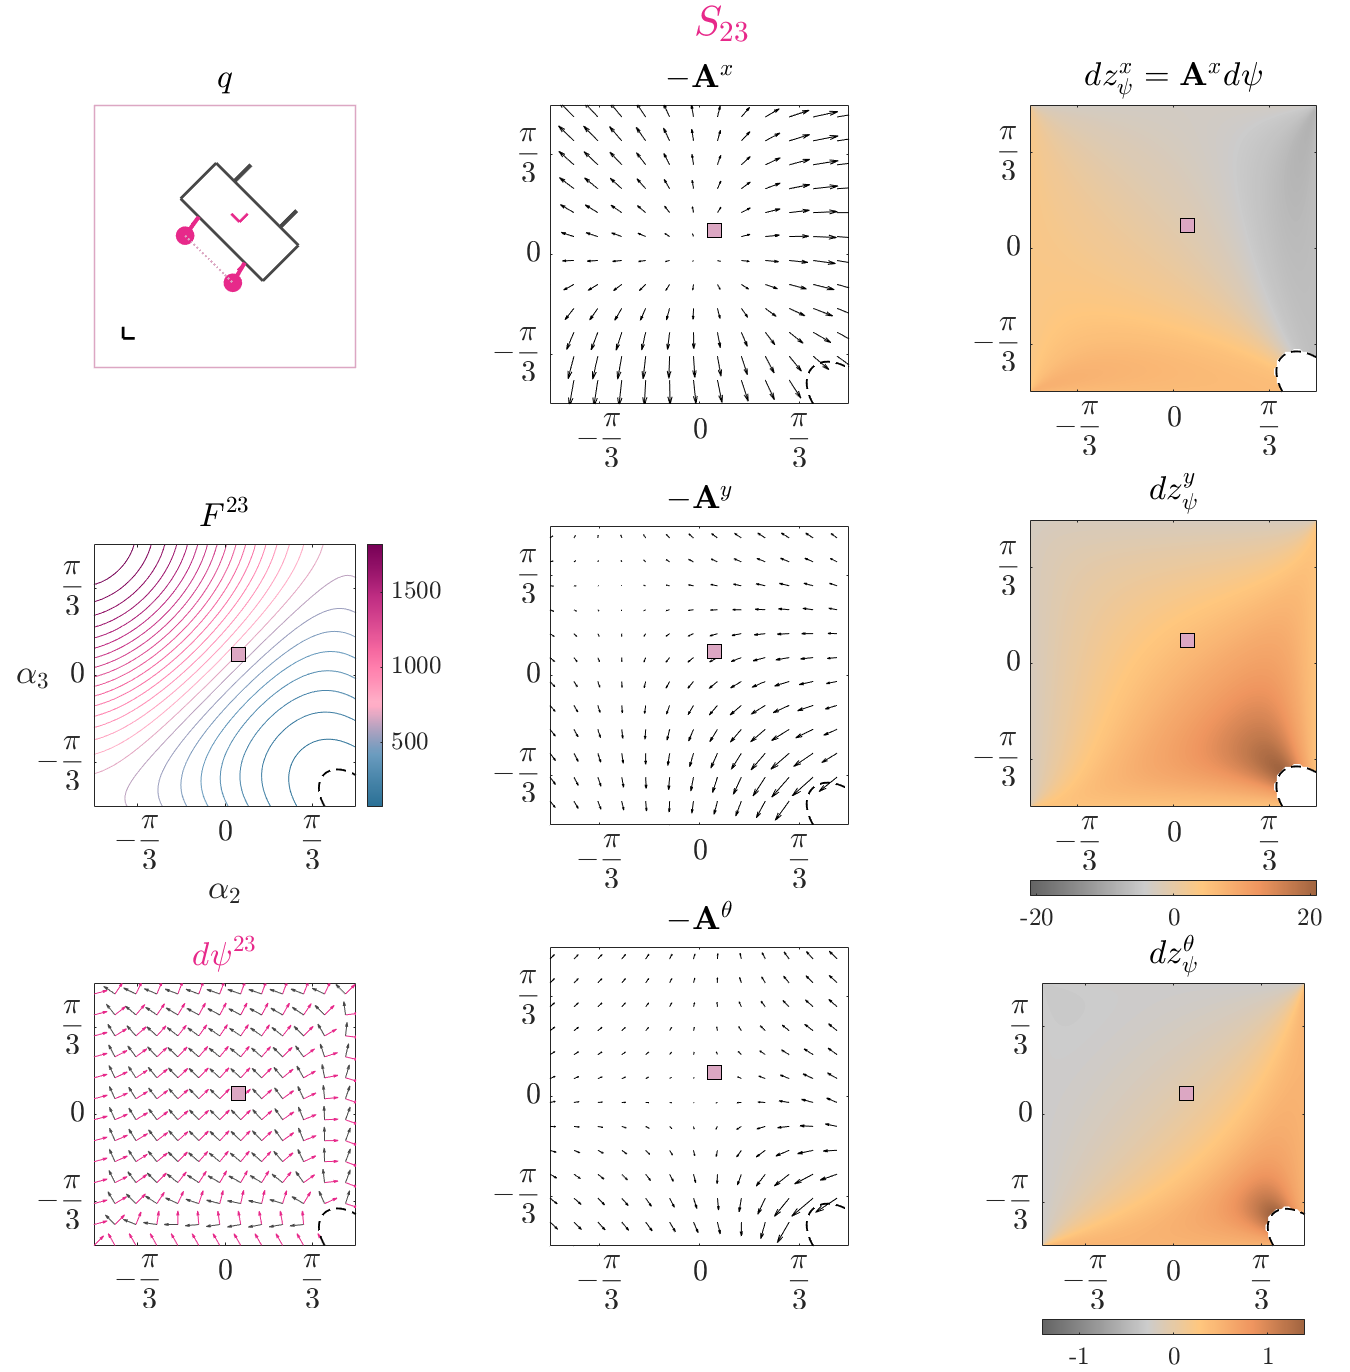

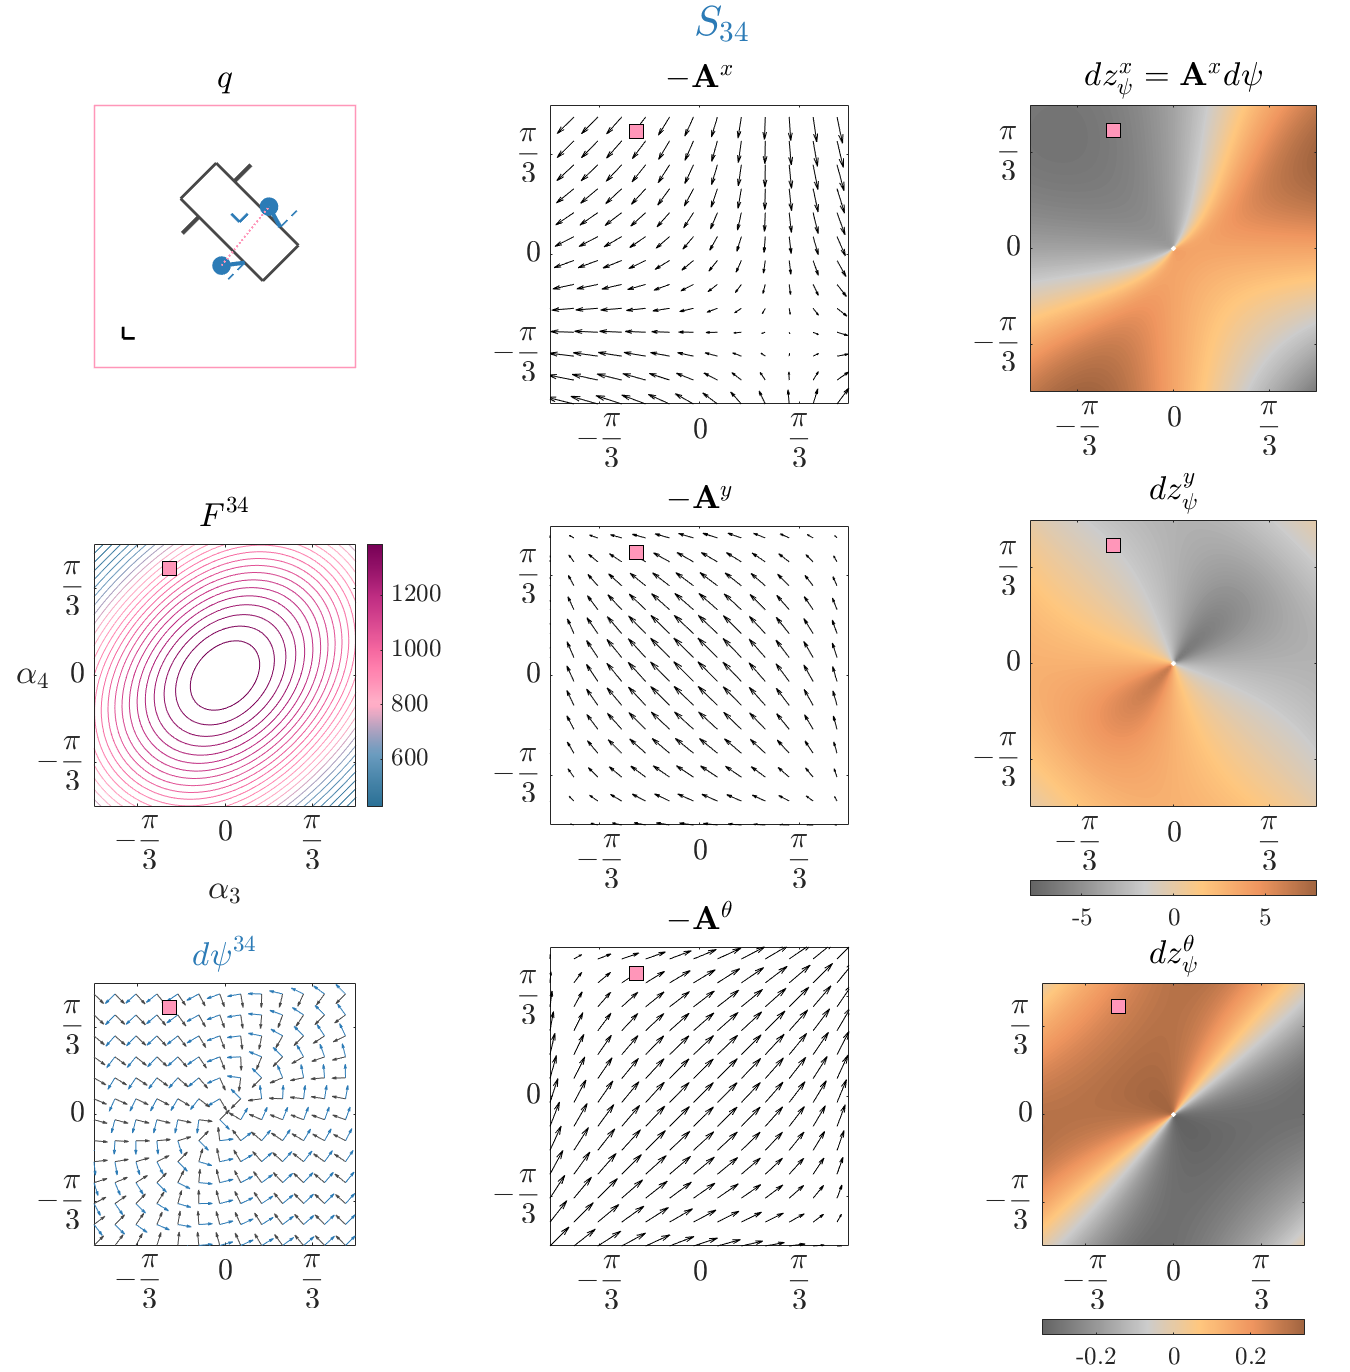

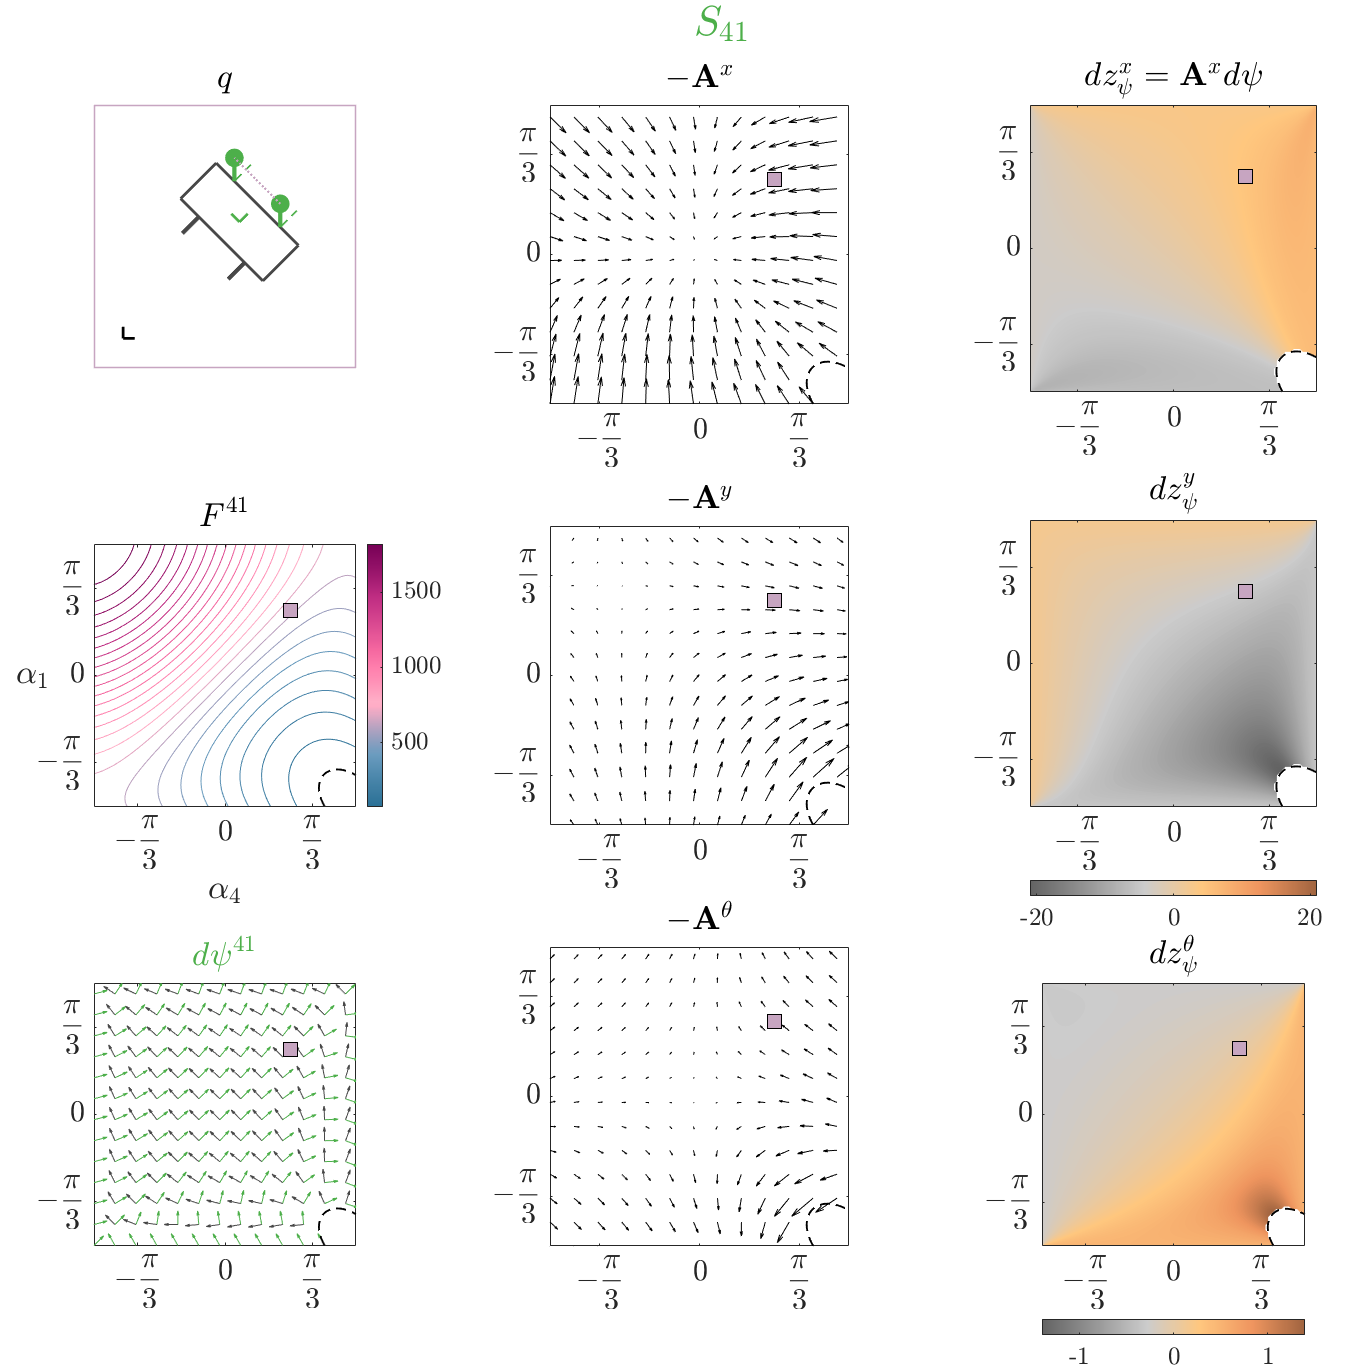

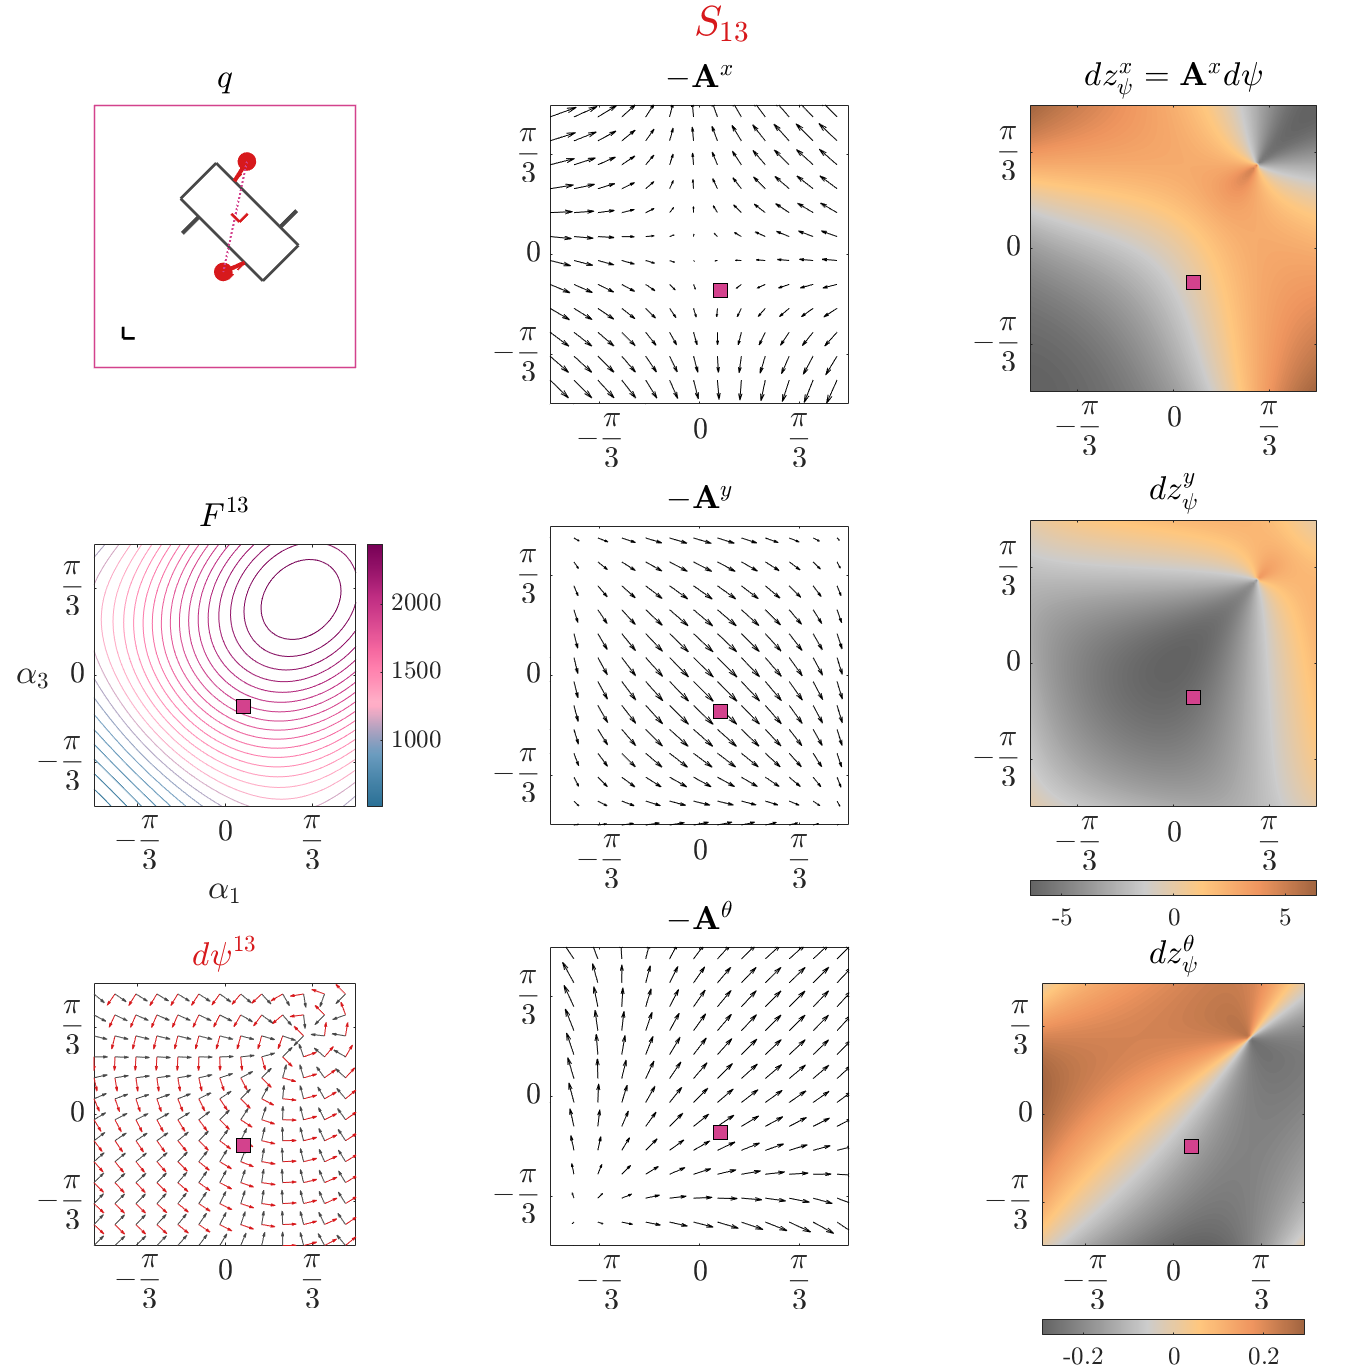

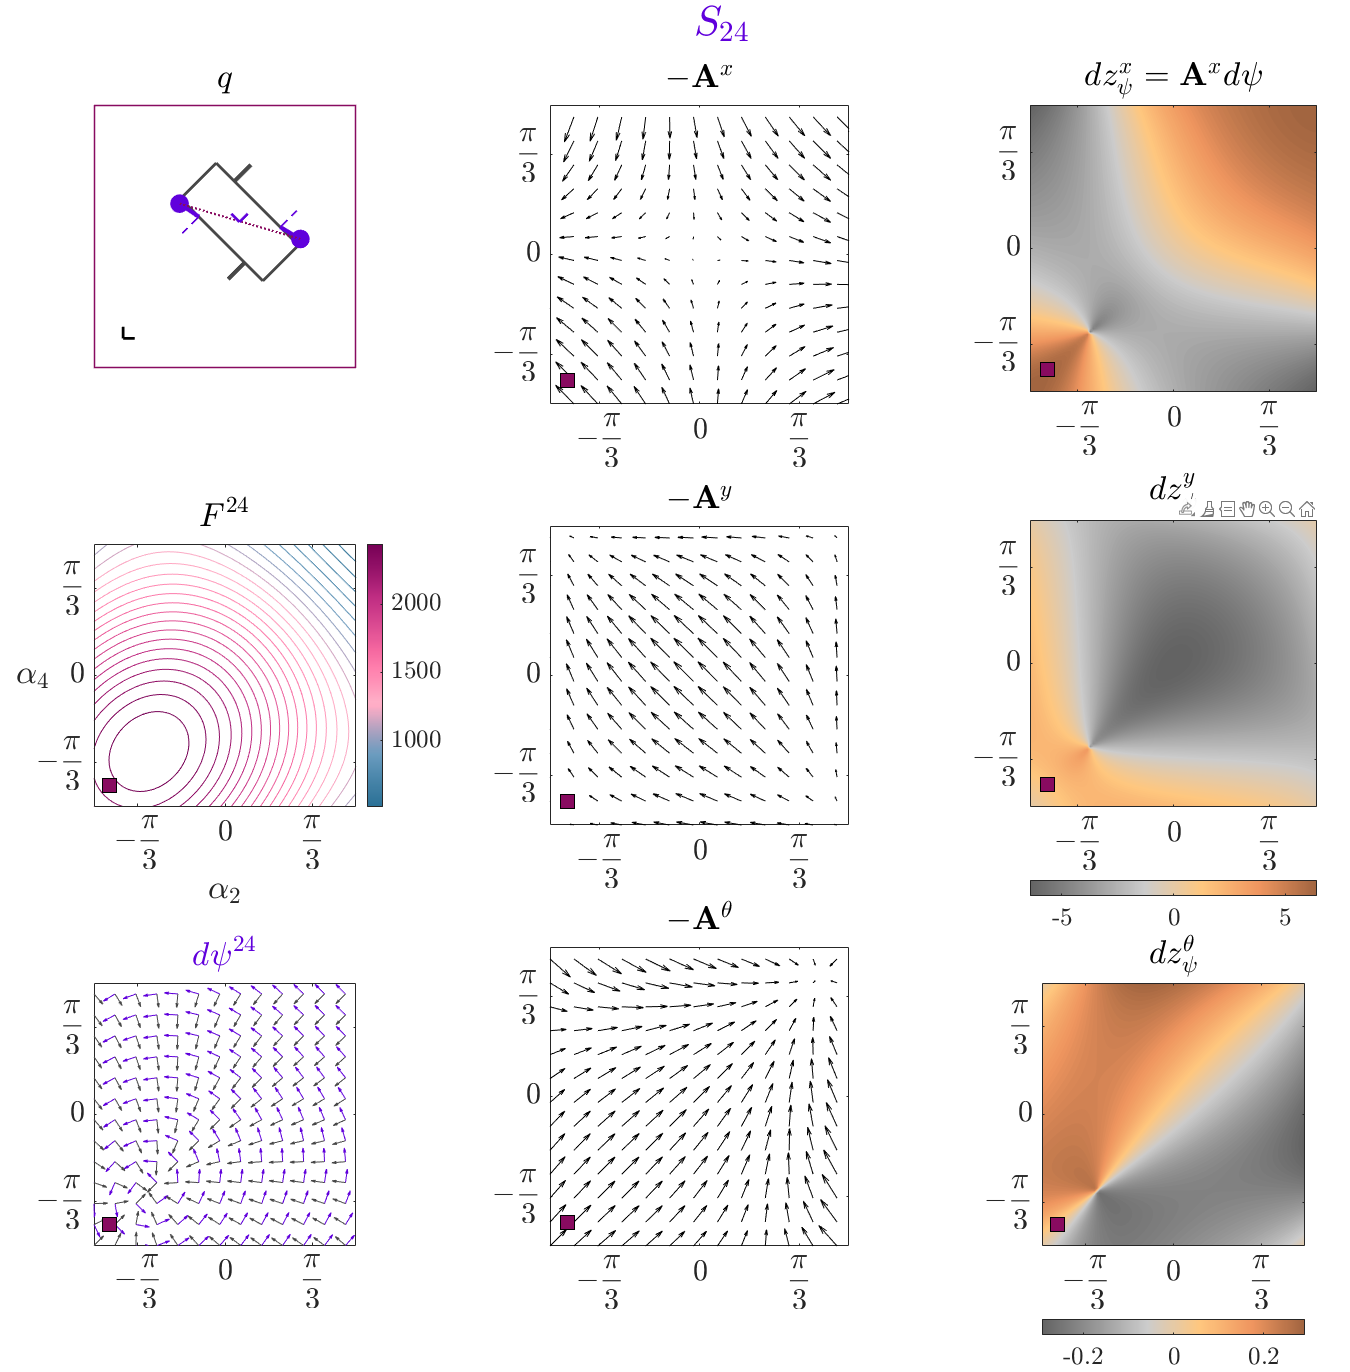

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%   USER INPUTS   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Add folders to the path:
addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
% check if we are doing the HAMR case -- 2023/05/03 working on the HAMR case right now
hamr6_F = true;
if hamr6_F
    datname = 'Data\HAMR6_SE2_kinematics.mat';
    datmpname = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
else
    datname = 'Data\case_1_kinematics.mat';
    datmpname = 'Data\case_1_kinematics_motionplan.mat';
end
% Load the data from the previous section:
load(datname);

% choose your active contact states, the kinematic fields to display, and
% robot configuration to display ------------------------------------------
cs = [1, 2;
      2, 3;
      3, 4;
      4, 1;
      1, 3;
      2, 4];

% robot parameters --------------------------------------------------------
ank = pi/2; % hip angle limit (use half of this as the latex tick labels)
if hamr6_F
    aa = hamr_a; ll = hamr_l; % leg and body length parameters
else
    aa = 1; ll = 1; % leg and body length parameters
end

% shape-space discretization ----------------------------------------------
dnum = 101; % 1001 is used in the previous sections
            % use multiples of 10 with a +1 at the end

% plot parameters ---------------------------------------------------------
skipV = 7.5; % PERCENTAGE OF THE DISCRETIZATION POINTS TO SKIP for connection
sV = 7.5; % for gait constraint
skipV = round((skipV/100)*2*floor(dnum/2)); sV = round((sV/100)*2*floor(dnum/2));
cLvl = 25; % number of contour levels -- ksq
cfLvl = 100; % number of filled contour levels
fontscale = 1.25; % use this scale number to change the font in the plot
                  % preferred range [0.5 2.5]; start iterating at 1.25
fA = 1.00; % transparency of heat maps
           % some vals to try: 0.50 % 1.00 % 0.40 % 0.75

% user input structures ---------------------------------------------------
kin_info = []; plot_info = [];

% pack all the information ------------------------------------------------
kin_info.flag = hamr6_F;
kin_info.ank = ank; kin_info.aa = aa; kin_info.ll = ll; kin_info.bl = bl;
kin_info.lvl2_cs = cs;
kin_info.h_b__1b = h_b__1b; kin_info.h_b__2b = h_b__2b; kin_info.h_b__3b = h_b__3b; kin_info.h_b__4b = h_b__4b;
kin_info.h_12b__1b = h_12b__1b; kin_info.h_12b__2b = h_12b__2b; kin_info.h_34b__3b = h_34b__3b; kin_info.h_34b__4b = h_34b__4b;
kin_info.h_23b__2b = h_23b__2b; kin_info.h_23b__3b = h_23b__3b; kin_info.h_41b__4b = h_41b__4b; kin_info.h_41b__1b = h_41b__1b;
kin_info.h_13b__1b = h_13b__1b; kin_info.h_13b__3b = h_13b__3b; kin_info.h_24b__2b = h_24b__2b; kin_info.h_24b__4b = h_24b__4b;

plot_info.dnum = dnum; plot_info.skipV = skipV; plot_info.sV = sV;
plot_info.cLvl = cLvl; plot_info.cfLvl = cfLvl; 
plot_info.fontscale = fontscale; plot_info.fA = fA;

% Initialize the return containers
p_info = cell(1,size(cs,1)); p_kin = p_info; kinfunc = p_info;

% Iterate over each contact state:
for i = 1:size(cs,1)
% for i = 1
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    kin_info.cs = [cs(i,1) cs(i,2)];
%     fields = {'-A','-dA','[A_1,A_2]','D(-A)','dz'}; % case 1 deafult (don't change the order)
    fields = {'-A','dz'}; % case 2-- of most interest for motion 
                          % planning
    % Define for which fields you need the configuration plotted
    % configs = [ones(3,1),ones(3,1),ones(3,1),ones(3,1),ones(3,1)]; % case 1 default
    configs = [ones(3,1),ones(3,1)]; % case 2
    kin_info.fields = fields; kin_info.configs = configs; % pack
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [p_info{i}, p_kin{i}, kinfunc{i}] = qlevel2noslip(kin_info, plot_info); % call the function
%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     saveas(gcf, p_info{i}.savetitle_txt, 'pdf'); % save the figure as pdf
end

% Save the resuls in a mat file
save(datmpname, 'p_info', 'p_kin', 'kinfunc'); % , '-append'

With the above results, we can move towards motion planning in each submanifold.

### Integrating gait constraints to sample gaits in a contact state

The motion planning problem is handled case by case, below.

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

#### 
$$S_{12}$$


Let's first find a way to overlay the gait constraint vector field, $d\phi$ on top of the infinitesimal disps for ease of access.

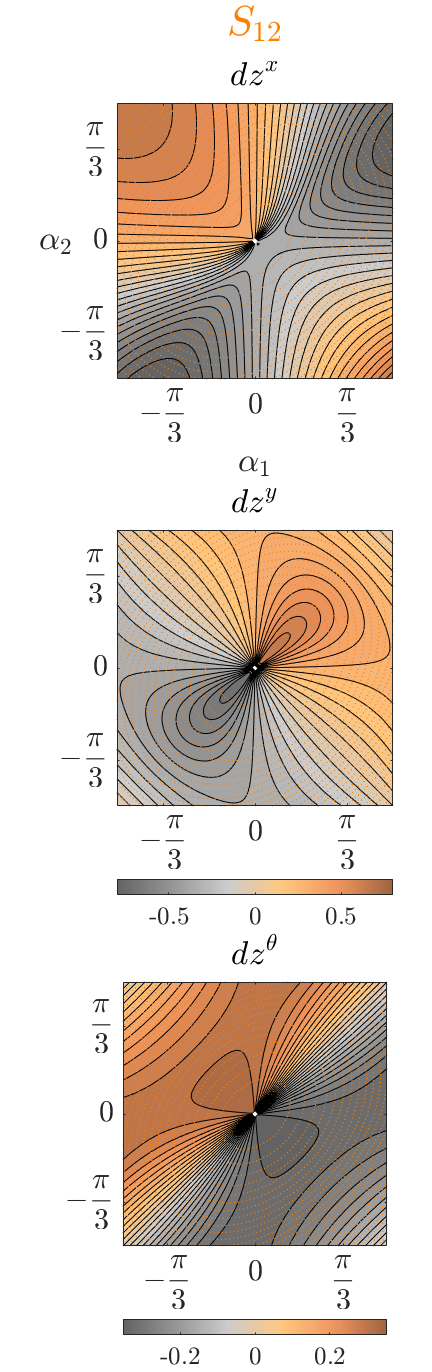

% choose the first submanifold
si = 1;
% use the kinematics computed earlier to plot the infinitesimal disps-- modify some data before based on requirement
p_info{si}.cLvl = 25; % default is 25
p_info{si}.cfLvl = 25; % default is 100
% p_info{si}.fA = 1.0; % default is 1
p_info{si}.lW_s = 2.0; % path linewidth for animations
p_info{si}.colP = [0,0,0]/255; % gait constraint contours props to aid path planning
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
qlevel2noslip_mp(S_data);

% obtain the vector fields you want to integrate over
[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);

Let's try to design a sub gait with a focus of x-displacement.

% initialize the arguments
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;

ptf = pi/6*[1, 0] + pi/6*[0, 1];                        % point of interest ( @(-30,-30) degrees ) to integrate about
% ptf = -deg2rad(21)*[1, 0] + deg2rad(21)*[0, 1];         % point of interest ( @(-21,+21) degrees ) to integrate about
t = [1, 1];                                             % integration times in the backward and forward direction from "stpt"
dc = 0.2;                                               % percentage of time spent in the deadband
dnum = 201; S_data{3}.dnum = dnum;                      % number of points needed on the active path
dirn = 1;                                               % direction to integrate along: +1 is along +dphi and -1 is along -dphi. Everything inbetween will scale the path range.

% compute the color of the path based on gait constraints
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' );  c(c > 1) = 1;

% create a Path2 object-- get the props and call the static methods
path12 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
Path2.compute_trajectory( path12, symstr, dnum );

Now, we are ready to plot out the paths generated.

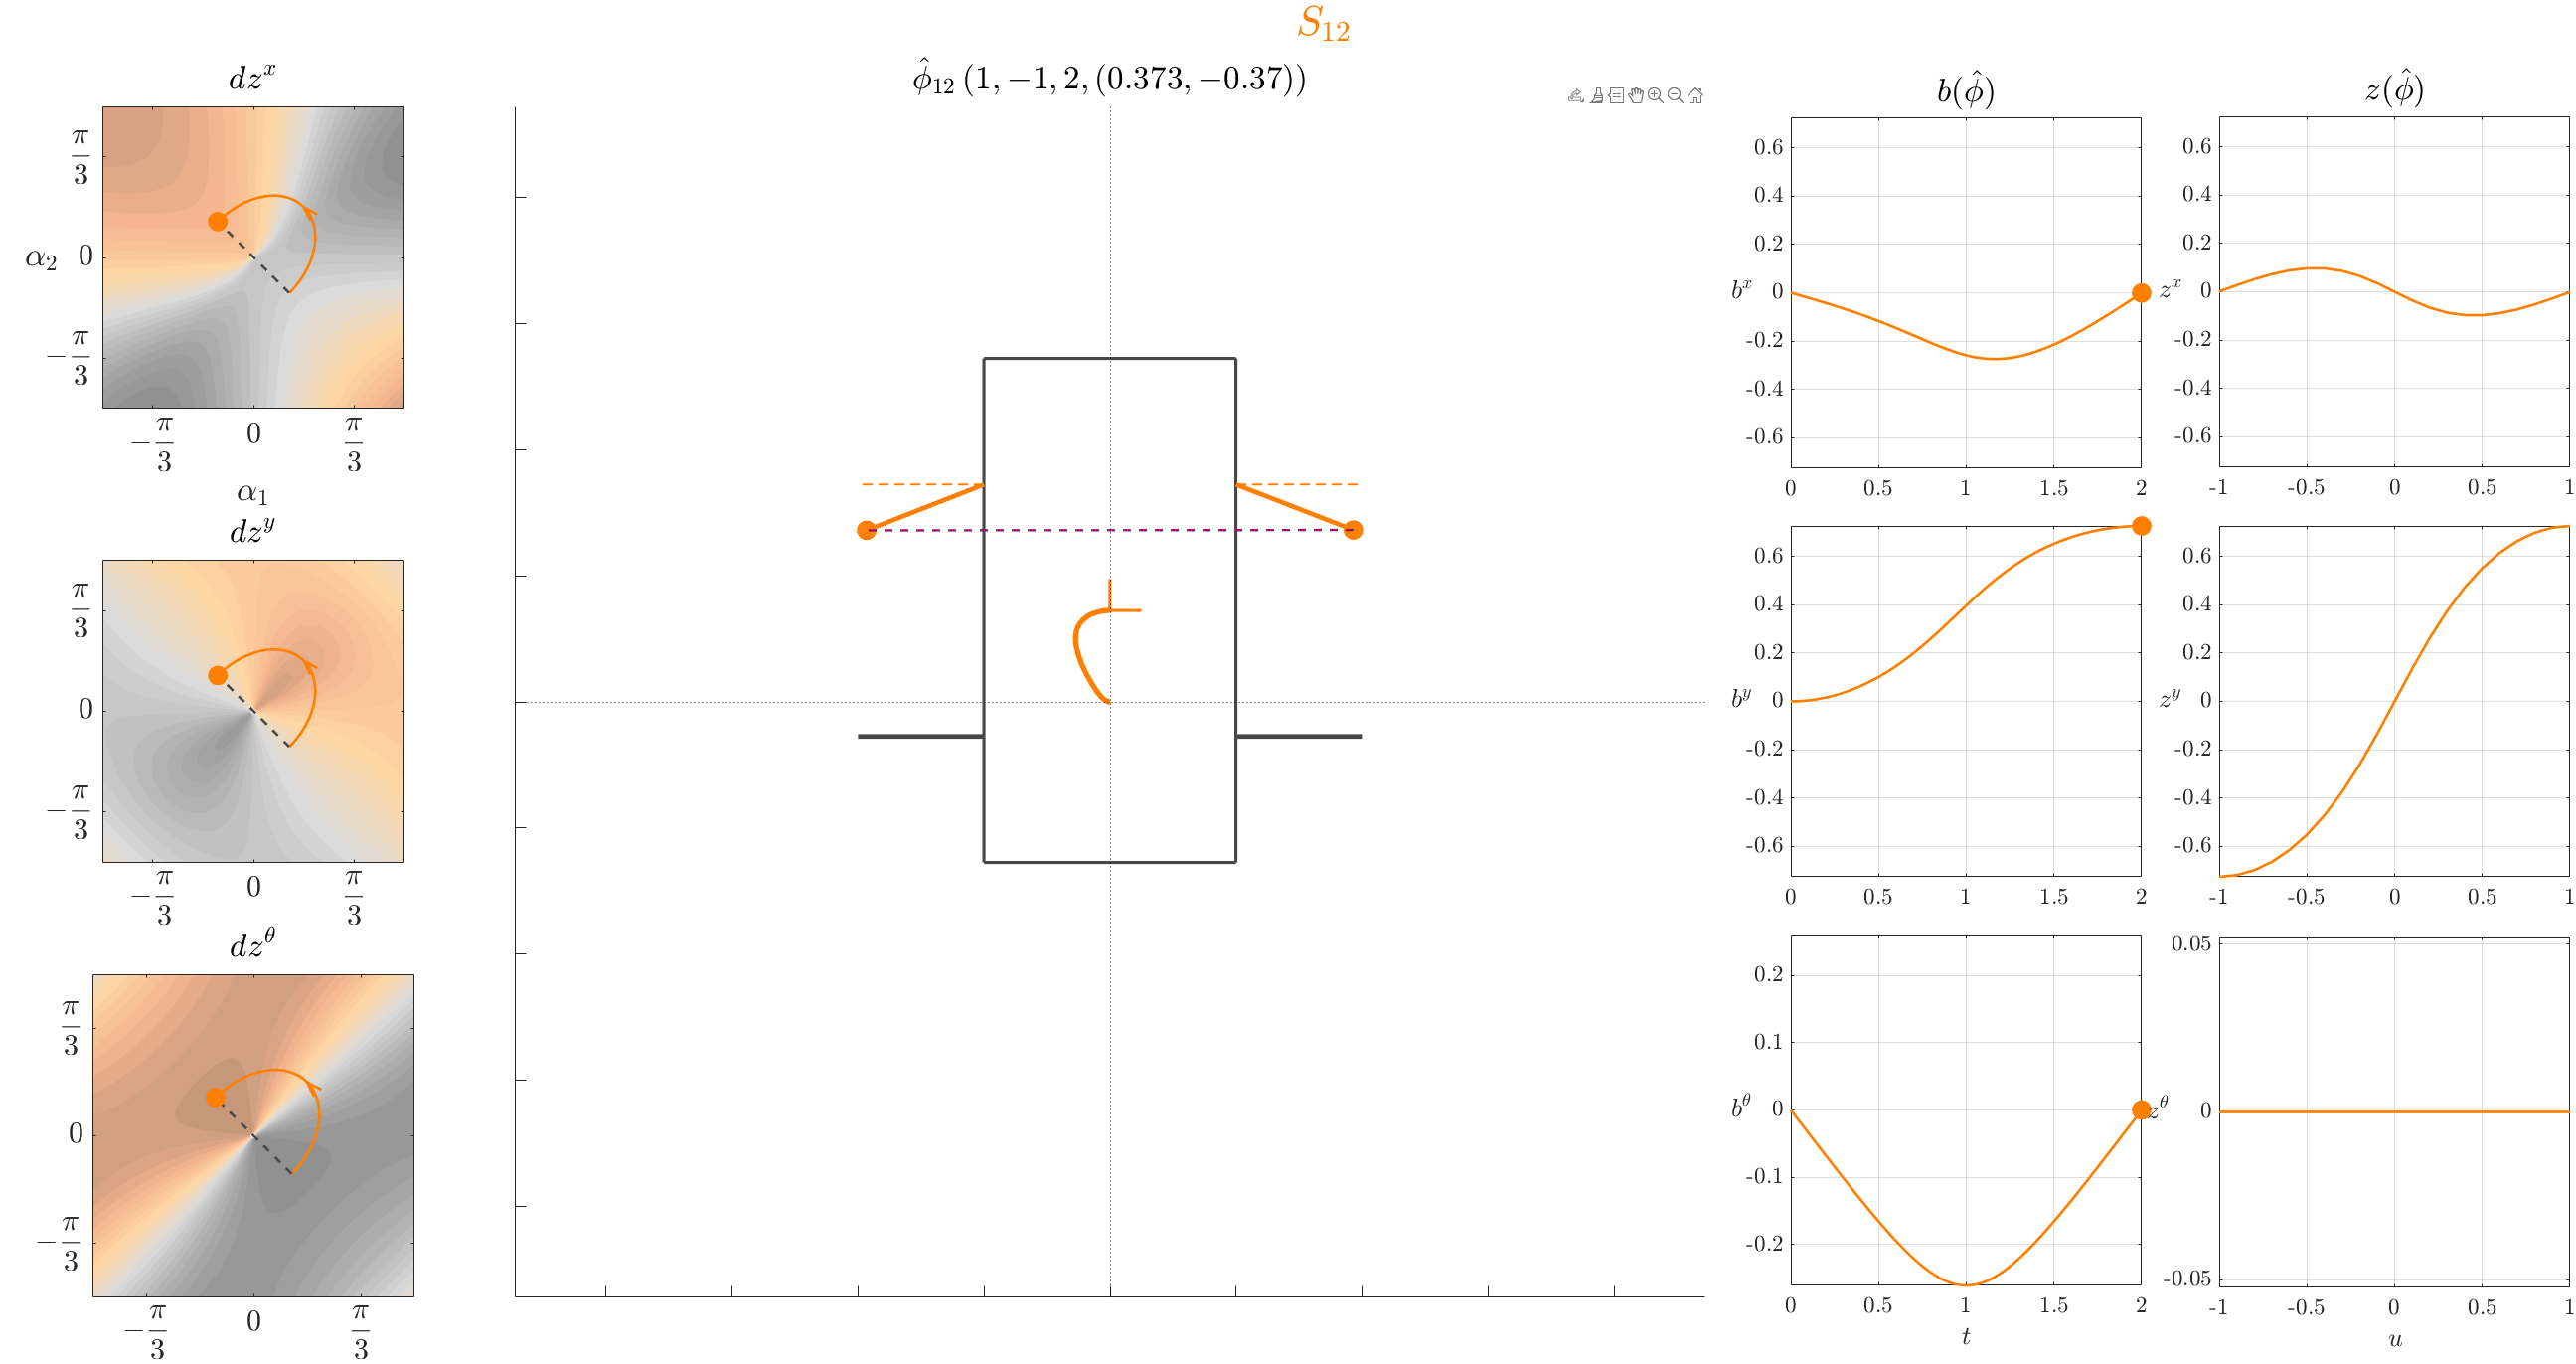

path = path12;
S_data{4} = pltkin;
S_data{5} = path;    % add the 'pltkin' strct and 'Path2' object for plotting the animation
S_data{1}.fA = 0.70;     % make it 30% transparent to see the curvers better
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S12_data_y = S_data; save('Data\case_1_S12_y.mat', 'S12_data_y');
% S12_data_xtheta = S_data; save('Data\case_1_S12_xtheta.mat', 'S12_data_xtheta');
qlevel2noslip_mp(S_data); % run the animation and plot the computed open_trajectories

exportsetupdlg;
clear S_data;

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

#### 
$$S_{34}$$


Let's create a complementary gait in the $S_{34}$ submanifold to obtain a net displacement in the y-direction.

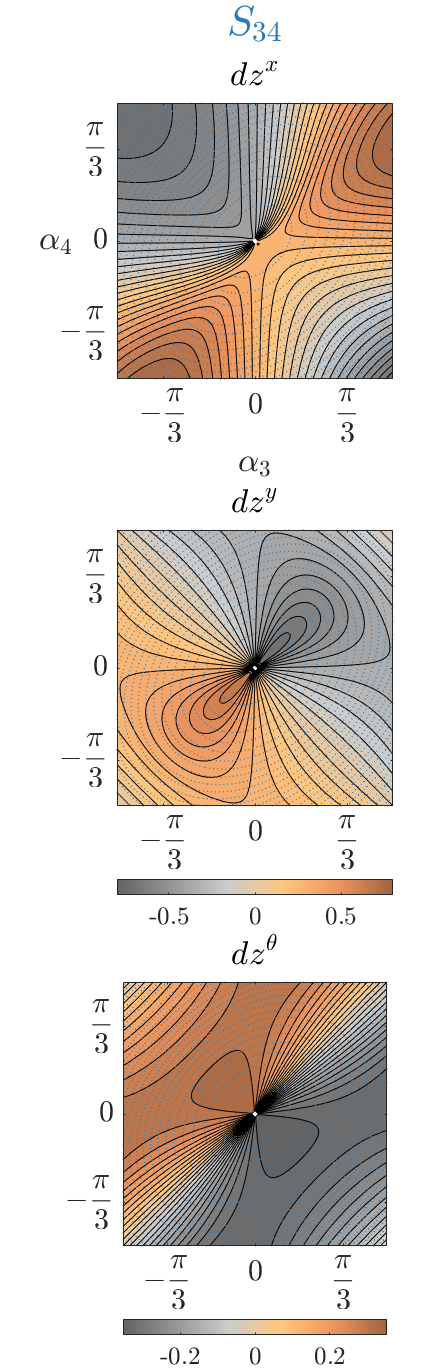

% contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
si = 3; % S34
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
qlevel2noslip_mp(S_data);

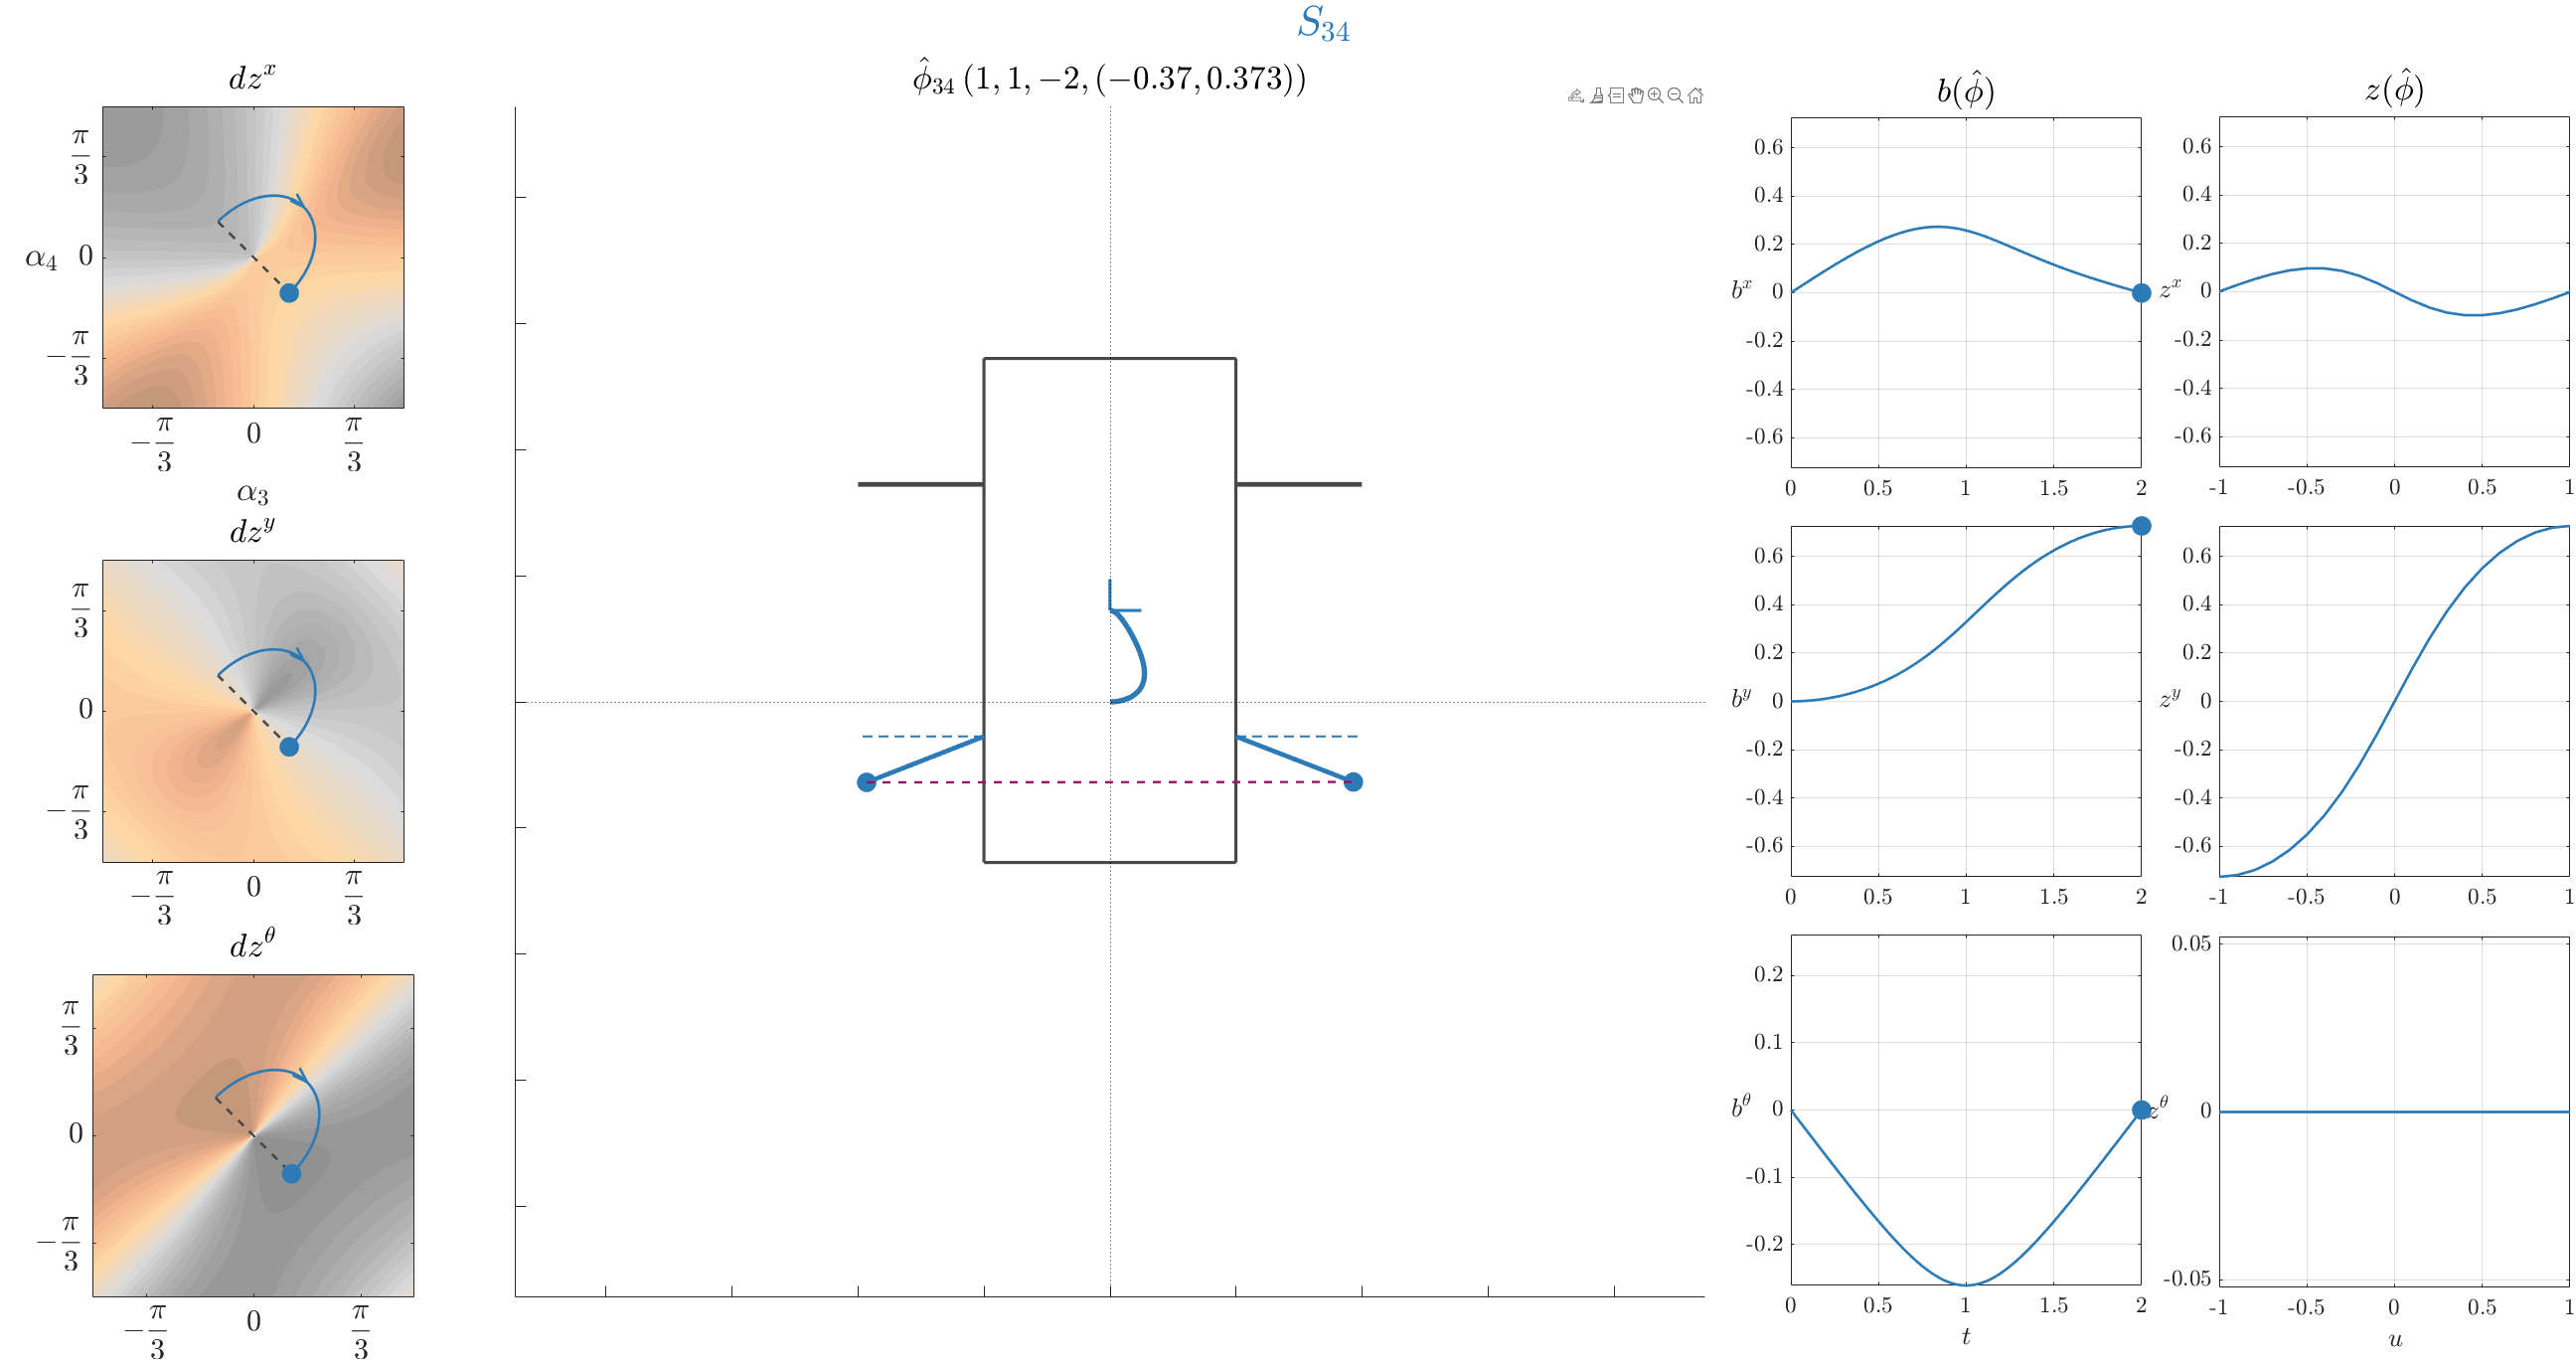

[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
ptf = pi/6*[+1, 0] + pi/6*[0, +1]; % pof = (+30,+30) degrees
% ptf = -1*deg2rad(21)*[+1, 0] + +1*deg2rad(21)*[0, +1]; % pof = (-21,+21) degrees
t = [1, 1];
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum; 
dirn = -1; % +1 %-1
% dirn = 1;
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' );  c(c > 1) = 1;
path34 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
Path2.compute_trajectory( path34, symstr, dnum );
path = path34;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S34_data_y = S_data; save('Data\case_1_S34_y.mat', 'S34_data_y');
% S34_data_mxtheta = S_data; save('Data\case_1_S34_mxtheta.mat', 'S34_data_mxtheta');
qlevel2noslip_mp(S_data); 

exportsetupdlg;
clear S_data;

Now, we can combine these paths to generate a 2-beat gait for the quadrupedal robot.

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');
load('Data\case_1_S12_y.mat'); load('Data\case_1_S12_xtheta.mat'); load('Data\case_1_S34_mxtheta.mat'); load('Data\case_1_S34_y.mat');

#### 
$$S_{12} \leftrightarrow S_{34}$$


In this simple 2-beat gait, we start with the first path we generated in $S_{12}$ and then switch to the path in $S_{34}$. Recall that each of these paths have a scaling factor associated with scales the paths about a certain point of interest. Let's call them $u_\psi$ for the path's they are associated with. Then the 2-beat gait can be defined as the overlap between the shape-space slices in each of these paths. We need to complete these paths in a special certain way so that their active regions don't overlap, then we can express the 2-beat gait and the corresponding net displacement as shown below,


$$\phi_{i j} = \psi_i \, u_i + \psi_j \, u_j, \,\, u \in (-1, 1) \cap \mathbb{R} \\
z^{\phi_{i j}} = z^{\psi_i \, u_i} + z^{\psi_j \, u_j}$$


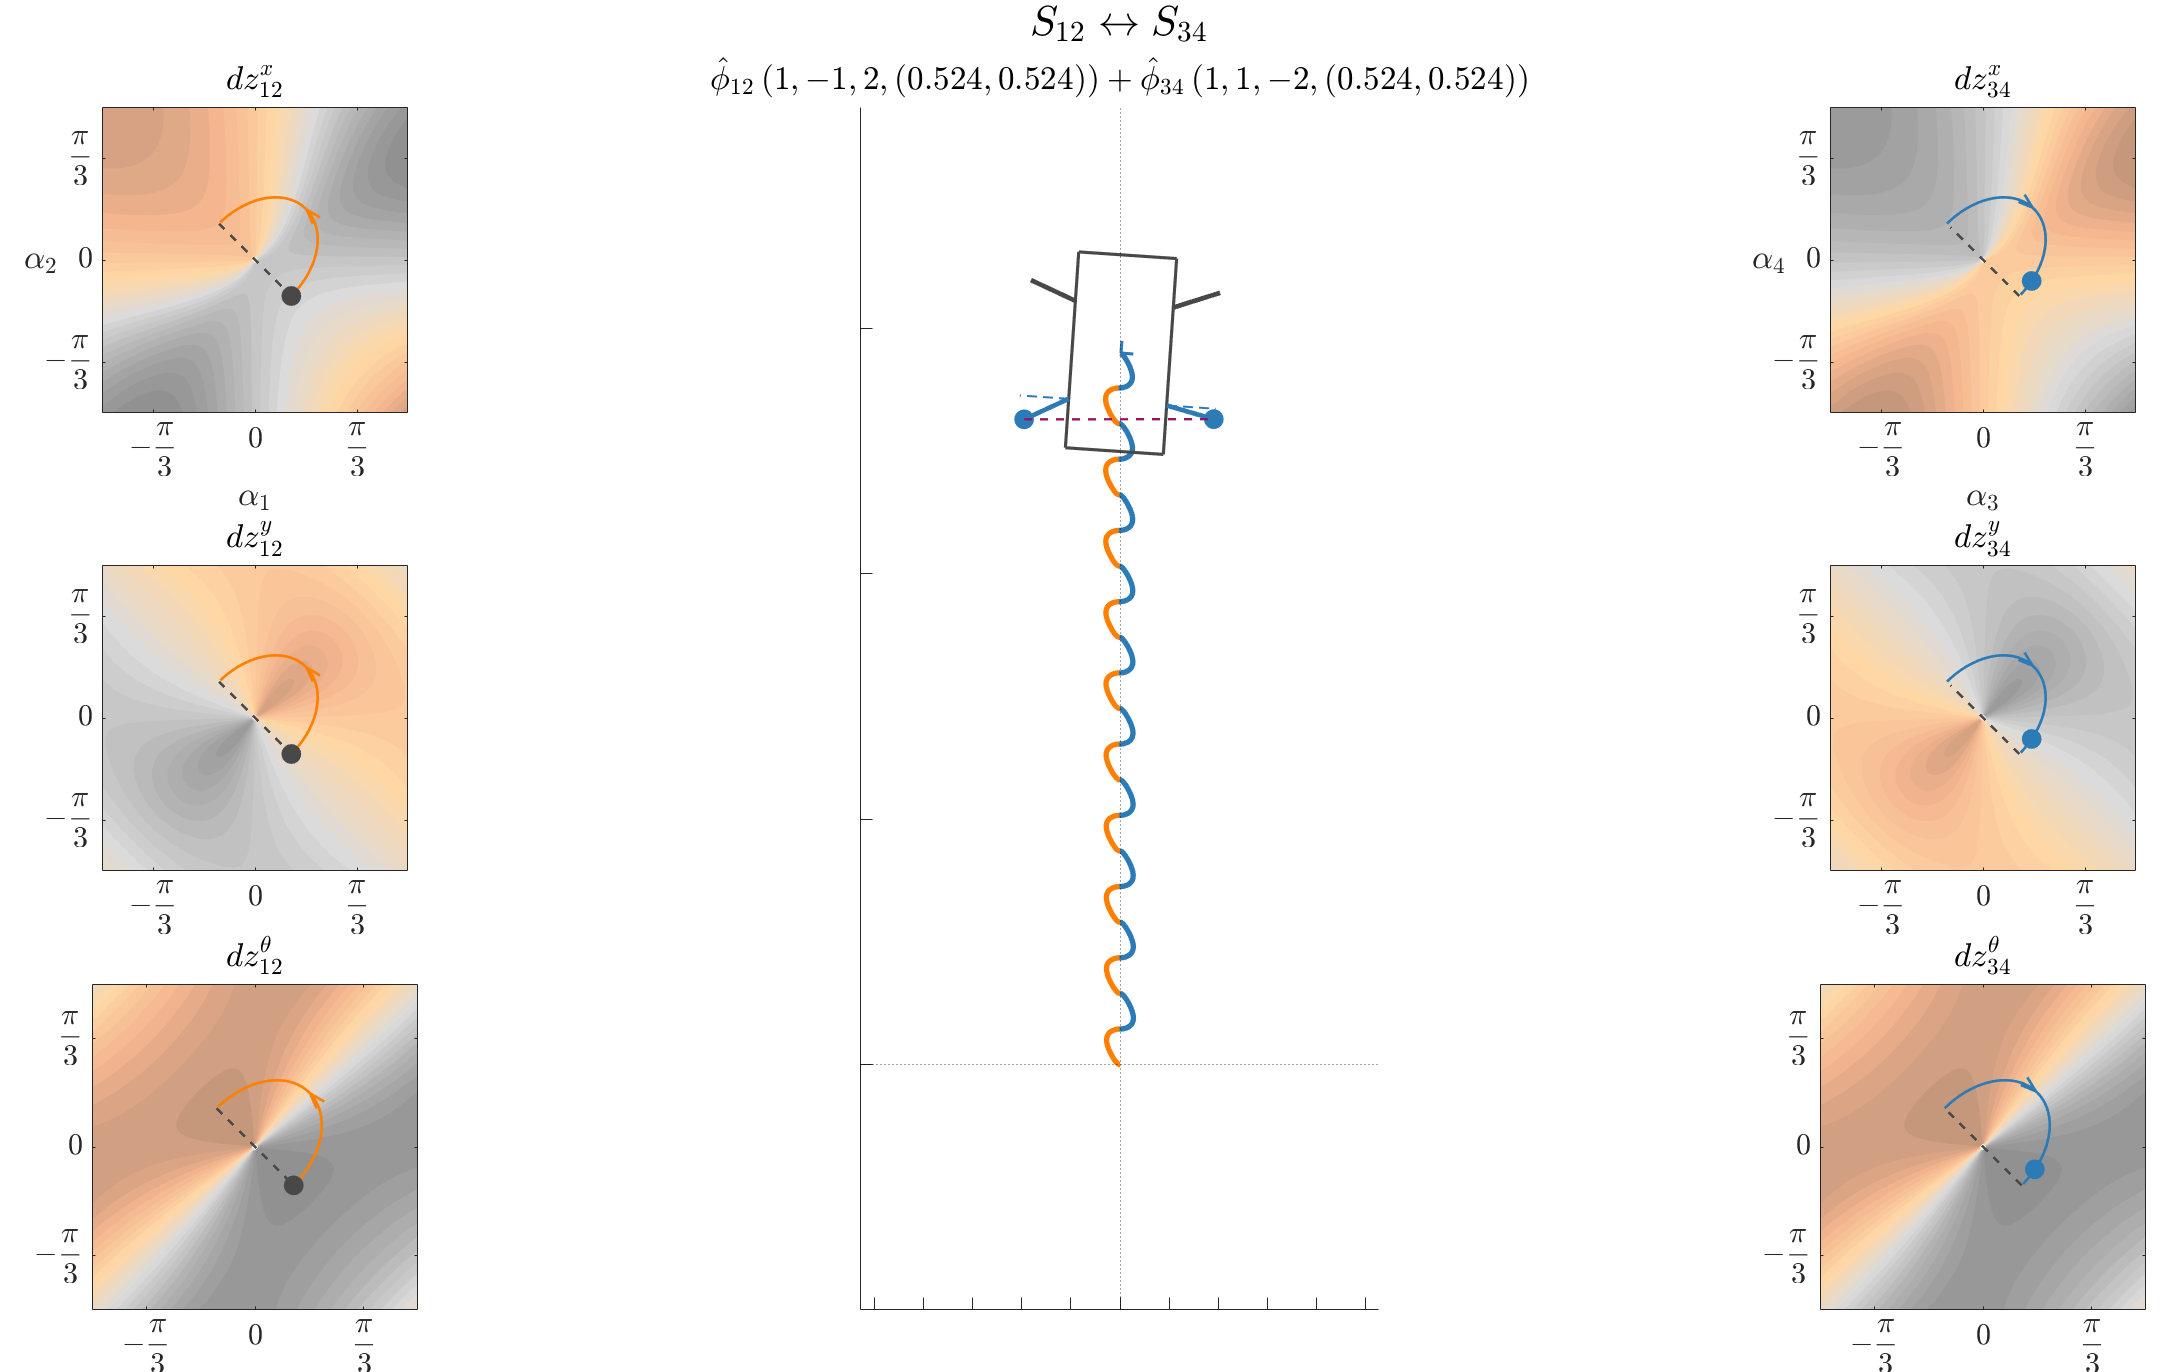

% % % % %           |
% % % % %    -,+    |   +,+
% % % % % ----------------------
% % % % %    -,-    |   +,-
% % % % %           |
% % % % % shown above is how the gaits can be combined since ui and uj can range between (-1, 1), we are looking at the unit square for generating a bound-like gait.
% % % % % to plot the video, let's give an input to each path in 10s of percentages-- for instance, -10% for path 1 and 50% for path 2.
dataij = [];
dataij.vidF = true; % true % false
dataij.u = [+100, +100]/100; % y-path
% dataij.u = [+100, -100]/100; % x-path
% dataij.gaitC_num = 1; % just for theta path
% dataij.u = [+100, +100]/100;
S12_data_y{1}.fA = 0.7;
S34_data_y{1}.fA = 0.7;
dataij = qlevel2noslip_mp(S12_data_y, S34_data_y, dataij);

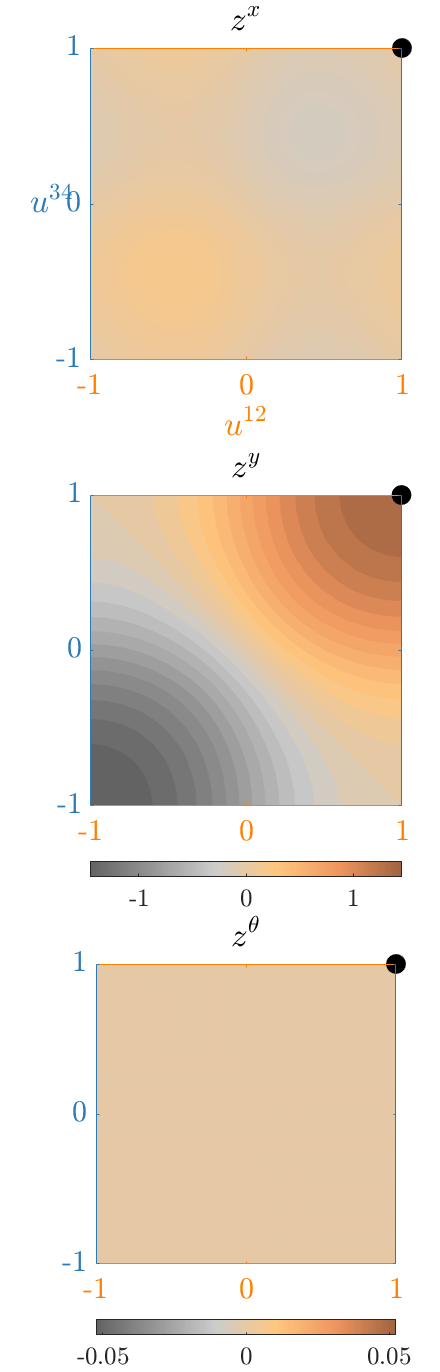

plotnetdispofnoslip2bgaits(S12_data_y, S34_data_y, dataij);

save('Data\case_1_S12toS34_y_gait.mat','dataij');
% S12_data_xtheta{1}.fA = 0.7;
% S34_data_mxtheta{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S12_data_xtheta, S34_data_mxtheta, dataij);
% plotnetdispofnoslip2bgaits(S12_data_xtheta, S34_data_mxtheta, dataij);
% save('Data\case_1_S12toS34_xy_gait.mat','dataij');
% S12_data_xtheta{1}.fA = 0.7;
% S34_data_mxtheta{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S12_data_xtheta, S34_data_mxtheta, dataij);
% plotnetdispofnoslip2bgaits(S12_data_xtheta, S34_data_mxtheta, dataij);
% save('Data\case_1_S12toS34_theta_gait.mat','dataij');